%计算考虑化学作用后的三锁体系
clear all
syms e r o l k;

y1=[];
y2=[];
Plock=[];
Vlock=[];
Vopen=[];

%笼腔长度等于多少个sigma(o)
for l=3:0.1:7
    for k = 0:0.1:2
%计算锁死所占成分
        fun1 = @(x2,x1) P(x2).^(2*k).*P(x1-x2).^(2*k).*P(l-x1).^(k);
        x2max= @(x1) x1;
        V_lock = 3*integral2(fun1,0,l,0,x2max);

%计算开放所占成分
        fun2 = @(x2,x1) P(l-x1).^(k).*P(x1).^k.*P(x1-x2).^k.*P(l-x2).^k.*P(x2).^k;
        x2max= @(x1) x1;
        V_open = 2*integral2(fun2,0,l,0,x2max);
        P_lock = V_lock/(V_lock + V_open); %计算锁死所占比例
        Plock=[Plock,P_lock]
    end
end

Plock = 0.6000

Plock =     0.6000    0.9917


Plock =     0.6000    0.9917    0.9963


Plock =     0.6000    0.9917    0.9963    0.9980


Plock =     0.6000    0.9917    0.9963    0.9980    0.9989


Plock =     0.6000    0.9917    0.9963    0.9980    0.9989    0.9993


Plock =     0.6000    0.9917    0.9963    0.9980    0.9989    0.9993    0.9996


Plock =     0.6000    0.9917    0.9963    0.9980    0.9989    0.9993    0.9996    0.9999


Plock =     0.6000    0.9917    0.9963    0.9980    0.9989    0.9993    0.9996    0.9999    0.9999


Plock =     0.6000    0.9917    0.9963    0.9980    0.9989    0.9993    0.9996    0.9999    0.9999    1.0000


Plock =     0.6000    0.9917    0.9963    0.9980    0.9989    0.9993    0.9996    0.9999    0.9999    1.0000    1.0000


Plock =     0.6000    0.9917    0.9963    0.9980    0.9989    0.9993    0.9996    0.9999    0.9999    1.0000    1.0000    1.0000


Plock =     0.6000    0.9917    0.9963    0.9980    0.9989    0.9993    0.9996    0.9999    0.9999    1.0000    1.0000    1.0000    1.0000


Plock =     0.6000    0.9917    0.9963    0.9980    0.9989    0.9993    0.9996    0.9999    0.9999    1.0000    1.0000    1.0000    1.0000    1.0000


Plock =     0.6000    0.9917    0.9963    0.9980    0.9989    0.9993    0.9996    0.9999    0.9999    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000


Plock =     0.6000    0.9917    0.9963    0.9980    0.9989    0.9993    0.9996    0.9999    0.9999    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000


Plock =     0.6000    0.9917    0.9963    0.9980    0.9989    0.9993    0.9996    0.9999    0.9999    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000


Plock =     0.6000    0.9917    0.9963    0.9980    0.9989    0.9993    0.9996    0.9999    0.9999    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000


Plock =     0.6000    0.9917    0.9963    0.9980    0.9989    0.9993    0.9996    0.9999    0.9999    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000


Plock =     0.6000    0.9917    0.9963    0.9980    0.9989    0.9993    0.9996    0.9999    0.9999    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000


Plock =     0.6000    0.9917    0.9963    0.9980    0.9989    0.9993    0.9996    0.9999    0.9999    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000


Plock =     0.6000    0.9917    0.9963    0.9980    0.9989    0.9993    0.9996    0.9999    0.9999    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    0.6000


Plock =     0.6000    0.9917    0.9963    0.9980    0.9989    0.9993    0.9996    0.9999    0.9999    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    0.6000    0.9835


Plock =     0.6000    0.9917    0.9963    0.9980    0.9989    0.9993    0.9996    0.9999    0.9999    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    0.6000    0.9835    0.9888


Plock =     0.6000    0.9917    0.9963    0.9980    0.9989    0.9993    0.9996    0.9999    0.9999    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    0.6000    0.9835    0.9888    0.9912


Plock =     0.6000    0.9917    0.9963    0.9980    0.9989    0.9993    0.9996    0.9999    0.9999    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    0.6000    0.9835    0.9888    0.9912    0.9927


Plock =     0.6000    0.9917    0.9963    0.9980    0.9989    0.9993    0.9996    0.9999    0.9999    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    0.6000    0.9835    0.9888    0.9912    0.9927    0.9940


Plock =     0.6000    0.9917    0.9963    0.9980    0.9989    0.9993    0.9996    0.9999    0.9999    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    0.6000    0.9835    0.9888    0.9912    0.9927    0.9940    0.9951


Plock =     0.6000    0.9917    0.9963    0.9980    0.9989    0.9993    0.9996    0.9999    0.9999    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    0.6000    0.9835    0.9888    0.9912    0.9927    0.9940    0.9951    0.9960


Plock =     0.6000    0.9917    0.9963    0.9980    0.9989    0.9993    0.9996    0.9999    0.9999    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    0.6000    0.9835    0.9888    0.9912    0.9927    0.9940    0.9951    0.9960    0.9969


Plock =     0.6000    0.9917    0.9963    0.9980    0.9989    0.9993    0.9996    0.9999    0.9999    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    0.6000    0.9835    0.9888    0.9912    0.9927    0.9940    0.9951    0.9960    0.9969    0.9976


Plock =     0.6000    0.9917    0.9963    0.9980    0.9989    0.9993    0.9996    0.9999    0.9999    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    0.6000    0.9835    0.9888    0.9912    0.9927    0.9940    0.9951    0.9960    0.9969    0.9976    0.9982


Plock =     0.6000    0.9917    0.9963    0.9980    0.9989    0.9993    0.9996    0.9999    0.9999    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    0.6000    0.9835    0.9888    0.9912    0.9927    0.9940    0.9951    0.9960    0.9969    0.9976    0.9982    0.9993


Plock =     0.6000    0.9917    0.9963    0.9980    0.9989    0.9993    0.9996    0.9999    0.9999    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    0.6000    0.9835    0.9888    0.9912    0.9927    0.9940    0.9951    0.9960    0.9969    0.9976    0.9982    0.9993    0.9995


Plock =     0.6000    0.9917    0.9963    0.9980    0.9989    0.9993    0.9996    0.9999    0.9999    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    0.6000    0.9835    0.9888    0.9912    0.9927    0.9940    0.9951    0.9960    0.9969    0.9976    0.9982    0.9993    0.9995    0.9997


Plock =     0.6000    0.9917    0.9963    0.9980    0.9989    0.9993    0.9996    0.9999    0.9999    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    0.6000    0.9835    0.9888    0.9912    0.9927    0.9940    0.9951    0.9960    0.9969    0.9976    0.9982    0.9993    0.9995    0.9997    0.9998


Plock =     0.6000    0.9917    0.9963    0.9980    0.9989    0.9993    0.9996    0.9999    0.9999    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    0.6000    0.9835    0.9888    0.9912    0.9927    0.9940    0.9951    0.9960    0.9969    0.9976    0.9982    0.9993    0.9995    0.9997    0.9998    0.9998


Plock =     0.6000    0.9917    0.9963    0.9980    0.9989    0.9993    0.9996    0.9999    0.9999    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    0.6000    0.9835    0.9888    0.9912    0.9927    0.9940    0.9951    0.9960    0.9969    0.9976    0.9982    0.9993    0.9995    0.9997    0.9998    0.9998    0.9999


Plock =     0.6000    0.9917    0.9963    0.9980    0.9989    0.9993    0.9996    0.9999    0.9999    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    0.6000    0.9835    0.9888    0.9912    0.9927    0.9940    0.9951    0.9960    0.9969    0.9976    0.9982    0.9993    0.9995    0.9997    0.9998    0.9998    0.9999    0.9999


Plock =     0.6000    0.9917    0.9963    0.9980    0.9989    0.9993    0.9996    0.9999    0.9999    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    0.6000    0.9835    0.9888    0.9912    0.9927    0.9940    0.9951    0.9960    0.9969    0.9976    0.9982    0.9993    0.9995    0.9997    0.9998    0.9998    0.9999    0.9999    0.9999


Plock =     0.6000    0.9917    0.9963    0.9980    0.9989    0.9993    0.9996    0.9999    0.9999    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    0.6000    0.9835    0.9888    0.9912    0.9927    0.9940    0.9951    0.9960    0.9969    0.9976    0.9982    0.9993    0.9995    0.9997    0.9998    0.9998    0.9999    0.9999    0.9999    1.0000


Plock =     0.6000    0.9917    0.9963    0.9980    0.9989    0.9993    0.9996    0.9999    0.9999    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    0.6000    0.9835    0.9888    0.9912    0.9927    0.9940    0.9951    0.9960    0.9969    0.9976    0.9982    0.9993    0.9995    0.9997    0.9998    0.9998    0.9999    0.9999    0.9999    1.0000    1.0000


Plock =     0.6000    0.9917    0.9963    0.9980    0.9989    0.9993    0.9996    0.9999    0.9999    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    0.6000    0.9835    0.9888    0.9912    0.9927    0.9940    0.9951    0.9960    0.9969    0.9976    0.9982    0.9993    0.9995    0.9997    0.9998    0.9998    0.9999    0.9999    0.9999    1.0000    1.0000    0.6000


Plock =     0.6000    0.9917    0.9963    0.9980    0.9989    0.9993    0.9996    0.9999    0.9999    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    0.6000    0.9835    0.9888    0.9912    0.9927    0.9940    0.9951    0.9960    0.9969    0.9976    0.9982    0.9993    0.9995    0.9997    0.9998    0.9998    0.9999    0.9999    0.9999    1.0000    1.0000    0.6000    0.9732


Plock =     0.6000    0.9917    0.9963    0.9980    0.9989    0.9993    0.9996    0.9999    0.9999    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    0.6000    0.9835    0.9888    0.9912    0.9927    0.9940    0.9951    0.9960    0.9969    0.9976    0.9982    0.9993    0.9995    0.9997    0.9998    0.9998    0.9999    0.9999    0.9999    1.0000    1.0000    0.6000    0.9732    0.9775


Plock =     0.6000    0.9917    0.9963    0.9980    0.9989    0.9993    0.9996    0.9999    0.9999    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    0.6000    0.9835    0.9888    0.9912    0.9927    0.9940    0.9951    0.9960    0.9969    0.9976    0.9982    0.9993    0.9995    0.9997    0.9998    0.9998    0.9999    0.9999    0.9999    1.0000    1.0000    0.6000    0.9732    0.9775    0.9783


Plock =     0.6000    0.9917    0.9963    0.9980    0.9989    0.9993    0.9996    0.9999    0.9999    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    0.6000    0.9835    0.9888    0.9912    0.9927    0.9940    0.9951    0.9960    0.9969    0.9976    0.9982    0.9993    0.9995    0.9997    0.9998    0.9998    0.9999    0.9999    0.9999    1.0000    1.0000    0.6000    0.9732    0.9775    0.9783    0.9783


Plock =     0.6000    0.9917    0.9963    0.9980    0.9989    0.9993    0.9996    0.9999    0.9999    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    0.6000    0.9835    0.9888    0.9912    0.9927    0.9940    0.9951    0.9960    0.9969    0.9976    0.9982    0.9993    0.9995    0.9997    0.9998    0.9998    0.9999    0.9999    0.9999    1.0000    1.0000    0.6000    0.9732    0.9775    0.9783    0.9783    0.9783


Plock =     0.6000    0.9917    0.9963    0.9980    0.9989    0.9993    0.9996    0.9999    0.9999    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    0.6000    0.9835    0.9888    0.9912    0.9927    0.9940    0.9951    0.9960    0.9969    0.9976    0.9982    0.9993    0.9995    0.9997    0.9998    0.9998    0.9999    0.9999    0.9999    1.0000    1.0000    0.6000    0.9732    0.9775    0.9783    0.9783    0.9783    0.9786


Plock =     0.6000    0.9917    0.9963    0.9980    0.9989    0.9993    0.9996    0.9999    0.9999    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    0.6000    0.9835    0.9888    0.9912    0.9927    0.9940    0.9951    0.9960    0.9969    0.9976    0.9982    0.9993    0.9995    0.9997    0.9998    0.9998    0.9999    0.9999    0.9999    1.0000    1.0000    0.6000    0.9732    0.9775    0.9783    0.9783    0.9783    0.9786    0.9794


Plock =     0.6000    0.9917    0.9963    0.9980    0.9989    0.9993    0.9996    0.9999    0.9999    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    0.6000    0.9835    0.9888    0.9912    0.9927    0.9940    0.9951    0.9960    0.9969    0.9976    0.9982    0.9993    0.9995    0.9997    0.9998    0.9998    0.9999    0.9999    0.9999    1.0000    1.0000    0.6000    0.9732    0.9775    0.9783    0.9783    0.9783    0.9786    0.9794


Plock = 1×52
    0.6000    0.9917    0.9963    0.9980    0.9989    0.9993    0.9996    0.9999    0.9999    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    0.6000    0.9835    0.9888    0.9912    0.9927    0.9940    0.9951    0.9960    0.9969


Plock = 1×53
    0.6000    0.9917    0.9963    0.9980    0.9989    0.9993    0.9996    0.9999    0.9999    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    0.6000    0.9835    0.9888    0.9912    0.9927    0.9940    0.9951    0.9960    0.9969


Plock = 1×54
    0.6000    0.9917    0.9963    0.9980    0.9989    0.9993    0.9996    0.9999    0.9999    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    0.6000    0.9835    0.9888    0.9912    0.9927    0.9940    0.9951    0.9960    0.9969


Plock = 1×55
    0.6000    0.9917    0.9963    0.9980    0.9989    0.9993    0.9996    0.9999    0.9999    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    0.6000    0.9835    0.9888    0.9912    0.9927    0.9940    0.9951    0.9960    0.9969


Plock = 1×56
    0.6000    0.9917    0.9963    0.9980    0.9989    0.9993    0.9996    0.9999    0.9999    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    0.6000    0.9835    0.9888    0.9912    0.9927    0.9940    0.9951    0.9960    0.9969


Plock = 1×57
    0.6000    0.9917    0.9963    0.9980    0.9989    0.9993    0.9996    0.9999    0.9999    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    0.6000    0.9835    0.9888    0.9912    0.9927    0.9940    0.9951    0.9960    0.9969


Plock = 1×58
    0.6000    0.9917    0.9963    0.9980    0.9989    0.9993    0.9996    0.9999    0.9999    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    0.6000    0.9835    0.9888    0.9912    0.9927    0.9940    0.9951    0.9960    0.9969


Plock = 1×59
    0.6000    0.9917    0.9963    0.9980    0.9989    0.9993    0.9996    0.9999    0.9999    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    0.6000    0.9835    0.9888    0.9912    0.9927    0.9940    0.9951    0.9960    0.9969


Plock = 1×60
    0.6000    0.9917    0.9963    0.9980    0.9989    0.9993    0.9996    0.9999    0.9999    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    0.6000    0.9835    0.9888    0.9912    0.9927    0.9940    0.9951    0.9960    0.9969


Plock = 1×61
    0.6000    0.9917    0.9963    0.9980    0.9989    0.9993    0.9996    0.9999    0.9999    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    0.6000    0.9835    0.9888    0.9912    0.9927    0.9940    0.9951    0.9960    0.9969


Plock = 1×62
    0.6000    0.9917    0.9963    0.9980    0.9989    0.9993    0.9996    0.9999    0.9999    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    0.6000    0.9835    0.9888    0.9912    0.9927    0.9940    0.9951    0.9960    0.9969


Plock = 1×63
    0.6000    0.9917    0.9963    0.9980    0.9989    0.9993    0.9996    0.9999    0.9999    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    0.6000    0.9835    0.9888    0.9912    0.9927    0.9940    0.9951    0.9960    0.9969


Plock = 1×64
    0.6000    0.9917    0.9963    0.9980    0.9989    0.9993    0.9996    0.9999    0.9999    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    0.6000    0.9835    0.9888    0.9912    0.9927    0.9940    0.9951    0.9960    0.9969


Plock = 1×65
    0.6000    0.9917    0.9963    0.9980    0.9989    0.9993    0.9996    0.9999    0.9999    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    0.6000    0.9835    0.9888    0.9912    0.9927    0.9940    0.9951    0.9960    0.9969


Plock = 1×66
    0.6000    0.9917    0.9963    0.9980    0.9989    0.9993    0.9996    0.9999    0.9999    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    0.6000    0.9835    0.9888    0.9912    0.9927    0.9940    0.9951    0.9960    0.9969


Plock = 1×67
    0.6000    0.9917    0.9963    0.9980    0.9989    0.9993    0.9996    0.9999    0.9999    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    0.6000    0.9835    0.9888    0.9912    0.9927    0.9940    0.9951    0.9960    0.9969


Plock = 1×68
    0.6000    0.9917    0.9963    0.9980    0.9989    0.9993    0.9996    0.9999    0.9999    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    0.6000    0.9835    0.9888    0.9912    0.9927    0.9940    0.9951    0.9960    0.9969


Plock = 1×69
    0.6000    0.9917    0.9963    0.9980    0.9989    0.9993    0.9996    0.9999    0.9999    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    0.6000    0.9835    0.9888    0.9912    0.9927    0.9940    0.9951    0.9960    0.9969


Plock = 1×70
    0.6000    0.9917    0.9963    0.9980    0.9989    0.9993    0.9996    0.9999    0.9999    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    0.6000    0.9835    0.9888    0.9912    0.9927    0.9940    0.9951    0.9960    0.9969


Plock = 1×71
    0.6000    0.9917    0.9963    0.9980    0.9989    0.9993    0.9996    0.9999    0.9999    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    0.6000    0.9835    0.9888    0.9912    0.9927    0.9940    0.9951    0.9960    0.9969


Plock = 1×72
    0.6000    0.9917    0.9963    0.9980    0.9989    0.9993    0.9996    0.9999    0.9999    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    0.6000    0.9835    0.9888    0.9912    0.9927    0.9940    0.9951    0.9960    0.9969


Plock = 1×73
    0.6000    0.9917    0.9963    0.9980    0.9989    0.9993    0.9996    0.9999    0.9999    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    0.6000    0.9835    0.9888    0.9912    0.9927    0.9940    0.9951    0.9960    0.9969


Plock = 1×74
    0.6000    0.9917    0.9963    0.9980    0.9989    0.9993    0.9996    0.9999    0.9999    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    0.6000    0.9835    0.9888    0.9912    0.9927    0.9940    0.9951    0.9960    0.9969


Plock = 1×75
    0.6000    0.9917    0.9963    0.9980    0.9989    0.9993    0.9996    0.9999    0.9999    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    0.6000    0.9835    0.9888    0.9912    0.9927    0.9940    0.9951    0.9960    0.9969


Plock = 1×76
    0.6000    0.9917    0.9963    0.9980    0.9989    0.9993    0.9996    0.9999    0.9999    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    0.6000    0.9835    0.9888    0.9912    0.9927    0.9940    0.9951    0.9960    0.9969


Plock = 1×77
    0.6000    0.9917    0.9963    0.9980    0.9989    0.9993    0.9996    0.9999    0.9999    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    0.6000    0.9835    0.9888    0.9912    0.9927    0.9940    0.9951    0.9960    0.9969


Plock = 1×78
    0.6000    0.9917    0.9963    0.9980    0.9989    0.9993    0.9996    0.9999    0.9999    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    0.6000    0.9835    0.9888    0.9912    0.9927    0.9940    0.9951    0.9960    0.9969


Plock = 1×79
    0.6000    0.9917    0.9963    0.9980    0.9989    0.9993    0.9996    0.9999    0.9999    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    0.6000    0.9835    0.9888    0.9912    0.9927    0.9940    0.9951    0.9960    0.9969


Plock = 1×80
    0.6000    0.9917    0.9963    0.9980    0.9989    0.9993    0.9996    0.9999    0.9999    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    0.6000    0.9835    0.9888    0.9912    0.9927    0.9940    0.9951    0.9960    0.9969


Plock = 1×81
    0.6000    0.9917    0.9963    0.9980    0.9989    0.9993    0.9996    0.9999    0.9999    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    0.6000    0.9835    0.9888    0.9912    0.9927    0.9940    0.9951    0.9960    0.9969


Plock = 1×82
    0.6000    0.9917    0.9963    0.9980    0.9989    0.9993    0.9996    0.9999    0.9999    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    0.6000    0.9835    0.9888    0.9912    0.9927    0.9940    0.9951    0.9960    0.9969


Plock = 1×83
    0.6000    0.9917    0.9963    0.9980    0.9989    0.9993    0.9996    0.9999    0.9999    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    0.6000    0.9835    0.9888    0.9912    0.9927    0.9940    0.9951    0.9960    0.9969


Plock = 1×84
    0.6000    0.9917    0.9963    0.9980    0.9989    0.9993    0.9996    0.9999    0.9999    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    0.6000    0.9835    0.9888    0.9912    0.9927    0.9940    0.9951    0.9960    0.9969


Plock = 1×85
    0.6000    0.9917    0.9963    0.9980    0.9989    0.9993    0.9996    0.9999    0.9999    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    0.6000    0.9835    0.9888    0.9912    0.9927    0.9940    0.9951    0.9960    0.9969


Plock = 1×86
    0.6000    0.9917    0.9963    0.9980    0.9989    0.9993    0.9996    0.9999    0.9999    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    0.6000    0.9835    0.9888    0.9912    0.9927    0.9940    0.9951    0.9960    0.9969


Plock = 1×87
    0.6000    0.9917    0.9963    0.9980    0.9989    0.9993    0.9996    0.9999    0.9999    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    0.6000    0.9835    0.9888    0.9912    0.9927    0.9940    0.9951    0.9960    0.9969


Plock = 1×88
    0.6000    0.9917    0.9963    0.9980    0.9989    0.9993    0.9996    0.9999    0.9999    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    0.6000    0.9835    0.9888    0.9912    0.9927    0.9940    0.9951    0.9960    0.9969


Plock = 1×89
    0.6000    0.9917    0.9963    0.9980    0.9989    0.9993    0.9996    0.9999    0.9999    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    0.6000    0.9835    0.9888    0.9912    0.9927    0.9940    0.9951    0.9960    0.9969


Plock = 1×90
    0.6000    0.9917    0.9963    0.9980    0.9989    0.9993    0.9996    0.9999    0.9999    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    0.6000    0.9835    0.9888    0.9912    0.9927    0.9940    0.9951    0.9960    0.9969


Plock = 1×91
    0.6000    0.9917    0.9963    0.9980    0.9989    0.9993    0.9996    0.9999    0.9999    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    0.6000    0.9835    0.9888    0.9912    0.9927    0.9940    0.9951    0.9960    0.9969


Plock = 1×92
    0.6000    0.9917    0.9963    0.9980    0.9989    0.9993    0.9996    0.9999    0.9999    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    0.6000    0.9835    0.9888    0.9912    0.9927    0.9940    0.9951    0.9960    0.9969


Plock = 1×93
    0.6000    0.9917    0.9963    0.9980    0.9989    0.9993    0.9996    0.9999    0.9999    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    0.6000    0.9835    0.9888    0.9912    0.9927    0.9940    0.9951    0.9960    0.9969


Plock = 1×94
    0.6000    0.9917    0.9963    0.9980    0.9989    0.9993    0.9996    0.9999    0.9999    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    0.6000    0.9835    0.9888    0.9912    0.9927    0.9940    0.9951    0.9960    0.9969


Plock = 1×95
    0.6000    0.9917    0.9963    0.9980    0.9989    0.9993    0.9996    0.9999    0.9999    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    0.6000    0.9835    0.9888    0.9912    0.9927    0.9940    0.9951    0.9960    0.9969


Plock = 1×96
    0.6000    0.9917    0.9963    0.9980    0.9989    0.9993    0.9996    0.9999    0.9999    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    0.6000    0.9835    0.9888    0.9912    0.9927    0.9940    0.9951    0.9960    0.9969


Plock = 1×97
    0.6000    0.9917    0.9963    0.9980    0.9989    0.9993    0.9996    0.9999    0.9999    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    0.6000    0.9835    0.9888    0.9912    0.9927    0.9940    0.9951    0.9960    0.9969


Plock = 1×98
    0.6000    0.9917    0.9963    0.9980    0.9989    0.9993    0.9996    0.9999    0.9999    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    0.6000    0.9835    0.9888    0.9912    0.9927    0.9940    0.9951    0.9960    0.9969


Plock = 1×99
    0.6000    0.9917    0.9963    0.9980    0.9989    0.9993    0.9996    0.9999    0.9999    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    0.6000    0.9835    0.9888    0.9912    0.9927    0.9940    0.9951    0.9960    0.9969


Plock = 1×100
    0.6000    0.9917    0.9963    0.9980    0.9989    0.9993    0.9996    0.9999    0.9999    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    0.6000    0.9835    0.9888    0.9912    0.9927    0.9940    0.9951    0.9960    0.9969


Plock = 1×101
    0.6000    0.9917    0.9963    0.9980    0.9989    0.9993    0.9996    0.9999    0.9999    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    0.6000    0.9835    0.9888    0.9912    0.9927    0.9940    0.9951    0.9960    0.9969


Plock = 1×102
    0.6000    0.9917    0.9963    0.9980    0.9989    0.9993    0.9996    0.9999    0.9999    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    0.6000    0.9835    0.9888    0.9912    0.9927    0.9940    0.9951    0.9960    0.9969


Plock = 1×103
    0.6000    0.9917    0.9963    0.9980    0.9989    0.9993    0.9996    0.9999    0.9999    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    0.6000    0.9835    0.9888    0.9912    0.9927    0.9940    0.9951    0.9960    0.9969


Plock = 1×104
    0.6000    0.9917    0.9963    0.9980    0.9989    0.9993    0.9996    0.9999    0.9999    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    0.6000    0.9835    0.9888    0.9912    0.9927    0.9940    0.9951    0.9960    0.9969


Plock = 1×105
    0.6000    0.9917    0.9963    0.9980    0.9989    0.9993    0.9996    0.9999    0.9999    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    0.6000    0.9835    0.9888    0.9912    0.9927    0.9940    0.9951    0.9960    0.9969


Plock = 1×106
    0.6000    0.9917    0.9963    0.9980    0.9989    0.9993    0.9996    0.9999    0.9999    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    0.6000    0.9835    0.9888    0.9912    0.9927    0.9940    0.9951    0.9960    0.9969


Plock = 1×107
    0.6000    0.9917    0.9963    0.9980    0.9989    0.9993    0.9996    0.9999    0.9999    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    0.6000    0.9835    0.9888    0.9912    0.9927    0.9940    0.9951    0.9960    0.9969


Plock = 1×108
    0.6000    0.9917    0.9963    0.9980    0.9989    0.9993    0.9996    0.9999    0.9999    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    0.6000    0.9835    0.9888    0.9912    0.9927    0.9940    0.9951    0.9960    0.9969


Plock = 1×109
    0.6000    0.9917    0.9963    0.9980    0.9989    0.9993    0.9996    0.9999    0.9999    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    0.6000    0.9835    0.9888    0.9912    0.9927    0.9940    0.9951    0.9960    0.9969


Plock = 1×110
    0.6000    0.9917    0.9963    0.9980    0.9989    0.9993    0.9996    0.9999    0.9999    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    0.6000    0.9835    0.9888    0.9912    0.9927    0.9940    0.9951    0.9960    0.9969


Plock = 1×111
    0.6000    0.9917    0.9963    0.9980    0.9989    0.9993    0.9996    0.9999    0.9999    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    0.6000    0.9835    0.9888    0.9912    0.9927    0.9940    0.9951    0.9960    0.9969


Plock = 1×112
    0.6000    0.9917    0.9963    0.9980    0.9989    0.9993    0.9996    0.9999    0.9999    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    0.6000    0.9835    0.9888    0.9912    0.9927    0.9940    0.9951    0.9960    0.9969


Plock = 1×113
    0.6000    0.9917    0.9963    0.9980    0.9989    0.9993    0.9996    0.9999    0.9999    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    0.6000    0.9835    0.9888    0.9912    0.9927    0.9940    0.9951    0.9960    0.9969


Plock = 1×114
    0.6000    0.9917    0.9963    0.9980    0.9989    0.9993    0.9996    0.9999    0.9999    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    0.6000    0.9835    0.9888    0.9912    0.9927    0.9940    0.9951    0.9960    0.9969


Plock = 1×115
    0.6000    0.9917    0.9963    0.9980    0.9989    0.9993    0.9996    0.9999    0.9999    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    0.6000    0.9835    0.9888    0.9912    0.9927    0.9940    0.9951    0.9960    0.9969


Plock = 1×116
    0.6000    0.9917    0.9963    0.9980    0.9989    0.9993    0.9996    0.9999    0.9999    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    0.6000    0.9835    0.9888    0.9912    0.9927    0.9940    0.9951    0.9960    0.9969


Plock = 1×117
    0.6000    0.9917    0.9963    0.9980    0.9989    0.9993    0.9996    0.9999    0.9999    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    0.6000    0.9835    0.9888    0.9912    0.9927    0.9940    0.9951    0.9960    0.9969


Plock = 1×118
    0.6000    0.9917    0.9963    0.9980    0.9989    0.9993    0.9996    0.9999    0.9999    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    0.6000    0.9835    0.9888    0.9912    0.9927    0.9940    0.9951    0.9960    0.9969


Plock = 1×119
    0.6000    0.9917    0.9963    0.9980    0.9989    0.9993    0.9996    0.9999    0.9999    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    0.6000    0.9835    0.9888    0.9912    0.9927    0.9940    0.9951    0.9960    0.9969


Plock = 1×120
    0.6000    0.9917    0.9963    0.9980    0.9989    0.9993    0.9996    0.9999    0.9999    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    0.6000    0.9835    0.9888    0.9912    0.9927    0.9940    0.9951    0.9960    0.9969


Plock = 1×121
    0.6000    0.9917    0.9963    0.9980    0.9989    0.9993    0.9996    0.9999    0.9999    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    0.6000    0.9835    0.9888    0.9912    0.9927    0.9940    0.9951    0.9960    0.9969


Plock = 1×122
    0.6000    0.9917    0.9963    0.9980    0.9989    0.9993    0.9996    0.9999    0.9999    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    0.6000    0.9835    0.9888    0.9912    0.9927    0.9940    0.9951    0.9960    0.9969


Plock = 1×123
    0.6000    0.9917    0.9963    0.9980    0.9989    0.9993    0.9996    0.9999    0.9999    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    0.6000    0.9835    0.9888    0.9912    0.9927    0.9940    0.9951    0.9960    0.9969


Plock = 1×124
    0.6000    0.9917    0.9963    0.9980    0.9989    0.9993    0.9996    0.9999    0.9999    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    0.6000    0.9835    0.9888    0.9912    0.9927    0.9940    0.9951    0.9960    0.9969


Plock = 1×125
    0.6000    0.9917    0.9963    0.9980    0.9989    0.9993    0.9996    0.9999    0.9999    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    0.6000    0.9835    0.9888    0.9912    0.9927    0.9940    0.9951    0.9960    0.9969


Plock = 1×126
    0.6000    0.9917    0.9963    0.9980    0.9989    0.9993    0.9996    0.9999    0.9999    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    0.6000    0.9835    0.9888    0.9912    0.9927    0.9940    0.9951    0.9960    0.9969


Plock = 1×127
    0.6000    0.9917    0.9963    0.9980    0.9989    0.9993    0.9996    0.9999    0.9999    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    0.6000    0.9835    0.9888    0.9912    0.9927    0.9940    0.9951    0.9960    0.9969


Plock = 1×128
    0.6000    0.9917    0.9963    0.9980    0.9989    0.9993    0.9996    0.9999    0.9999    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    0.6000    0.9835    0.9888    0.9912    0.9927    0.9940    0.9951    0.9960    0.9969


Plock = 1×129
    0.6000    0.9917    0.9963    0.9980    0.9989    0.9993    0.9996    0.9999    0.9999    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    0.6000    0.9835    0.9888    0.9912    0.9927    0.9940    0.9951    0.9960    0.9969


Plock = 1×130
    0.6000    0.9917    0.9963    0.9980    0.9989    0.9993    0.9996    0.9999    0.9999    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    0.6000    0.9835    0.9888    0.9912    0.9927    0.9940    0.9951    0.9960    0.9969


Plock = 1×131
    0.6000    0.9917    0.9963    0.9980    0.9989    0.9993    0.9996    0.9999    0.9999    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    0.6000    0.9835    0.9888    0.9912    0.9927    0.9940    0.9951    0.9960    0.9969


Plock = 1×132
    0.6000    0.9917    0.9963    0.9980    0.9989    0.9993    0.9996    0.9999    0.9999    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    0.6000    0.9835    0.9888    0.9912    0.9927    0.9940    0.9951    0.9960    0.9969


Plock = 1×133
    0.6000    0.9917    0.9963    0.9980    0.9989    0.9993    0.9996    0.9999    0.9999    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    0.6000    0.9835    0.9888    0.9912    0.9927    0.9940    0.9951    0.9960    0.9969


Plock = 1×134
    0.6000    0.9917    0.9963    0.9980    0.9989    0.9993    0.9996    0.9999    0.9999    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    0.6000    0.9835    0.9888    0.9912    0.9927    0.9940    0.9951    0.9960    0.9969


Plock = 1×135
    0.6000    0.9917    0.9963    0.9980    0.9989    0.9993    0.9996    0.9999    0.9999    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    0.6000    0.9835    0.9888    0.9912    0.9927    0.9940    0.9951    0.9960    0.9969


Plock = 1×136
    0.6000    0.9917    0.9963    0.9980    0.9989    0.9993    0.9996    0.9999    0.9999    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    0.6000    0.9835    0.9888    0.9912    0.9927    0.9940    0.9951    0.9960    0.9969


Plock = 1×137
    0.6000    0.9917    0.9963    0.9980    0.9989    0.9993    0.9996    0.9999    0.9999    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    0.6000    0.9835    0.9888    0.9912    0.9927    0.9940    0.9951    0.9960    0.9969


Plock = 1×138
    0.6000    0.9917    0.9963    0.9980    0.9989    0.9993    0.9996    0.9999    0.9999    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    0.6000    0.9835    0.9888    0.9912    0.9927    0.9940    0.9951    0.9960    0.9969


Plock = 1×139
    0.6000    0.9917    0.9963    0.9980    0.9989    0.9993    0.9996    0.9999    0.9999    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    0.6000    0.9835    0.9888    0.9912    0.9927    0.9940    0.9951    0.9960    0.9969


Plock = 1×140
    0.6000    0.9917    0.9963    0.9980    0.9989    0.9993    0.9996    0.9999    0.9999    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    0.6000    0.9835    0.9888    0.9912    0.9927    0.9940    0.9951    0.9960    0.9969


Plock = 1×141
    0.6000    0.9917    0.9963    0.9980    0.9989    0.9993    0.9996    0.9999    0.9999    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    0.6000    0.9835    0.9888    0.9912    0.9927    0.9940    0.9951    0.9960    0.9969


Plock = 1×142
    0.6000    0.9917    0.9963    0.9980    0.9989    0.9993    0.9996    0.9999    0.9999    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    0.6000    0.9835    0.9888    0.9912    0.9927    0.9940    0.9951    0.9960    0.9969


Plock = 1×143
    0.6000    0.9917    0.9963    0.9980    0.9989    0.9993    0.9996    0.9999    0.9999    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    0.6000    0.9835    0.9888    0.9912    0.9927    0.9940    0.9951    0.9960    0.9969


Plock = 1×144
    0.6000    0.9917    0.9963    0.9980    0.9989    0.9993    0.9996    0.9999    0.9999    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    0.6000    0.9835    0.9888    0.9912    0.9927    0.9940    0.9951    0.9960    0.9969


Plock = 1×145
    0.6000    0.9917    0.9963    0.9980    0.9989    0.9993    0.9996    0.9999    0.9999    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    0.6000    0.9835    0.9888    0.9912    0.9927    0.9940    0.9951    0.9960    0.9969


Plock = 1×146
    0.6000    0.9917    0.9963    0.9980    0.9989    0.9993    0.9996    0.9999    0.9999    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    0.6000    0.9835    0.9888    0.9912    0.9927    0.9940    0.9951    0.9960    0.9969


Plock = 1×147
    0.6000    0.9917    0.9963    0.9980    0.9989    0.9993    0.9996    0.9999    0.9999    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    0.6000    0.9835    0.9888    0.9912    0.9927    0.9940    0.9951    0.9960    0.9969


Plock = 1×148
    0.6000    0.9917    0.9963    0.9980    0.9989    0.9993    0.9996    0.9999    0.9999    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    0.6000    0.9835    0.9888    0.9912    0.9927    0.9940    0.9951    0.9960    0.9969


Plock = 1×149
    0.6000    0.9917    0.9963    0.9980    0.9989    0.9993    0.9996    0.9999    0.9999    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    0.6000    0.9835    0.9888    0.9912    0.9927    0.9940    0.9951    0.9960    0.9969


Plock = 1×150
    0.6000    0.9917    0.9963    0.9980    0.9989    0.9993    0.9996    0.9999    0.9999    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    0.6000    0.9835    0.9888    0.9912    0.9927    0.9940    0.9951    0.9960    0.9969


Plock = 1×151
    0.6000    0.9917    0.9963    0.9980    0.9989    0.9993    0.9996    0.9999    0.9999    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    0.6000    0.9835    0.9888    0.9912    0.9927    0.9940    0.9951    0.9960    0.9969


Plock = 1×152
    0.6000    0.9917    0.9963    0.9980    0.9989    0.9993    0.9996    0.9999    0.9999    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    0.6000    0.9835    0.9888    0.9912    0.9927    0.9940    0.9951    0.9960    0.9969


Plock = 1×153
    0.6000    0.9917    0.9963    0.9980    0.9989    0.9993    0.9996    0.9999    0.9999    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    0.6000    0.9835    0.9888    0.9912    0.9927    0.9940    0.9951    0.9960    0.9969


Plock = 1×154
    0.6000    0.9917    0.9963    0.9980    0.9989    0.9993    0.9996    0.9999    0.9999    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    0.6000    0.9835    0.9888    0.9912    0.9927    0.9940    0.9951    0.9960    0.9969


Plock = 1×155
    0.6000    0.9917    0.9963    0.9980    0.9989    0.9993    0.9996    0.9999    0.9999    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    0.6000    0.9835    0.9888    0.9912    0.9927    0.9940    0.9951    0.9960    0.9969


Plock = 1×156
    0.6000    0.9917    0.9963    0.9980    0.9989    0.9993    0.9996    0.9999    0.9999    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    0.6000    0.9835    0.9888    0.9912    0.9927    0.9940    0.9951    0.9960    0.9969


Plock = 1×157
    0.6000    0.9917    0.9963    0.9980    0.9989    0.9993    0.9996    0.9999    0.9999    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    0.6000    0.9835    0.9888    0.9912    0.9927    0.9940    0.9951    0.9960    0.9969


Plock = 1×158
    0.6000    0.9917    0.9963    0.9980    0.9989    0.9993    0.9996    0.9999    0.9999    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    0.6000    0.9835    0.9888    0.9912    0.9927    0.9940    0.9951    0.9960    0.9969


Plock = 1×159
    0.6000    0.9917    0.9963    0.9980    0.9989    0.9993    0.9996    0.9999    0.9999    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    0.6000    0.9835    0.9888    0.9912    0.9927    0.9940    0.9951    0.9960    0.9969


Plock = 1×160
    0.6000    0.9917    0.9963    0.9980    0.9989    0.9993    0.9996    0.9999    0.9999    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    0.6000    0.9835    0.9888    0.9912    0.9927    0.9940    0.9951    0.9960    0.9969


Plock = 1×161
    0.6000    0.9917    0.9963    0.9980    0.9989    0.9993    0.9996    0.9999    0.9999    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    0.6000    0.9835    0.9888    0.9912    0.9927    0.9940    0.9951    0.9960    0.9969


Plock = 1×162
    0.6000    0.9917    0.9963    0.9980    0.9989    0.9993    0.9996    0.9999    0.9999    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    0.6000    0.9835    0.9888    0.9912    0.9927    0.9940    0.9951    0.9960    0.9969


Plock = 1×163
    0.6000    0.9917    0.9963    0.9980    0.9989    0.9993    0.9996    0.9999    0.9999    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    0.6000    0.9835    0.9888    0.9912    0.9927    0.9940    0.9951    0.9960    0.9969


Plock = 1×164
    0.6000    0.9917    0.9963    0.9980    0.9989    0.9993    0.9996    0.9999    0.9999    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    0.6000    0.9835    0.9888    0.9912    0.9927    0.9940    0.9951    0.9960    0.9969


Plock = 1×165
    0.6000    0.9917    0.9963    0.9980    0.9989    0.9993    0.9996    0.9999    0.9999    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    0.6000    0.9835    0.9888    0.9912    0.9927    0.9940    0.9951    0.9960    0.9969


Plock = 1×166
    0.6000    0.9917    0.9963    0.9980    0.9989    0.9993    0.9996    0.9999    0.9999    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    0.6000    0.9835    0.9888    0.9912    0.9927    0.9940    0.9951    0.9960    0.9969


Plock = 1×167
    0.6000    0.9917    0.9963    0.9980    0.9989    0.9993    0.9996    0.9999    0.9999    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    0.6000    0.9835    0.9888    0.9912    0.9927    0.9940    0.9951    0.9960    0.9969


Plock = 1×168
    0.6000    0.9917    0.9963    0.9980    0.9989    0.9993    0.9996    0.9999    0.9999    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    0.6000    0.9835    0.9888    0.9912    0.9927    0.9940    0.9951    0.9960    0.9969


Plock = 1×169
    0.6000    0.9917    0.9963    0.9980    0.9989    0.9993    0.9996    0.9999    0.9999    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    0.6000    0.9835    0.9888    0.9912    0.9927    0.9940    0.9951    0.9960    0.9969


Plock = 1×170
    0.6000    0.9917    0.9963    0.9980    0.9989    0.9993    0.9996    0.9999    0.9999    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    0.6000    0.9835    0.9888    0.9912    0.9927    0.9940    0.9951    0.9960    0.9969


Plock = 1×171
    0.6000    0.9917    0.9963    0.9980    0.9989    0.9993    0.9996    0.9999    0.9999    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    0.6000    0.9835    0.9888    0.9912    0.9927    0.9940    0.9951    0.9960    0.9969


Plock = 1×172
    0.6000    0.9917    0.9963    0.9980    0.9989    0.9993    0.9996    0.9999    0.9999    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    0.6000    0.9835    0.9888    0.9912    0.9927    0.9940    0.9951    0.9960    0.9969


Plock = 1×173
    0.6000    0.9917    0.9963    0.9980    0.9989    0.9993    0.9996    0.9999    0.9999    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    0.6000    0.9835    0.9888    0.9912    0.9927    0.9940    0.9951    0.9960    0.9969


Plock = 1×174
    0.6000    0.9917    0.9963    0.9980    0.9989    0.9993    0.9996    0.9999    0.9999    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    0.6000    0.9835    0.9888    0.9912    0.9927    0.9940    0.9951    0.9960    0.9969


Plock = 1×175
    0.6000    0.9917    0.9963    0.9980    0.9989    0.9993    0.9996    0.9999    0.9999    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    0.6000    0.9835    0.9888    0.9912    0.9927    0.9940    0.9951    0.9960    0.9969


Plock = 1×176
    0.6000    0.9917    0.9963    0.9980    0.9989    0.9993    0.9996    0.9999    0.9999    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    0.6000    0.9835    0.9888    0.9912    0.9927    0.9940    0.9951    0.9960    0.9969


Plock = 1×177
    0.6000    0.9917    0.9963    0.9980    0.9989    0.9993    0.9996    0.9999    0.9999    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    0.6000    0.9835    0.9888    0.9912    0.9927    0.9940    0.9951    0.9960    0.9969


Plock = 1×178
    0.6000    0.9917    0.9963    0.9980    0.9989    0.9993    0.9996    0.9999    0.9999    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    0.6000    0.9835    0.9888    0.9912    0.9927    0.9940    0.9951    0.9960    0.9969


Plock = 1×179
    0.6000    0.9917    0.9963    0.9980    0.9989    0.9993    0.9996    0.9999    0.9999    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    0.6000    0.9835    0.9888    0.9912    0.9927    0.9940    0.9951    0.9960    0.9969


Plock = 1×180
    0.6000    0.9917    0.9963    0.9980    0.9989    0.9993    0.9996    0.9999    0.9999    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    0.6000    0.9835    0.9888    0.9912    0.9927    0.9940    0.9951    0.9960    0.9969


Plock = 1×181
    0.6000    0.9917    0.9963    0.9980    0.9989    0.9993    0.9996    0.9999    0.9999    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    0.6000    0.9835    0.9888    0.9912    0.9927    0.9940    0.9951    0.9960    0.9969


Plock = 1×182
    0.6000    0.9917    0.9963    0.9980    0.9989    0.9993    0.9996    0.9999    0.9999    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    0.6000    0.9835    0.9888    0.9912    0.9927    0.9940    0.9951    0.9960    0.9969


Plock = 1×183
    0.6000    0.9917    0.9963    0.9980    0.9989    0.9993    0.9996    0.9999    0.9999    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    0.6000    0.9835    0.9888    0.9912    0.9927    0.9940    0.9951    0.9960    0.9969


Plock = 1×184
    0.6000    0.9917    0.9963    0.9980    0.9989    0.9993    0.9996    0.9999    0.9999    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    0.6000    0.9835    0.9888    0.9912    0.9927    0.9940    0.9951    0.9960    0.9969


Plock = 1×185
    0.6000    0.9917    0.9963    0.9980    0.9989    0.9993    0.9996    0.9999    0.9999    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    0.6000    0.9835    0.9888    0.9912    0.9927    0.9940    0.9951    0.9960    0.9969


Plock = 1×186
    0.6000    0.9917    0.9963    0.9980    0.9989    0.9993    0.9996    0.9999    0.9999    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    0.6000    0.9835    0.9888    0.9912    0.9927    0.9940    0.9951    0.9960    0.9969


Plock = 1×187
    0.6000    0.9917    0.9963    0.9980    0.9989    0.9993    0.9996    0.9999    0.9999    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    0.6000    0.9835    0.9888    0.9912    0.9927    0.9940    0.9951    0.9960    0.9969


Plock = 1×188
    0.6000    0.9917    0.9963    0.9980    0.9989    0.9993    0.9996    0.9999    0.9999    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    0.6000    0.9835    0.9888    0.9912    0.9927    0.9940    0.9951    0.9960    0.9969


Plock = 1×189
    0.6000    0.9917    0.9963    0.9980    0.9989    0.9993    0.9996    0.9999    0.9999    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    0.6000    0.9835    0.9888    0.9912    0.9927    0.9940    0.9951    0.9960    0.9969


Plock = 1×190
    0.6000    0.9917    0.9963    0.9980    0.9989    0.9993    0.9996    0.9999    0.9999    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    0.6000    0.9835    0.9888    0.9912    0.9927    0.9940    0.9951    0.9960    0.9969


Plock = 1×191
    0.6000    0.9917    0.9963    0.9980    0.9989    0.9993    0.9996    0.9999    0.9999    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    0.6000    0.9835    0.9888    0.9912    0.9927    0.9940    0.9951    0.9960    0.9969


Plock = 1×192
    0.6000    0.9917    0.9963    0.9980    0.9989    0.9993    0.9996    0.9999    0.9999    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    0.6000    0.9835    0.9888    0.9912    0.9927    0.9940    0.9951    0.9960    0.9969


Plock = 1×193
    0.6000    0.9917    0.9963    0.9980    0.9989    0.9993    0.9996    0.9999    0.9999    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    0.6000    0.9835    0.9888    0.9912    0.9927    0.9940    0.9951    0.9960    0.9969


Plock = 1×194
    0.6000    0.9917    0.9963    0.9980    0.9989    0.9993    0.9996    0.9999    0.9999    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    0.6000    0.9835    0.9888    0.9912    0.9927    0.9940    0.9951    0.9960    0.9969


Plock = 1×195
    0.6000    0.9917    0.9963    0.9980    0.9989    0.9993    0.9996    0.9999    0.9999    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    0.6000    0.9835    0.9888    0.9912    0.9927    0.9940    0.9951    0.9960    0.9969


Plock = 1×196
    0.6000    0.9917    0.9963    0.9980    0.9989    0.9993    0.9996    0.9999    0.9999    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    0.6000    0.9835    0.9888    0.9912    0.9927    0.9940    0.9951    0.9960    0.9969


Plock = 1×197
    0.6000    0.9917    0.9963    0.9980    0.9989    0.9993    0.9996    0.9999    0.9999    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    0.6000    0.9835    0.9888    0.9912    0.9927    0.9940    0.9951    0.9960    0.9969


Plock = 1×198
    0.6000    0.9917    0.9963    0.9980    0.9989    0.9993    0.9996    0.9999    0.9999    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    0.6000    0.9835    0.9888    0.9912    0.9927    0.9940    0.9951    0.9960    0.9969


Plock = 1×199
    0.6000    0.9917    0.9963    0.9980    0.9989    0.9993    0.9996    0.9999    0.9999    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    0.6000    0.9835    0.9888    0.9912    0.9927    0.9940    0.9951    0.9960    0.9969


Plock = 1×200
    0.6000    0.9917    0.9963    0.9980    0.9989    0.9993    0.9996    0.9999    0.9999    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    0.6000    0.9835    0.9888    0.9912    0.9927    0.9940    0.9951    0.9960    0.9969


Plock = 1×201
    0.6000    0.9917    0.9963    0.9980    0.9989    0.9993    0.9996    0.9999    0.9999    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    0.6000    0.9835    0.9888    0.9912    0.9927    0.9940    0.9951    0.9960    0.9969


Plock = 1×202
    0.6000    0.9917    0.9963    0.9980    0.9989    0.9993    0.9996    0.9999    0.9999    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    0.6000    0.9835    0.9888    0.9912    0.9927    0.9940    0.9951    0.9960    0.9969


Plock = 1×203
    0.6000    0.9917    0.9963    0.9980    0.9989    0.9993    0.9996    0.9999    0.9999    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    0.6000    0.9835    0.9888    0.9912    0.9927    0.9940    0.9951    0.9960    0.9969


Plock = 1×204
    0.6000    0.9917    0.9963    0.9980    0.9989    0.9993    0.9996    0.9999    0.9999    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    0.6000    0.9835    0.9888    0.9912    0.9927    0.9940    0.9951    0.9960    0.9969


Plock = 1×205
    0.6000    0.9917    0.9963    0.9980    0.9989    0.9993    0.9996    0.9999    0.9999    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    0.6000    0.9835    0.9888    0.9912    0.9927    0.9940    0.9951    0.9960    0.9969


Plock = 1×206
    0.6000    0.9917    0.9963    0.9980    0.9989    0.9993    0.9996    0.9999    0.9999    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    0.6000    0.9835    0.9888    0.9912    0.9927    0.9940    0.9951    0.9960    0.9969


Plock = 1×207
    0.6000    0.9917    0.9963    0.9980    0.9989    0.9993    0.9996    0.9999    0.9999    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    0.6000    0.9835    0.9888    0.9912    0.9927    0.9940    0.9951    0.9960    0.9969


Plock = 1×208
    0.6000    0.9917    0.9963    0.9980    0.9989    0.9993    0.9996    0.9999    0.9999    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    0.6000    0.9835    0.9888    0.9912    0.9927    0.9940    0.9951    0.9960    0.9969


Plock = 1×209
    0.6000    0.9917    0.9963    0.9980    0.9989    0.9993    0.9996    0.9999    0.9999    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    0.6000    0.9835    0.9888    0.9912    0.9927    0.9940    0.9951    0.9960    0.9969


Plock = 1×210
    0.6000    0.9917    0.9963    0.9980    0.9989    0.9993    0.9996    0.9999    0.9999    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    0.6000    0.9835    0.9888    0.9912    0.9927    0.9940    0.9951    0.9960    0.9969


Plock = 1×211
    0.6000    0.9917    0.9963    0.9980    0.9989    0.9993    0.9996    0.9999    0.9999    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    0.6000    0.9835    0.9888    0.9912    0.9927    0.9940    0.9951    0.9960    0.9969


Plock = 1×212
    0.6000    0.9917    0.9963    0.9980    0.9989    0.9993    0.9996    0.9999    0.9999    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    0.6000    0.9835    0.9888    0.9912    0.9927    0.9940    0.9951    0.9960    0.9969


Plock = 1×213
    0.6000    0.9917    0.9963    0.9980    0.9989    0.9993    0.9996    0.9999    0.9999    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    0.6000    0.9835    0.9888    0.9912    0.9927    0.9940    0.9951    0.9960    0.9969


Plock = 1×214
    0.6000    0.9917    0.9963    0.9980    0.9989    0.9993    0.9996    0.9999    0.9999    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    0.6000    0.9835    0.9888    0.9912    0.9927    0.9940    0.9951    0.9960    0.9969


Plock = 1×215
    0.6000    0.9917    0.9963    0.9980    0.9989    0.9993    0.9996    0.9999    0.9999    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    0.6000    0.9835    0.9888    0.9912    0.9927    0.9940    0.9951    0.9960    0.9969


Plock = 1×216
    0.6000    0.9917    0.9963    0.9980    0.9989    0.9993    0.9996    0.9999    0.9999    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    0.6000    0.9835    0.9888    0.9912    0.9927    0.9940    0.9951    0.9960    0.9969


Plock = 1×217
    0.6000    0.9917    0.9963    0.9980    0.9989    0.9993    0.9996    0.9999    0.9999    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    0.6000    0.9835    0.9888    0.9912    0.9927    0.9940    0.9951    0.9960    0.9969


Plock = 1×218
    0.6000    0.9917    0.9963    0.9980    0.9989    0.9993    0.9996    0.9999    0.9999    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    0.6000    0.9835    0.9888    0.9912    0.9927    0.9940    0.9951    0.9960    0.9969


Plock = 1×219
    0.6000    0.9917    0.9963    0.9980    0.9989    0.9993    0.9996    0.9999    0.9999    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    0.6000    0.9835    0.9888    0.9912    0.9927    0.9940    0.9951    0.9960    0.9969


Plock = 1×220
    0.6000    0.9917    0.9963    0.9980    0.9989    0.9993    0.9996    0.9999    0.9999    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    0.6000    0.9835    0.9888    0.9912    0.9927    0.9940    0.9951    0.9960    0.9969


Plock = 1×221
    0.6000    0.9917    0.9963    0.9980    0.9989    0.9993    0.9996    0.9999    0.9999    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    0.6000    0.9835    0.9888    0.9912    0.9927    0.9940    0.9951    0.9960    0.9969


Plock = 1×222
    0.6000    0.9917    0.9963    0.9980    0.9989    0.9993    0.9996    0.9999    0.9999    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    0.6000    0.9835    0.9888    0.9912    0.9927    0.9940    0.9951    0.9960    0.9969


Plock = 1×223
    0.6000    0.9917    0.9963    0.9980    0.9989    0.9993    0.9996    0.9999    0.9999    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    0.6000    0.9835    0.9888    0.9912    0.9927    0.9940    0.9951    0.9960    0.9969


Plock = 1×224
    0.6000    0.9917    0.9963    0.9980    0.9989    0.9993    0.9996    0.9999    0.9999    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    0.6000    0.9835    0.9888    0.9912    0.9927    0.9940    0.9951    0.9960    0.9969


Plock = 1×225
    0.6000    0.9917    0.9963    0.9980    0.9989    0.9993    0.9996    0.9999    0.9999    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    0.6000    0.9835    0.9888    0.9912    0.9927    0.9940    0.9951    0.9960    0.9969


Plock = 1×226
    0.6000    0.9917    0.9963    0.9980    0.9989    0.9993    0.9996    0.9999    0.9999    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    0.6000    0.9835    0.9888    0.9912    0.9927    0.9940    0.9951    0.9960    0.9969


Plock = 1×227
    0.6000    0.9917    0.9963    0.9980    0.9989    0.9993    0.9996    0.9999    0.9999    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    0.6000    0.9835    0.9888    0.9912    0.9927    0.9940    0.9951    0.9960    0.9969


Plock = 1×228
    0.6000    0.9917    0.9963    0.9980    0.9989    0.9993    0.9996    0.9999    0.9999    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    0.6000    0.9835    0.9888    0.9912    0.9927    0.9940    0.9951    0.9960    0.9969


Plock = 1×229
    0.6000    0.9917    0.9963    0.9980    0.9989    0.9993    0.9996    0.9999    0.9999    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    0.6000    0.9835    0.9888    0.9912    0.9927    0.9940    0.9951    0.9960    0.9969


Plock = 1×230
    0.6000    0.9917    0.9963    0.9980    0.9989    0.9993    0.9996    0.9999    0.9999    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    0.6000    0.9835    0.9888    0.9912    0.9927    0.9940    0.9951    0.9960    0.9969


Plock = 1×231
    0.6000    0.9917    0.9963    0.9980    0.9989    0.9993    0.9996    0.9999    0.9999    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    0.6000    0.9835    0.9888    0.9912    0.9927    0.9940    0.9951    0.9960    0.9969


Plock = 1×232
    0.6000    0.9917    0.9963    0.9980    0.9989    0.9993    0.9996    0.9999    0.9999    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    0.6000    0.9835    0.9888    0.9912    0.9927    0.9940    0.9951    0.9960    0.9969


Plock = 1×233
    0.6000    0.9917    0.9963    0.9980    0.9989    0.9993    0.9996    0.9999    0.9999    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    0.6000    0.9835    0.9888    0.9912    0.9927    0.9940    0.9951    0.9960    0.9969


Plock = 1×234
    0.6000    0.9917    0.9963    0.9980    0.9989    0.9993    0.9996    0.9999    0.9999    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    0.6000    0.9835    0.9888    0.9912    0.9927    0.9940    0.9951    0.9960    0.9969


Plock = 1×235
    0.6000    0.9917    0.9963    0.9980    0.9989    0.9993    0.9996    0.9999    0.9999    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    0.6000    0.9835    0.9888    0.9912    0.9927    0.9940    0.9951    0.9960    0.9969


Plock = 1×236
    0.6000    0.9917    0.9963    0.9980    0.9989    0.9993    0.9996    0.9999    0.9999    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    0.6000    0.9835    0.9888    0.9912    0.9927    0.9940    0.9951    0.9960    0.9969


Plock = 1×237
    0.6000    0.9917    0.9963    0.9980    0.9989    0.9993    0.9996    0.9999    0.9999    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    0.6000    0.9835    0.9888    0.9912    0.9927    0.9940    0.9951    0.9960    0.9969


Plock = 1×238
    0.6000    0.9917    0.9963    0.9980    0.9989    0.9993    0.9996    0.9999    0.9999    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    0.6000    0.9835    0.9888    0.9912    0.9927    0.9940    0.9951    0.9960    0.9969


Plock = 1×239
    0.6000    0.9917    0.9963    0.9980    0.9989    0.9993    0.9996    0.9999    0.9999    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    0.6000    0.9835    0.9888    0.9912    0.9927    0.9940    0.9951    0.9960    0.9969


Plock = 1×240
    0.6000    0.9917    0.9963    0.9980    0.9989    0.9993    0.9996    0.9999    0.9999    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    0.6000    0.9835    0.9888    0.9912    0.9927    0.9940    0.9951    0.9960    0.9969


Plock = 1×241
    0.6000    0.9917    0.9963    0.9980    0.9989    0.9993    0.9996    0.9999    0.9999    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    0.6000    0.9835    0.9888    0.9912    0.9927    0.9940    0.9951    0.9960    0.9969


Plock = 1×242
    0.6000    0.9917    0.9963    0.9980    0.9989    0.9993    0.9996    0.9999    0.9999    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    0.6000    0.9835    0.9888    0.9912    0.9927    0.9940    0.9951    0.9960    0.9969


Plock = 1×243
    0.6000    0.9917    0.9963    0.9980    0.9989    0.9993    0.9996    0.9999    0.9999    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    0.6000    0.9835    0.9888    0.9912    0.9927    0.9940    0.9951    0.9960    0.9969


Plock = 1×244
    0.6000    0.9917    0.9963    0.9980    0.9989    0.9993    0.9996    0.9999    0.9999    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    0.6000    0.9835    0.9888    0.9912    0.9927    0.9940    0.9951    0.9960    0.9969


Plock = 1×245
    0.6000    0.9917    0.9963    0.9980    0.9989    0.9993    0.9996    0.9999    0.9999    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    0.6000    0.9835    0.9888    0.9912    0.9927    0.9940    0.9951    0.9960    0.9969


Plock = 1×246
    0.6000    0.9917    0.9963    0.9980    0.9989    0.9993    0.9996    0.9999    0.9999    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    0.6000    0.9835    0.9888    0.9912    0.9927    0.9940    0.9951    0.9960    0.9969


Plock = 1×247
    0.6000    0.9917    0.9963    0.9980    0.9989    0.9993    0.9996    0.9999    0.9999    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    0.6000    0.9835    0.9888    0.9912    0.9927    0.9940    0.9951    0.9960    0.9969


Plock = 1×248
    0.6000    0.9917    0.9963    0.9980    0.9989    0.9993    0.9996    0.9999    0.9999    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    0.6000    0.9835    0.9888    0.9912    0.9927    0.9940    0.9951    0.9960    0.9969


Plock = 1×249
    0.6000    0.9917    0.9963    0.9980    0.9989    0.9993    0.9996    0.9999    0.9999    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    0.6000    0.9835    0.9888    0.9912    0.9927    0.9940    0.9951    0.9960    0.9969


Plock = 1×250
    0.6000    0.9917    0.9963    0.9980    0.9989    0.9993    0.9996    0.9999    0.9999    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    0.6000    0.9835    0.9888    0.9912    0.9927    0.9940    0.9951    0.9960    0.9969


Plock = 1×251
    0.6000    0.9917    0.9963    0.9980    0.9989    0.9993    0.9996    0.9999    0.9999    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    0.6000    0.9835    0.9888    0.9912    0.9927    0.9940    0.9951    0.9960    0.9969


Plock = 1×252
    0.6000    0.9917    0.9963    0.9980    0.9989    0.9993    0.9996    0.9999    0.9999    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    0.6000    0.9835    0.9888    0.9912    0.9927    0.9940    0.9951    0.9960    0.9969


Plock = 1×253
    0.6000    0.9917    0.9963    0.9980    0.9989    0.9993    0.9996    0.9999    0.9999    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    0.6000    0.9835    0.9888    0.9912    0.9927    0.9940    0.9951    0.9960    0.9969


Plock = 1×254
    0.6000    0.9917    0.9963    0.9980    0.9989    0.9993    0.9996    0.9999    0.9999    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    0.6000    0.9835    0.9888    0.9912    0.9927    0.9940    0.9951    0.9960    0.9969


Plock = 1×255
    0.6000    0.9917    0.9963    0.9980    0.9989    0.9993    0.9996    0.9999    0.9999    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    0.6000    0.9835    0.9888    0.9912    0.9927    0.9940    0.9951    0.9960    0.9969


Plock = 1×256
    0.6000    0.9917    0.9963    0.9980    0.9989    0.9993    0.9996    0.9999    0.9999    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    0.6000    0.9835    0.9888    0.9912    0.9927    0.9940    0.9951    0.9960    0.9969


Plock = 1×257
    0.6000    0.9917    0.9963    0.9980    0.9989    0.9993    0.9996    0.9999    0.9999    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    0.6000    0.9835    0.9888    0.9912    0.9927    0.9940    0.9951    0.9960    0.9969


Plock = 1×258
    0.6000    0.9917    0.9963    0.9980    0.9989    0.9993    0.9996    0.9999    0.9999    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    0.6000    0.9835    0.9888    0.9912    0.9927    0.9940    0.9951    0.9960    0.9969


Plock = 1×259
    0.6000    0.9917    0.9963    0.9980    0.9989    0.9993    0.9996    0.9999    0.9999    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    0.6000    0.9835    0.9888    0.9912    0.9927    0.9940    0.9951    0.9960    0.9969


Plock = 1×260
    0.6000    0.9917    0.9963    0.9980    0.9989    0.9993    0.9996    0.9999    0.9999    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    0.6000    0.9835    0.9888    0.9912    0.9927    0.9940    0.9951    0.9960    0.9969


Plock = 1×261
    0.6000    0.9917    0.9963    0.9980    0.9989    0.9993    0.9996    0.9999    0.9999    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    0.6000    0.9835    0.9888    0.9912    0.9927    0.9940    0.9951    0.9960    0.9969


Plock = 1×262
    0.6000    0.9917    0.9963    0.9980    0.9989    0.9993    0.9996    0.9999    0.9999    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    0.6000    0.9835    0.9888    0.9912    0.9927    0.9940    0.9951    0.9960    0.9969


Plock = 1×263
    0.6000    0.9917    0.9963    0.9980    0.9989    0.9993    0.9996    0.9999    0.9999    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    0.6000    0.9835    0.9888    0.9912    0.9927    0.9940    0.9951    0.9960    0.9969


Plock = 1×264
    0.6000    0.9917    0.9963    0.9980    0.9989    0.9993    0.9996    0.9999    0.9999    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    0.6000    0.9835    0.9888    0.9912    0.9927    0.9940    0.9951    0.9960    0.9969


Plock = 1×265
    0.6000    0.9917    0.9963    0.9980    0.9989    0.9993    0.9996    0.9999    0.9999    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    0.6000    0.9835    0.9888    0.9912    0.9927    0.9940    0.9951    0.9960    0.9969


Plock = 1×266
    0.6000    0.9917    0.9963    0.9980    0.9989    0.9993    0.9996    0.9999    0.9999    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    0.6000    0.9835    0.9888    0.9912    0.9927    0.9940    0.9951    0.9960    0.9969


Plock = 1×267
    0.6000    0.9917    0.9963    0.9980    0.9989    0.9993    0.9996    0.9999    0.9999    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    0.6000    0.9835    0.9888    0.9912    0.9927    0.9940    0.9951    0.9960    0.9969


Plock = 1×268
    0.6000    0.9917    0.9963    0.9980    0.9989    0.9993    0.9996    0.9999    0.9999    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    0.6000    0.9835    0.9888    0.9912    0.9927    0.9940    0.9951    0.9960    0.9969


Plock = 1×269
    0.6000    0.9917    0.9963    0.9980    0.9989    0.9993    0.9996    0.9999    0.9999    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    0.6000    0.9835    0.9888    0.9912    0.9927    0.9940    0.9951    0.9960    0.9969


Plock = 1×270
    0.6000    0.9917    0.9963    0.9980    0.9989    0.9993    0.9996    0.9999    0.9999    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    0.6000    0.9835    0.9888    0.9912    0.9927    0.9940    0.9951    0.9960    0.9969


Plock = 1×271
    0.6000    0.9917    0.9963    0.9980    0.9989    0.9993    0.9996    0.9999    0.9999    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    0.6000    0.9835    0.9888    0.9912    0.9927    0.9940    0.9951    0.9960    0.9969


Plock = 1×272
    0.6000    0.9917    0.9963    0.9980    0.9989    0.9993    0.9996    0.9999    0.9999    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    0.6000    0.9835    0.9888    0.9912    0.9927    0.9940    0.9951    0.9960    0.9969


Plock = 1×273
    0.6000    0.9917    0.9963    0.9980    0.9989    0.9993    0.9996    0.9999    0.9999    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    0.6000    0.9835    0.9888    0.9912    0.9927    0.9940    0.9951    0.9960    0.9969


Plock = 1×274
    0.6000    0.9917    0.9963    0.9980    0.9989    0.9993    0.9996    0.9999    0.9999    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    0.6000    0.9835    0.9888    0.9912    0.9927    0.9940    0.9951    0.9960    0.9969


Plock = 1×275
    0.6000    0.9917    0.9963    0.9980    0.9989    0.9993    0.9996    0.9999    0.9999    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    0.6000    0.9835    0.9888    0.9912    0.9927    0.9940    0.9951    0.9960    0.9969


Plock = 1×276
    0.6000    0.9917    0.9963    0.9980    0.9989    0.9993    0.9996    0.9999    0.9999    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    0.6000    0.9835    0.9888    0.9912    0.9927    0.9940    0.9951    0.9960    0.9969


Plock = 1×277
    0.6000    0.9917    0.9963    0.9980    0.9989    0.9993    0.9996    0.9999    0.9999    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    0.6000    0.9835    0.9888    0.9912    0.9927    0.9940    0.9951    0.9960    0.9969


Plock = 1×278
    0.6000    0.9917    0.9963    0.9980    0.9989    0.9993    0.9996    0.9999    0.9999    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    0.6000    0.9835    0.9888    0.9912    0.9927    0.9940    0.9951    0.9960    0.9969


Plock = 1×279
    0.6000    0.9917    0.9963    0.9980    0.9989    0.9993    0.9996    0.9999    0.9999    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    0.6000    0.9835    0.9888    0.9912    0.9927    0.9940    0.9951    0.9960    0.9969


Plock = 1×280
    0.6000    0.9917    0.9963    0.9980    0.9989    0.9993    0.9996    0.9999    0.9999    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    0.6000    0.9835    0.9888    0.9912    0.9927    0.9940    0.9951    0.9960    0.9969


Plock = 1×281
    0.6000    0.9917    0.9963    0.9980    0.9989    0.9993    0.9996    0.9999    0.9999    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    0.6000    0.9835    0.9888    0.9912    0.9927    0.9940    0.9951    0.9960    0.9969


Plock = 1×282
    0.6000    0.9917    0.9963    0.9980    0.9989    0.9993    0.9996    0.9999    0.9999    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    0.6000    0.9835    0.9888    0.9912    0.9927    0.9940    0.9951    0.9960    0.9969


Plock = 1×283
    0.6000    0.9917    0.9963    0.9980    0.9989    0.9993    0.9996    0.9999    0.9999    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    0.6000    0.9835    0.9888    0.9912    0.9927    0.9940    0.9951    0.9960    0.9969


Plock = 1×284
    0.6000    0.9917    0.9963    0.9980    0.9989    0.9993    0.9996    0.9999    0.9999    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    0.6000    0.9835    0.9888    0.9912    0.9927    0.9940    0.9951    0.9960    0.9969


Plock = 1×285
    0.6000    0.9917    0.9963    0.9980    0.9989    0.9993    0.9996    0.9999    0.9999    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    0.6000    0.9835    0.9888    0.9912    0.9927    0.9940    0.9951    0.9960    0.9969


Plock = 1×286
    0.6000    0.9917    0.9963    0.9980    0.9989    0.9993    0.9996    0.9999    0.9999    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    0.6000    0.9835    0.9888    0.9912    0.9927    0.9940    0.9951    0.9960    0.9969


Plock = 1×287
    0.6000    0.9917    0.9963    0.9980    0.9989    0.9993    0.9996    0.9999    0.9999    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    0.6000    0.9835    0.9888    0.9912    0.9927    0.9940    0.9951    0.9960    0.9969


Plock = 1×288
    0.6000    0.9917    0.9963    0.9980    0.9989    0.9993    0.9996    0.9999    0.9999    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    0.6000    0.9835    0.9888    0.9912    0.9927    0.9940    0.9951    0.9960    0.9969


Plock = 1×289
    0.6000    0.9917    0.9963    0.9980    0.9989    0.9993    0.9996    0.9999    0.9999    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    0.6000    0.9835    0.9888    0.9912    0.9927    0.9940    0.9951    0.9960    0.9969


Plock = 1×290
    0.6000    0.9917    0.9963    0.9980    0.9989    0.9993    0.9996    0.9999    0.9999    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    0.6000    0.9835    0.9888    0.9912    0.9927    0.9940    0.9951    0.9960    0.9969


Plock = 1×291
    0.6000    0.9917    0.9963    0.9980    0.9989    0.9993    0.9996    0.9999    0.9999    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    0.6000    0.9835    0.9888    0.9912    0.9927    0.9940    0.9951    0.9960    0.9969


Plock = 1×292
    0.6000    0.9917    0.9963    0.9980    0.9989    0.9993    0.9996    0.9999    0.9999    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    0.6000    0.9835    0.9888    0.9912    0.9927    0.9940    0.9951    0.9960    0.9969


Plock = 1×293
    0.6000    0.9917    0.9963    0.9980    0.9989    0.9993    0.9996    0.9999    0.9999    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    0.6000    0.9835    0.9888    0.9912    0.9927    0.9940    0.9951    0.9960    0.9969


Plock = 1×294
    0.6000    0.9917    0.9963    0.9980    0.9989    0.9993    0.9996    0.9999    0.9999    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    0.6000    0.9835    0.9888    0.9912    0.9927    0.9940    0.9951    0.9960    0.9969


Plock = 1×295
    0.6000    0.9917    0.9963    0.9980    0.9989    0.9993    0.9996    0.9999    0.9999    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    0.6000    0.9835    0.9888    0.9912    0.9927    0.9940    0.9951    0.9960    0.9969


Plock = 1×296
    0.6000    0.9917    0.9963    0.9980    0.9989    0.9993    0.9996    0.9999    0.9999    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    0.6000    0.9835    0.9888    0.9912    0.9927    0.9940    0.9951    0.9960    0.9969


Plock = 1×297
    0.6000    0.9917    0.9963    0.9980    0.9989    0.9993    0.9996    0.9999    0.9999    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    0.6000    0.9835    0.9888    0.9912    0.9927    0.9940    0.9951    0.9960    0.9969


Plock = 1×298
    0.6000    0.9917    0.9963    0.9980    0.9989    0.9993    0.9996    0.9999    0.9999    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    0.6000    0.9835    0.9888    0.9912    0.9927    0.9940    0.9951    0.9960    0.9969


Plock = 1×299
    0.6000    0.9917    0.9963    0.9980    0.9989    0.9993    0.9996    0.9999    0.9999    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    0.6000    0.9835    0.9888    0.9912    0.9927    0.9940    0.9951    0.9960    0.9969


Plock = 1×300
    0.6000    0.9917    0.9963    0.9980    0.9989    0.9993    0.9996    0.9999    0.9999    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    0.6000    0.9835    0.9888    0.9912    0.9927    0.9940    0.9951    0.9960    0.9969


Plock = 1×301
    0.6000    0.9917    0.9963    0.9980    0.9989    0.9993    0.9996    0.9999    0.9999    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    0.6000    0.9835    0.9888    0.9912    0.9927    0.9940    0.9951    0.9960    0.9969


Plock = 1×302
    0.6000    0.9917    0.9963    0.9980    0.9989    0.9993    0.9996    0.9999    0.9999    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    0.6000    0.9835    0.9888    0.9912    0.9927    0.9940    0.9951    0.9960    0.9969


Plock = 1×303
    0.6000    0.9917    0.9963    0.9980    0.9989    0.9993    0.9996    0.9999    0.9999    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    0.6000    0.9835    0.9888    0.9912    0.9927    0.9940    0.9951    0.9960    0.9969


Plock = 1×304
    0.6000    0.9917    0.9963    0.9980    0.9989    0.9993    0.9996    0.9999    0.9999    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    0.6000    0.9835    0.9888    0.9912    0.9927    0.9940    0.9951    0.9960    0.9969


Plock = 1×305
    0.6000    0.9917    0.9963    0.9980    0.9989    0.9993    0.9996    0.9999    0.9999    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    0.6000    0.9835    0.9888    0.9912    0.9927    0.9940    0.9951    0.9960    0.9969


Plock = 1×306
    0.6000    0.9917    0.9963    0.9980    0.9989    0.9993    0.9996    0.9999    0.9999    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    0.6000    0.9835    0.9888    0.9912    0.9927    0.9940    0.9951    0.9960    0.9969


Plock = 1×307
    0.6000    0.9917    0.9963    0.9980    0.9989    0.9993    0.9996    0.9999    0.9999    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    0.6000    0.9835    0.9888    0.9912    0.9927    0.9940    0.9951    0.9960    0.9969


Plock = 1×308
    0.6000    0.9917    0.9963    0.9980    0.9989    0.9993    0.9996    0.9999    0.9999    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    0.6000    0.9835    0.9888    0.9912    0.9927    0.9940    0.9951    0.9960    0.9969


Plock = 1×309
    0.6000    0.9917    0.9963    0.9980    0.9989    0.9993    0.9996    0.9999    0.9999    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    0.6000    0.9835    0.9888    0.9912    0.9927    0.9940    0.9951    0.9960    0.9969


Plock = 1×310
    0.6000    0.9917    0.9963    0.9980    0.9989    0.9993    0.9996    0.9999    0.9999    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    0.6000    0.9835    0.9888    0.9912    0.9927    0.9940    0.9951    0.9960    0.9969


Plock = 1×311
    0.6000    0.9917    0.9963    0.9980    0.9989    0.9993    0.9996    0.9999    0.9999    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    0.6000    0.9835    0.9888    0.9912    0.9927    0.9940    0.9951    0.9960    0.9969


Plock = 1×312
    0.6000    0.9917    0.9963    0.9980    0.9989    0.9993    0.9996    0.9999    0.9999    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    0.6000    0.9835    0.9888    0.9912    0.9927    0.9940    0.9951    0.9960    0.9969


Plock = 1×313
    0.6000    0.9917    0.9963    0.9980    0.9989    0.9993    0.9996    0.9999    0.9999    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    0.6000    0.9835    0.9888    0.9912    0.9927    0.9940    0.9951    0.9960    0.9969


Plock = 1×314
    0.6000    0.9917    0.9963    0.9980    0.9989    0.9993    0.9996    0.9999    0.9999    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    0.6000    0.9835    0.9888    0.9912    0.9927    0.9940    0.9951    0.9960    0.9969


Plock = 1×315
    0.6000    0.9917    0.9963    0.9980    0.9989    0.9993    0.9996    0.9999    0.9999    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    0.6000    0.9835    0.9888    0.9912    0.9927    0.9940    0.9951    0.9960    0.9969


Plock = 1×316
    0.6000    0.9917    0.9963    0.9980    0.9989    0.9993    0.9996    0.9999    0.9999    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    0.6000    0.9835    0.9888    0.9912    0.9927    0.9940    0.9951    0.9960    0.9969


Plock = 1×317
    0.6000    0.9917    0.9963    0.9980    0.9989    0.9993    0.9996    0.9999    0.9999    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    0.6000    0.9835    0.9888    0.9912    0.9927    0.9940    0.9951    0.9960    0.9969


Plock = 1×318
    0.6000    0.9917    0.9963    0.9980    0.9989    0.9993    0.9996    0.9999    0.9999    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    0.6000    0.9835    0.9888    0.9912    0.9927    0.9940    0.9951    0.9960    0.9969


Plock = 1×319
    0.6000    0.9917    0.9963    0.9980    0.9989    0.9993    0.9996    0.9999    0.9999    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    0.6000    0.9835    0.9888    0.9912    0.9927    0.9940    0.9951    0.9960    0.9969


Plock = 1×320
    0.6000    0.9917    0.9963    0.9980    0.9989    0.9993    0.9996    0.9999    0.9999    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    0.6000    0.9835    0.9888    0.9912    0.9927    0.9940    0.9951    0.9960    0.9969


Plock = 1×321
    0.6000    0.9917    0.9963    0.9980    0.9989    0.9993    0.9996    0.9999    0.9999    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    0.6000    0.9835    0.9888    0.9912    0.9927    0.9940    0.9951    0.9960    0.9969


Plock = 1×322
    0.6000    0.9917    0.9963    0.9980    0.9989    0.9993    0.9996    0.9999    0.9999    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    0.6000    0.9835    0.9888    0.9912    0.9927    0.9940    0.9951    0.9960    0.9969


Plock = 1×323
    0.6000    0.9917    0.9963    0.9980    0.9989    0.9993    0.9996    0.9999    0.9999    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    0.6000    0.9835    0.9888    0.9912    0.9927    0.9940    0.9951    0.9960    0.9969


Plock = 1×324
    0.6000    0.9917    0.9963    0.9980    0.9989    0.9993    0.9996    0.9999    0.9999    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    0.6000    0.9835    0.9888    0.9912    0.9927    0.9940    0.9951    0.9960    0.9969


Plock = 1×325
    0.6000    0.9917    0.9963    0.9980    0.9989    0.9993    0.9996    0.9999    0.9999    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    0.6000    0.9835    0.9888    0.9912    0.9927    0.9940    0.9951    0.9960    0.9969


Plock = 1×326
    0.6000    0.9917    0.9963    0.9980    0.9989    0.9993    0.9996    0.9999    0.9999    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    0.6000    0.9835    0.9888    0.9912    0.9927    0.9940    0.9951    0.9960    0.9969


Plock = 1×327
    0.6000    0.9917    0.9963    0.9980    0.9989    0.9993    0.9996    0.9999    0.9999    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    0.6000    0.9835    0.9888    0.9912    0.9927    0.9940    0.9951    0.9960    0.9969


Plock = 1×328
    0.6000    0.9917    0.9963    0.9980    0.9989    0.9993    0.9996    0.9999    0.9999    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    0.6000    0.9835    0.9888    0.9912    0.9927    0.9940    0.9951    0.9960    0.9969


Plock = 1×329
    0.6000    0.9917    0.9963    0.9980    0.9989    0.9993    0.9996    0.9999    0.9999    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    0.6000    0.9835    0.9888    0.9912    0.9927    0.9940    0.9951    0.9960    0.9969


Plock = 1×330
    0.6000    0.9917    0.9963    0.9980    0.9989    0.9993    0.9996    0.9999    0.9999    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    0.6000    0.9835    0.9888    0.9912    0.9927    0.9940    0.9951    0.9960    0.9969


Plock = 1×331
    0.6000    0.9917    0.9963    0.9980    0.9989    0.9993    0.9996    0.9999    0.9999    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    0.6000    0.9835    0.9888    0.9912    0.9927    0.9940    0.9951    0.9960    0.9969


Plock = 1×332
    0.6000    0.9917    0.9963    0.9980    0.9989    0.9993    0.9996    0.9999    0.9999    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    0.6000    0.9835    0.9888    0.9912    0.9927    0.9940    0.9951    0.9960    0.9969


Plock = 1×333
    0.6000    0.9917    0.9963    0.9980    0.9989    0.9993    0.9996    0.9999    0.9999    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    0.6000    0.9835    0.9888    0.9912    0.9927    0.9940    0.9951    0.9960    0.9969


Plock = 1×334
    0.6000    0.9917    0.9963    0.9980    0.9989    0.9993    0.9996    0.9999    0.9999    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    0.6000    0.9835    0.9888    0.9912    0.9927    0.9940    0.9951    0.9960    0.9969


Plock = 1×335
    0.6000    0.9917    0.9963    0.9980    0.9989    0.9993    0.9996    0.9999    0.9999    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    0.6000    0.9835    0.9888    0.9912    0.9927    0.9940    0.9951    0.9960    0.9969


Plock = 1×336
    0.6000    0.9917    0.9963    0.9980    0.9989    0.9993    0.9996    0.9999    0.9999    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    0.6000    0.9835    0.9888    0.9912    0.9927    0.9940    0.9951    0.9960    0.9969


Plock = 1×337
    0.6000    0.9917    0.9963    0.9980    0.9989    0.9993    0.9996    0.9999    0.9999    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    0.6000    0.9835    0.9888    0.9912    0.9927    0.9940    0.9951    0.9960    0.9969


Plock = 1×338
    0.6000    0.9917    0.9963    0.9980    0.9989    0.9993    0.9996    0.9999    0.9999    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    0.6000    0.9835    0.9888    0.9912    0.9927    0.9940    0.9951    0.9960    0.9969


Plock = 1×339
    0.6000    0.9917    0.9963    0.9980    0.9989    0.9993    0.9996    0.9999    0.9999    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    0.6000    0.9835    0.9888    0.9912    0.9927    0.9940    0.9951    0.9960    0.9969


Plock = 1×340
    0.6000    0.9917    0.9963    0.9980    0.9989    0.9993    0.9996    0.9999    0.9999    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    0.6000    0.9835    0.9888    0.9912    0.9927    0.9940    0.9951    0.9960    0.9969


Plock = 1×341
    0.6000    0.9917    0.9963    0.9980    0.9989    0.9993    0.9996    0.9999    0.9999    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    0.6000    0.9835    0.9888    0.9912    0.9927    0.9940    0.9951    0.9960    0.9969


Plock = 1×342
    0.6000    0.9917    0.9963    0.9980    0.9989    0.9993    0.9996    0.9999    0.9999    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    0.6000    0.9835    0.9888    0.9912    0.9927    0.9940    0.9951    0.9960    0.9969


Plock = 1×343
    0.6000    0.9917    0.9963    0.9980    0.9989    0.9993    0.9996    0.9999    0.9999    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    0.6000    0.9835    0.9888    0.9912    0.9927    0.9940    0.9951    0.9960    0.9969


Plock = 1×344
    0.6000    0.9917    0.9963    0.9980    0.9989    0.9993    0.9996    0.9999    0.9999    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    0.6000    0.9835    0.9888    0.9912    0.9927    0.9940    0.9951    0.9960    0.9969


Plock = 1×345
    0.6000    0.9917    0.9963    0.9980    0.9989    0.9993    0.9996    0.9999    0.9999    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    0.6000    0.9835    0.9888    0.9912    0.9927    0.9940    0.9951    0.9960    0.9969


Plock = 1×346
    0.6000    0.9917    0.9963    0.9980    0.9989    0.9993    0.9996    0.9999    0.9999    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    0.6000    0.9835    0.9888    0.9912    0.9927    0.9940    0.9951    0.9960    0.9969


Plock = 1×347
    0.6000    0.9917    0.9963    0.9980    0.9989    0.9993    0.9996    0.9999    0.9999    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    0.6000    0.9835    0.9888    0.9912    0.9927    0.9940    0.9951    0.9960    0.9969


Plock = 1×348
    0.6000    0.9917    0.9963    0.9980    0.9989    0.9993    0.9996    0.9999    0.9999    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    0.6000    0.9835    0.9888    0.9912    0.9927    0.9940    0.9951    0.9960    0.9969


Plock = 1×349
    0.6000    0.9917    0.9963    0.9980    0.9989    0.9993    0.9996    0.9999    0.9999    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    0.6000    0.9835    0.9888    0.9912    0.9927    0.9940    0.9951    0.9960    0.9969


Plock = 1×350
    0.6000    0.9917    0.9963    0.9980    0.9989    0.9993    0.9996    0.9999    0.9999    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    0.6000    0.9835    0.9888    0.9912    0.9927    0.9940    0.9951    0.9960    0.9969


Plock = 1×351
    0.6000    0.9917    0.9963    0.9980    0.9989    0.9993    0.9996    0.9999    0.9999    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    0.6000    0.9835    0.9888    0.9912    0.9927    0.9940    0.9951    0.9960    0.9969


Plock = 1×352
    0.6000    0.9917    0.9963    0.9980    0.9989    0.9993    0.9996    0.9999    0.9999    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    0.6000    0.9835    0.9888    0.9912    0.9927    0.9940    0.9951    0.9960    0.9969


Plock = 1×353
    0.6000    0.9917    0.9963    0.9980    0.9989    0.9993    0.9996    0.9999    0.9999    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    0.6000    0.9835    0.9888    0.9912    0.9927    0.9940    0.9951    0.9960    0.9969


Plock = 1×354
    0.6000    0.9917    0.9963    0.9980    0.9989    0.9993    0.9996    0.9999    0.9999    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    0.6000    0.9835    0.9888    0.9912    0.9927    0.9940    0.9951    0.9960    0.9969


Plock = 1×355
    0.6000    0.9917    0.9963    0.9980    0.9989    0.9993    0.9996    0.9999    0.9999    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    0.6000    0.9835    0.9888    0.9912    0.9927    0.9940    0.9951    0.9960    0.9969


Plock = 1×356
    0.6000    0.9917    0.9963    0.9980    0.9989    0.9993    0.9996    0.9999    0.9999    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    0.6000    0.9835    0.9888    0.9912    0.9927    0.9940    0.9951    0.9960    0.9969


Plock = 1×357
    0.6000    0.9917    0.9963    0.9980    0.9989    0.9993    0.9996    0.9999    0.9999    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    0.6000    0.9835    0.9888    0.9912    0.9927    0.9940    0.9951    0.9960    0.9969


Plock = 1×358
    0.6000    0.9917    0.9963    0.9980    0.9989    0.9993    0.9996    0.9999    0.9999    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    0.6000    0.9835    0.9888    0.9912    0.9927    0.9940    0.9951    0.9960    0.9969


Plock = 1×359
    0.6000    0.9917    0.9963    0.9980    0.9989    0.9993    0.9996    0.9999    0.9999    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    0.6000    0.9835    0.9888    0.9912    0.9927    0.9940    0.9951    0.9960    0.9969


Plock = 1×360
    0.6000    0.9917    0.9963    0.9980    0.9989    0.9993    0.9996    0.9999    0.9999    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    0.6000    0.9835    0.9888    0.9912    0.9927    0.9940    0.9951    0.9960    0.9969


Plock = 1×361
    0.6000    0.9917    0.9963    0.9980    0.9989    0.9993    0.9996    0.9999    0.9999    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    0.6000    0.9835    0.9888    0.9912    0.9927    0.9940    0.9951    0.9960    0.9969


Plock = 1×362
    0.6000    0.9917    0.9963    0.9980    0.9989    0.9993    0.9996    0.9999    0.9999    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    0.6000    0.9835    0.9888    0.9912    0.9927    0.9940    0.9951    0.9960    0.9969


Plock = 1×363
    0.6000    0.9917    0.9963    0.9980    0.9989    0.9993    0.9996    0.9999    0.9999    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    0.6000    0.9835    0.9888    0.9912    0.9927    0.9940    0.9951    0.9960    0.9969


Plock = 1×364
    0.6000    0.9917    0.9963    0.9980    0.9989    0.9993    0.9996    0.9999    0.9999    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    0.6000    0.9835    0.9888    0.9912    0.9927    0.9940    0.9951    0.9960    0.9969


Plock = 1×365
    0.6000    0.9917    0.9963    0.9980    0.9989    0.9993    0.9996    0.9999    0.9999    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    0.6000    0.9835    0.9888    0.9912    0.9927    0.9940    0.9951    0.9960    0.9969


Plock = 1×366
    0.6000    0.9917    0.9963    0.9980    0.9989    0.9993    0.9996    0.9999    0.9999    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    0.6000    0.9835    0.9888    0.9912    0.9927    0.9940    0.9951    0.9960    0.9969


Plock = 1×367
    0.6000    0.9917    0.9963    0.9980    0.9989    0.9993    0.9996    0.9999    0.9999    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    0.6000    0.9835    0.9888    0.9912    0.9927    0.9940    0.9951    0.9960    0.9969


Plock = 1×368
    0.6000    0.9917    0.9963    0.9980    0.9989    0.9993    0.9996    0.9999    0.9999    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    0.6000    0.9835    0.9888    0.9912    0.9927    0.9940    0.9951    0.9960    0.9969


Plock = 1×369
    0.6000    0.9917    0.9963    0.9980    0.9989    0.9993    0.9996    0.9999    0.9999    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    0.6000    0.9835    0.9888    0.9912    0.9927    0.9940    0.9951    0.9960    0.9969


Plock = 1×370
    0.6000    0.9917    0.9963    0.9980    0.9989    0.9993    0.9996    0.9999    0.9999    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    0.6000    0.9835    0.9888    0.9912    0.9927    0.9940    0.9951    0.9960    0.9969


Plock = 1×371
    0.6000    0.9917    0.9963    0.9980    0.9989    0.9993    0.9996    0.9999    0.9999    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    0.6000    0.9835    0.9888    0.9912    0.9927    0.9940    0.9951    0.9960    0.9969


Plock = 1×372
    0.6000    0.9917    0.9963    0.9980    0.9989    0.9993    0.9996    0.9999    0.9999    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    0.6000    0.9835    0.9888    0.9912    0.9927    0.9940    0.9951    0.9960    0.9969


Plock = 1×373
    0.6000    0.9917    0.9963    0.9980    0.9989    0.9993    0.9996    0.9999    0.9999    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    0.6000    0.9835    0.9888    0.9912    0.9927    0.9940    0.9951    0.9960    0.9969


Plock = 1×374
    0.6000    0.9917    0.9963    0.9980    0.9989    0.9993    0.9996    0.9999    0.9999    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    0.6000    0.9835    0.9888    0.9912    0.9927    0.9940    0.9951    0.9960    0.9969


Plock = 1×375
    0.6000    0.9917    0.9963    0.9980    0.9989    0.9993    0.9996    0.9999    0.9999    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    0.6000    0.9835    0.9888    0.9912    0.9927    0.9940    0.9951    0.9960    0.9969


Plock = 1×376
    0.6000    0.9917    0.9963    0.9980    0.9989    0.9993    0.9996    0.9999    0.9999    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    0.6000    0.9835    0.9888    0.9912    0.9927    0.9940    0.9951    0.9960    0.9969


Plock = 1×377
    0.6000    0.9917    0.9963    0.9980    0.9989    0.9993    0.9996    0.9999    0.9999    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    0.6000    0.9835    0.9888    0.9912    0.9927    0.9940    0.9951    0.9960    0.9969


Plock = 1×378
    0.6000    0.9917    0.9963    0.9980    0.9989    0.9993    0.9996    0.9999    0.9999    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    0.6000    0.9835    0.9888    0.9912    0.9927    0.9940    0.9951    0.9960    0.9969


Plock = 1×379
    0.6000    0.9917    0.9963    0.9980    0.9989    0.9993    0.9996    0.9999    0.9999    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    0.6000    0.9835    0.9888    0.9912    0.9927    0.9940    0.9951    0.9960    0.9969


Plock = 1×380
    0.6000    0.9917    0.9963    0.9980    0.9989    0.9993    0.9996    0.9999    0.9999    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    0.6000    0.9835    0.9888    0.9912    0.9927    0.9940    0.9951    0.9960    0.9969


Plock = 1×381
    0.6000    0.9917    0.9963    0.9980    0.9989    0.9993    0.9996    0.9999    0.9999    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    0.6000    0.9835    0.9888    0.9912    0.9927    0.9940    0.9951    0.9960    0.9969


Plock = 1×382
    0.6000    0.9917    0.9963    0.9980    0.9989    0.9993    0.9996    0.9999    0.9999    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    0.6000    0.9835    0.9888    0.9912    0.9927    0.9940    0.9951    0.9960    0.9969


Plock = 1×383
    0.6000    0.9917    0.9963    0.9980    0.9989    0.9993    0.9996    0.9999    0.9999    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    0.6000    0.9835    0.9888    0.9912    0.9927    0.9940    0.9951    0.9960    0.9969


Plock = 1×384
    0.6000    0.9917    0.9963    0.9980    0.9989    0.9993    0.9996    0.9999    0.9999    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    0.6000    0.9835    0.9888    0.9912    0.9927    0.9940    0.9951    0.9960    0.9969


Plock = 1×385
    0.6000    0.9917    0.9963    0.9980    0.9989    0.9993    0.9996    0.9999    0.9999    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    0.6000    0.9835    0.9888    0.9912    0.9927    0.9940    0.9951    0.9960    0.9969


Plock = 1×386
    0.6000    0.9917    0.9963    0.9980    0.9989    0.9993    0.9996    0.9999    0.9999    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    0.6000    0.9835    0.9888    0.9912    0.9927    0.9940    0.9951    0.9960    0.9969


Plock = 1×387
    0.6000    0.9917    0.9963    0.9980    0.9989    0.9993    0.9996    0.9999    0.9999    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    0.6000    0.9835    0.9888    0.9912    0.9927    0.9940    0.9951    0.9960    0.9969


Plock = 1×388
    0.6000    0.9917    0.9963    0.9980    0.9989    0.9993    0.9996    0.9999    0.9999    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    0.6000    0.9835    0.9888    0.9912    0.9927    0.9940    0.9951    0.9960    0.9969


Plock = 1×389
    0.6000    0.9917    0.9963    0.9980    0.9989    0.9993    0.9996    0.9999    0.9999    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    0.6000    0.9835    0.9888    0.9912    0.9927    0.9940    0.9951    0.9960    0.9969


Plock = 1×390
    0.6000    0.9917    0.9963    0.9980    0.9989    0.9993    0.9996    0.9999    0.9999    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    0.6000    0.9835    0.9888    0.9912    0.9927    0.9940    0.9951    0.9960    0.9969


Plock = 1×391
    0.6000    0.9917    0.9963    0.9980    0.9989    0.9993    0.9996    0.9999    0.9999    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    0.6000    0.9835    0.9888    0.9912    0.9927    0.9940    0.9951    0.9960    0.9969


Plock = 1×392
    0.6000    0.9917    0.9963    0.9980    0.9989    0.9993    0.9996    0.9999    0.9999    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    0.6000    0.9835    0.9888    0.9912    0.9927    0.9940    0.9951    0.9960    0.9969


Plock = 1×393
    0.6000    0.9917    0.9963    0.9980    0.9989    0.9993    0.9996    0.9999    0.9999    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    0.6000    0.9835    0.9888    0.9912    0.9927    0.9940    0.9951    0.9960    0.9969


Plock = 1×394
    0.6000    0.9917    0.9963    0.9980    0.9989    0.9993    0.9996    0.9999    0.9999    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    0.6000    0.9835    0.9888    0.9912    0.9927    0.9940    0.9951    0.9960    0.9969


Plock = 1×395
    0.6000    0.9917    0.9963    0.9980    0.9989    0.9993    0.9996    0.9999    0.9999    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    0.6000    0.9835    0.9888    0.9912    0.9927    0.9940    0.9951    0.9960    0.9969


Plock = 1×396
    0.6000    0.9917    0.9963    0.9980    0.9989    0.9993    0.9996    0.9999    0.9999    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    0.6000    0.9835    0.9888    0.9912    0.9927    0.9940    0.9951    0.9960    0.9969


Plock = 1×397
    0.6000    0.9917    0.9963    0.9980    0.9989    0.9993    0.9996    0.9999    0.9999    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    0.6000    0.9835    0.9888    0.9912    0.9927    0.9940    0.9951    0.9960    0.9969


Plock = 1×398
    0.6000    0.9917    0.9963    0.9980    0.9989    0.9993    0.9996    0.9999    0.9999    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    0.6000    0.9835    0.9888    0.9912    0.9927    0.9940    0.9951    0.9960    0.9969


Plock = 1×399
    0.6000    0.9917    0.9963    0.9980    0.9989    0.9993    0.9996    0.9999    0.9999    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    0.6000    0.9835    0.9888    0.9912    0.9927    0.9940    0.9951    0.9960    0.9969


Plock = 1×400
    0.6000    0.9917    0.9963    0.9980    0.9989    0.9993    0.9996    0.9999    0.9999    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    0.6000    0.9835    0.9888    0.9912    0.9927    0.9940    0.9951    0.9960    0.9969


Plock = 1×401
    0.6000    0.9917    0.9963    0.9980    0.9989    0.9993    0.9996    0.9999    0.9999    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    0.6000    0.9835    0.9888    0.9912    0.9927    0.9940    0.9951    0.9960    0.9969


Plock = 1×402
    0.6000    0.9917    0.9963    0.9980    0.9989    0.9993    0.9996    0.9999    0.9999    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    0.6000    0.9835    0.9888    0.9912    0.9927    0.9940    0.9951    0.9960    0.9969


Plock = 1×403
    0.6000    0.9917    0.9963    0.9980    0.9989    0.9993    0.9996    0.9999    0.9999    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    0.6000    0.9835    0.9888    0.9912    0.9927    0.9940    0.9951    0.9960    0.9969


Plock = 1×404
    0.6000    0.9917    0.9963    0.9980    0.9989    0.9993    0.9996    0.9999    0.9999    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    0.6000    0.9835    0.9888    0.9912    0.9927    0.9940    0.9951    0.9960    0.9969


Plock = 1×405
    0.6000    0.9917    0.9963    0.9980    0.9989    0.9993    0.9996    0.9999    0.9999    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    0.6000    0.9835    0.9888    0.9912    0.9927    0.9940    0.9951    0.9960    0.9969


Plock = 1×406
    0.6000    0.9917    0.9963    0.9980    0.9989    0.9993    0.9996    0.9999    0.9999    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    0.6000    0.9835    0.9888    0.9912    0.9927    0.9940    0.9951    0.9960    0.9969


Plock = 1×407
    0.6000    0.9917    0.9963    0.9980    0.9989    0.9993    0.9996    0.9999    0.9999    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    0.6000    0.9835    0.9888    0.9912    0.9927    0.9940    0.9951    0.9960    0.9969


Plock = 1×408
    0.6000    0.9917    0.9963    0.9980    0.9989    0.9993    0.9996    0.9999    0.9999    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    0.6000    0.9835    0.9888    0.9912    0.9927    0.9940    0.9951    0.9960    0.9969


Plock = 1×409
    0.6000    0.9917    0.9963    0.9980    0.9989    0.9993    0.9996    0.9999    0.9999    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    0.6000    0.9835    0.9888    0.9912    0.9927    0.9940    0.9951    0.9960    0.9969


Plock = 1×410
    0.6000    0.9917    0.9963    0.9980    0.9989    0.9993    0.9996    0.9999    0.9999    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    0.6000    0.9835    0.9888    0.9912    0.9927    0.9940    0.9951    0.9960    0.9969


Plock = 1×411
    0.6000    0.9917    0.9963    0.9980    0.9989    0.9993    0.9996    0.9999    0.9999    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    0.6000    0.9835    0.9888    0.9912    0.9927    0.9940    0.9951    0.9960    0.9969


Plock = 1×412
    0.6000    0.9917    0.9963    0.9980    0.9989    0.9993    0.9996    0.9999    0.9999    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    0.6000    0.9835    0.9888    0.9912    0.9927    0.9940    0.9951    0.9960    0.9969


Plock = 1×413
    0.6000    0.9917    0.9963    0.9980    0.9989    0.9993    0.9996    0.9999    0.9999    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    0.6000    0.9835    0.9888    0.9912    0.9927    0.9940    0.9951    0.9960    0.9969


Plock = 1×414
    0.6000    0.9917    0.9963    0.9980    0.9989    0.9993    0.9996    0.9999    0.9999    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    0.6000    0.9835    0.9888    0.9912    0.9927    0.9940    0.9951    0.9960    0.9969


Plock = 1×415
    0.6000    0.9917    0.9963    0.9980    0.9989    0.9993    0.9996    0.9999    0.9999    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    0.6000    0.9835    0.9888    0.9912    0.9927    0.9940    0.9951    0.9960    0.9969


Plock = 1×416
    0.6000    0.9917    0.9963    0.9980    0.9989    0.9993    0.9996    0.9999    0.9999    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    0.6000    0.9835    0.9888    0.9912    0.9927    0.9940    0.9951    0.9960    0.9969


Plock = 1×417
    0.6000    0.9917    0.9963    0.9980    0.9989    0.9993    0.9996    0.9999    0.9999    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    0.6000    0.9835    0.9888    0.9912    0.9927    0.9940    0.9951    0.9960    0.9969


Plock = 1×418
    0.6000    0.9917    0.9963    0.9980    0.9989    0.9993    0.9996    0.9999    0.9999    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    0.6000    0.9835    0.9888    0.9912    0.9927    0.9940    0.9951    0.9960    0.9969


Plock = 1×419
    0.6000    0.9917    0.9963    0.9980    0.9989    0.9993    0.9996    0.9999    0.9999    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    0.6000    0.9835    0.9888    0.9912    0.9927    0.9940    0.9951    0.9960    0.9969


Plock = 1×420
    0.6000    0.9917    0.9963    0.9980    0.9989    0.9993    0.9996    0.9999    0.9999    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    0.6000    0.9835    0.9888    0.9912    0.9927    0.9940    0.9951    0.9960    0.9969


Plock = 1×421
    0.6000    0.9917    0.9963    0.9980    0.9989    0.9993    0.9996    0.9999    0.9999    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    0.6000    0.9835    0.9888    0.9912    0.9927    0.9940    0.9951    0.9960    0.9969


Plock = 1×422
    0.6000    0.9917    0.9963    0.9980    0.9989    0.9993    0.9996    0.9999    0.9999    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    0.6000    0.9835    0.9888    0.9912    0.9927    0.9940    0.9951    0.9960    0.9969


Plock = 1×423
    0.6000    0.9917    0.9963    0.9980    0.9989    0.9993    0.9996    0.9999    0.9999    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    0.6000    0.9835    0.9888    0.9912    0.9927    0.9940    0.9951    0.9960    0.9969


Plock = 1×424
    0.6000    0.9917    0.9963    0.9980    0.9989    0.9993    0.9996    0.9999    0.9999    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    0.6000    0.9835    0.9888    0.9912    0.9927    0.9940    0.9951    0.9960    0.9969


Plock = 1×425
    0.6000    0.9917    0.9963    0.9980    0.9989    0.9993    0.9996    0.9999    0.9999    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    0.6000    0.9835    0.9888    0.9912    0.9927    0.9940    0.9951    0.9960    0.9969


Plock = 1×426
    0.6000    0.9917    0.9963    0.9980    0.9989    0.9993    0.9996    0.9999    0.9999    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    0.6000    0.9835    0.9888    0.9912    0.9927    0.9940    0.9951    0.9960    0.9969


Plock = 1×427
    0.6000    0.9917    0.9963    0.9980    0.9989    0.9993    0.9996    0.9999    0.9999    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    0.6000    0.9835    0.9888    0.9912    0.9927    0.9940    0.9951    0.9960    0.9969


Plock = 1×428
    0.6000    0.9917    0.9963    0.9980    0.9989    0.9993    0.9996    0.9999    0.9999    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    0.6000    0.9835    0.9888    0.9912    0.9927    0.9940    0.9951    0.9960    0.9969


Plock = 1×429
    0.6000    0.9917    0.9963    0.9980    0.9989    0.9993    0.9996    0.9999    0.9999    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    0.6000    0.9835    0.9888    0.9912    0.9927    0.9940    0.9951    0.9960    0.9969


Plock = 1×430
    0.6000    0.9917    0.9963    0.9980    0.9989    0.9993    0.9996    0.9999    0.9999    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    0.6000    0.9835    0.9888    0.9912    0.9927    0.9940    0.9951    0.9960    0.9969


Plock = 1×431
    0.6000    0.9917    0.9963    0.9980    0.9989    0.9993    0.9996    0.9999    0.9999    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    0.6000    0.9835    0.9888    0.9912    0.9927    0.9940    0.9951    0.9960    0.9969


Plock = 1×432
    0.6000    0.9917    0.9963    0.9980    0.9989    0.9993    0.9996    0.9999    0.9999    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    0.6000    0.9835    0.9888    0.9912    0.9927    0.9940    0.9951    0.9960    0.9969


Plock = 1×433
    0.6000    0.9917    0.9963    0.9980    0.9989    0.9993    0.9996    0.9999    0.9999    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    0.6000    0.9835    0.9888    0.9912    0.9927    0.9940    0.9951    0.9960    0.9969


Plock = 1×434
    0.6000    0.9917    0.9963    0.9980    0.9989    0.9993    0.9996    0.9999    0.9999    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    0.6000    0.9835    0.9888    0.9912    0.9927    0.9940    0.9951    0.9960    0.9969


Plock = 1×435
    0.6000    0.9917    0.9963    0.9980    0.9989    0.9993    0.9996    0.9999    0.9999    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    0.6000    0.9835    0.9888    0.9912    0.9927    0.9940    0.9951    0.9960    0.9969


Plock = 1×436
    0.6000    0.9917    0.9963    0.9980    0.9989    0.9993    0.9996    0.9999    0.9999    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    0.6000    0.9835    0.9888    0.9912    0.9927    0.9940    0.9951    0.9960    0.9969


Plock = 1×437
    0.6000    0.9917    0.9963    0.9980    0.9989    0.9993    0.9996    0.9999    0.9999    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    0.6000    0.9835    0.9888    0.9912    0.9927    0.9940    0.9951    0.9960    0.9969


Plock = 1×438
    0.6000    0.9917    0.9963    0.9980    0.9989    0.9993    0.9996    0.9999    0.9999    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    0.6000    0.9835    0.9888    0.9912    0.9927    0.9940    0.9951    0.9960    0.9969


Plock = 1×439
    0.6000    0.9917    0.9963    0.9980    0.9989    0.9993    0.9996    0.9999    0.9999    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    0.6000    0.9835    0.9888    0.9912    0.9927    0.9940    0.9951    0.9960    0.9969


Plock = 1×440
    0.6000    0.9917    0.9963    0.9980    0.9989    0.9993    0.9996    0.9999    0.9999    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    0.6000    0.9835    0.9888    0.9912    0.9927    0.9940    0.9951    0.9960    0.9969


Plock = 1×441
    0.6000    0.9917    0.9963    0.9980    0.9989    0.9993    0.9996    0.9999    0.9999    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    0.6000    0.9835    0.9888    0.9912    0.9927    0.9940    0.9951    0.9960    0.9969


Plock = 1×442
    0.6000    0.9917    0.9963    0.9980    0.9989    0.9993    0.9996    0.9999    0.9999    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    0.6000    0.9835    0.9888    0.9912    0.9927    0.9940    0.9951    0.9960    0.9969


Plock = 1×443
    0.6000    0.9917    0.9963    0.9980    0.9989    0.9993    0.9996    0.9999    0.9999    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    0.6000    0.9835    0.9888    0.9912    0.9927    0.9940    0.9951    0.9960    0.9969


Plock = 1×444
    0.6000    0.9917    0.9963    0.9980    0.9989    0.9993    0.9996    0.9999    0.9999    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    0.6000    0.9835    0.9888    0.9912    0.9927    0.9940    0.9951    0.9960    0.9969


Plock = 1×445
    0.6000    0.9917    0.9963    0.9980    0.9989    0.9993    0.9996    0.9999    0.9999    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    0.6000    0.9835    0.9888    0.9912    0.9927    0.9940    0.9951    0.9960    0.9969


Plock = 1×446
    0.6000    0.9917    0.9963    0.9980    0.9989    0.9993    0.9996    0.9999    0.9999    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    0.6000    0.9835    0.9888    0.9912    0.9927    0.9940    0.9951    0.9960    0.9969


Plock = 1×447
    0.6000    0.9917    0.9963    0.9980    0.9989    0.9993    0.9996    0.9999    0.9999    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    0.6000    0.9835    0.9888    0.9912    0.9927    0.9940    0.9951    0.9960    0.9969


Plock = 1×448
    0.6000    0.9917    0.9963    0.9980    0.9989    0.9993    0.9996    0.9999    0.9999    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    0.6000    0.9835    0.9888    0.9912    0.9927    0.9940    0.9951    0.9960    0.9969


Plock = 1×449
    0.6000    0.9917    0.9963    0.9980    0.9989    0.9993    0.9996    0.9999    0.9999    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    0.6000    0.9835    0.9888    0.9912    0.9927    0.9940    0.9951    0.9960    0.9969


Plock = 1×450
    0.6000    0.9917    0.9963    0.9980    0.9989    0.9993    0.9996    0.9999    0.9999    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    0.6000    0.9835    0.9888    0.9912    0.9927    0.9940    0.9951    0.9960    0.9969


Plock = 1×451
    0.6000    0.9917    0.9963    0.9980    0.9989    0.9993    0.9996    0.9999    0.9999    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    0.6000    0.9835    0.9888    0.9912    0.9927    0.9940    0.9951    0.9960    0.9969


Plock = 1×452
    0.6000    0.9917    0.9963    0.9980    0.9989    0.9993    0.9996    0.9999    0.9999    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    0.6000    0.9835    0.9888    0.9912    0.9927    0.9940    0.9951    0.9960    0.9969


Plock = 1×453
    0.6000    0.9917    0.9963    0.9980    0.9989    0.9993    0.9996    0.9999    0.9999    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    0.6000    0.9835    0.9888    0.9912    0.9927    0.9940    0.9951    0.9960    0.9969


Plock = 1×454
    0.6000    0.9917    0.9963    0.9980    0.9989    0.9993    0.9996    0.9999    0.9999    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    0.6000    0.9835    0.9888    0.9912    0.9927    0.9940    0.9951    0.9960    0.9969


Plock = 1×455
    0.6000    0.9917    0.9963    0.9980    0.9989    0.9993    0.9996    0.9999    0.9999    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    0.6000    0.9835    0.9888    0.9912    0.9927    0.9940    0.9951    0.9960    0.9969


Plock = 1×456
    0.6000    0.9917    0.9963    0.9980    0.9989    0.9993    0.9996    0.9999    0.9999    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    0.6000    0.9835    0.9888    0.9912    0.9927    0.9940    0.9951    0.9960    0.9969


Plock = 1×457
    0.6000    0.9917    0.9963    0.9980    0.9989    0.9993    0.9996    0.9999    0.9999    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    0.6000    0.9835    0.9888    0.9912    0.9927    0.9940    0.9951    0.9960    0.9969


Plock = 1×458
    0.6000    0.9917    0.9963    0.9980    0.9989    0.9993    0.9996    0.9999    0.9999    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    0.6000    0.9835    0.9888    0.9912    0.9927    0.9940    0.9951    0.9960    0.9969


Plock = 1×459
    0.6000    0.9917    0.9963    0.9980    0.9989    0.9993    0.9996    0.9999    0.9999    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    0.6000    0.9835    0.9888    0.9912    0.9927    0.9940    0.9951    0.9960    0.9969


Plock = 1×460
    0.6000    0.9917    0.9963    0.9980    0.9989    0.9993    0.9996    0.9999    0.9999    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    0.6000    0.9835    0.9888    0.9912    0.9927    0.9940    0.9951    0.9960    0.9969


Plock = 1×461
    0.6000    0.9917    0.9963    0.9980    0.9989    0.9993    0.9996    0.9999    0.9999    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    0.6000    0.9835    0.9888    0.9912    0.9927    0.9940    0.9951    0.9960    0.9969


Plock = 1×462
    0.6000    0.9917    0.9963    0.9980    0.9989    0.9993    0.9996    0.9999    0.9999    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    0.6000    0.9835    0.9888    0.9912    0.9927    0.9940    0.9951    0.9960    0.9969


Plock = 1×463
    0.6000    0.9917    0.9963    0.9980    0.9989    0.9993    0.9996    0.9999    0.9999    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    0.6000    0.9835    0.9888    0.9912    0.9927    0.9940    0.9951    0.9960    0.9969


Plock = 1×464
    0.6000    0.9917    0.9963    0.9980    0.9989    0.9993    0.9996    0.9999    0.9999    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    0.6000    0.9835    0.9888    0.9912    0.9927    0.9940    0.9951    0.9960    0.9969


Plock = 1×465
    0.6000    0.9917    0.9963    0.9980    0.9989    0.9993    0.9996    0.9999    0.9999    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    0.6000    0.9835    0.9888    0.9912    0.9927    0.9940    0.9951    0.9960    0.9969


Plock = 1×466
    0.6000    0.9917    0.9963    0.9980    0.9989    0.9993    0.9996    0.9999    0.9999    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    0.6000    0.9835    0.9888    0.9912    0.9927    0.9940    0.9951    0.9960    0.9969


Plock = 1×467
    0.6000    0.9917    0.9963    0.9980    0.9989    0.9993    0.9996    0.9999    0.9999    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    0.6000    0.9835    0.9888    0.9912    0.9927    0.9940    0.9951    0.9960    0.9969


Plock = 1×468
    0.6000    0.9917    0.9963    0.9980    0.9989    0.9993    0.9996    0.9999    0.9999    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    0.6000    0.9835    0.9888    0.9912    0.9927    0.9940    0.9951    0.9960    0.9969


Plock = 1×469
    0.6000    0.9917    0.9963    0.9980    0.9989    0.9993    0.9996    0.9999    0.9999    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    0.6000    0.9835    0.9888    0.9912    0.9927    0.9940    0.9951    0.9960    0.9969


Plock = 1×470
    0.6000    0.9917    0.9963    0.9980    0.9989    0.9993    0.9996    0.9999    0.9999    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    0.6000    0.9835    0.9888    0.9912    0.9927    0.9940    0.9951    0.9960    0.9969


Plock = 1×471
    0.6000    0.9917    0.9963    0.9980    0.9989    0.9993    0.9996    0.9999    0.9999    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    0.6000    0.9835    0.9888    0.9912    0.9927    0.9940    0.9951    0.9960    0.9969


Plock = 1×472
    0.6000    0.9917    0.9963    0.9980    0.9989    0.9993    0.9996    0.9999    0.9999    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    0.6000    0.9835    0.9888    0.9912    0.9927    0.9940    0.9951    0.9960    0.9969


Plock = 1×473
    0.6000    0.9917    0.9963    0.9980    0.9989    0.9993    0.9996    0.9999    0.9999    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    0.6000    0.9835    0.9888    0.9912    0.9927    0.9940    0.9951    0.9960    0.9969


Plock = 1×474
    0.6000    0.9917    0.9963    0.9980    0.9989    0.9993    0.9996    0.9999    0.9999    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    0.6000    0.9835    0.9888    0.9912    0.9927    0.9940    0.9951    0.9960    0.9969


Plock = 1×475
    0.6000    0.9917    0.9963    0.9980    0.9989    0.9993    0.9996    0.9999    0.9999    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    0.6000    0.9835    0.9888    0.9912    0.9927    0.9940    0.9951    0.9960    0.9969


Plock = 1×476
    0.6000    0.9917    0.9963    0.9980    0.9989    0.9993    0.9996    0.9999    0.9999    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    0.6000    0.9835    0.9888    0.9912    0.9927    0.9940    0.9951    0.9960    0.9969


Plock = 1×477
    0.6000    0.9917    0.9963    0.9980    0.9989    0.9993    0.9996    0.9999    0.9999    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    0.6000    0.9835    0.9888    0.9912    0.9927    0.9940    0.9951    0.9960    0.9969


Plock = 1×478
    0.6000    0.9917    0.9963    0.9980    0.9989    0.9993    0.9996    0.9999    0.9999    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    0.6000    0.9835    0.9888    0.9912    0.9927    0.9940    0.9951    0.9960    0.9969


Plock = 1×479
    0.6000    0.9917    0.9963    0.9980    0.9989    0.9993    0.9996    0.9999    0.9999    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    0.6000    0.9835    0.9888    0.9912    0.9927    0.9940    0.9951    0.9960    0.9969


Plock = 1×480
    0.6000    0.9917    0.9963    0.9980    0.9989    0.9993    0.9996    0.9999    0.9999    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    0.6000    0.9835    0.9888    0.9912    0.9927    0.9940    0.9951    0.9960    0.9969


Plock = 1×481
    0.6000    0.9917    0.9963    0.9980    0.9989    0.9993    0.9996    0.9999    0.9999    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    0.6000    0.9835    0.9888    0.9912    0.9927    0.9940    0.9951    0.9960    0.9969


Plock = 1×482
    0.6000    0.9917    0.9963    0.9980    0.9989    0.9993    0.9996    0.9999    0.9999    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    0.6000    0.9835    0.9888    0.9912    0.9927    0.9940    0.9951    0.9960    0.9969


Plock = 1×483
    0.6000    0.9917    0.9963    0.9980    0.9989    0.9993    0.9996    0.9999    0.9999    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    0.6000    0.9835    0.9888    0.9912    0.9927    0.9940    0.9951    0.9960    0.9969


Plock = 1×484
    0.6000    0.9917    0.9963    0.9980    0.9989    0.9993    0.9996    0.9999    0.9999    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    0.6000    0.9835    0.9888    0.9912    0.9927    0.9940    0.9951    0.9960    0.9969


Plock = 1×485
    0.6000    0.9917    0.9963    0.9980    0.9989    0.9993    0.9996    0.9999    0.9999    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    0.6000    0.9835    0.9888    0.9912    0.9927    0.9940    0.9951    0.9960    0.9969


Plock = 1×486
    0.6000    0.9917    0.9963    0.9980    0.9989    0.9993    0.9996    0.9999    0.9999    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    0.6000    0.9835    0.9888    0.9912    0.9927    0.9940    0.9951    0.9960    0.9969


Plock = 1×487
    0.6000    0.9917    0.9963    0.9980    0.9989    0.9993    0.9996    0.9999    0.9999    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    0.6000    0.9835    0.9888    0.9912    0.9927    0.9940    0.9951    0.9960    0.9969


Plock = 1×488
    0.6000    0.9917    0.9963    0.9980    0.9989    0.9993    0.9996    0.9999    0.9999    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    0.6000    0.9835    0.9888    0.9912    0.9927    0.9940    0.9951    0.9960    0.9969


Plock = 1×489
    0.6000    0.9917    0.9963    0.9980    0.9989    0.9993    0.9996    0.9999    0.9999    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    0.6000    0.9835    0.9888    0.9912    0.9927    0.9940    0.9951    0.9960    0.9969


Plock = 1×490
    0.6000    0.9917    0.9963    0.9980    0.9989    0.9993    0.9996    0.9999    0.9999    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    0.6000    0.9835    0.9888    0.9912    0.9927    0.9940    0.9951    0.9960    0.9969


Plock = 1×491
    0.6000    0.9917    0.9963    0.9980    0.9989    0.9993    0.9996    0.9999    0.9999    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    0.6000    0.9835    0.9888    0.9912    0.9927    0.9940    0.9951    0.9960    0.9969


Plock = 1×492
    0.6000    0.9917    0.9963    0.9980    0.9989    0.9993    0.9996    0.9999    0.9999    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    0.6000    0.9835    0.9888    0.9912    0.9927    0.9940    0.9951    0.9960    0.9969


Plock = 1×493
    0.6000    0.9917    0.9963    0.9980    0.9989    0.9993    0.9996    0.9999    0.9999    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    0.6000    0.9835    0.9888    0.9912    0.9927    0.9940    0.9951    0.9960    0.9969


Plock = 1×494
    0.6000    0.9917    0.9963    0.9980    0.9989    0.9993    0.9996    0.9999    0.9999    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    0.6000    0.9835    0.9888    0.9912    0.9927    0.9940    0.9951    0.9960    0.9969


Plock = 1×495
    0.6000    0.9917    0.9963    0.9980    0.9989    0.9993    0.9996    0.9999    0.9999    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    0.6000    0.9835    0.9888    0.9912    0.9927    0.9940    0.9951    0.9960    0.9969


Plock = 1×496
    0.6000    0.9917    0.9963    0.9980    0.9989    0.9993    0.9996    0.9999    0.9999    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    0.6000    0.9835    0.9888    0.9912    0.9927    0.9940    0.9951    0.9960    0.9969


Plock = 1×497
    0.6000    0.9917    0.9963    0.9980    0.9989    0.9993    0.9996    0.9999    0.9999    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    0.6000    0.9835    0.9888    0.9912    0.9927    0.9940    0.9951    0.9960    0.9969


Plock = 1×498
    0.6000    0.9917    0.9963    0.9980    0.9989    0.9993    0.9996    0.9999    0.9999    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    0.6000    0.9835    0.9888    0.9912    0.9927    0.9940    0.9951    0.9960    0.9969


Plock = 1×499
    0.6000    0.9917    0.9963    0.9980    0.9989    0.9993    0.9996    0.9999    0.9999    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    0.6000    0.9835    0.9888    0.9912    0.9927    0.9940    0.9951    0.9960    0.9969


Plock = 1×500
    0.6000    0.9917    0.9963    0.9980    0.9989    0.9993    0.9996    0.9999    0.9999    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    0.6000    0.9835    0.9888    0.9912    0.9927    0.9940    0.9951    0.9960    0.9969


Plock = 1×501
    0.6000    0.9917    0.9963    0.9980    0.9989    0.9993    0.9996    0.9999    0.9999    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    0.6000    0.9835    0.9888    0.9912    0.9927    0.9940    0.9951    0.9960    0.9969


Plock = 1×502
    0.6000    0.9917    0.9963    0.9980    0.9989    0.9993    0.9996    0.9999    0.9999    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    0.6000    0.9835    0.9888    0.9912    0.9927    0.9940    0.9951    0.9960    0.9969


Plock = 1×503
    0.6000    0.9917    0.9963    0.9980    0.9989    0.9993    0.9996    0.9999    0.9999    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    0.6000    0.9835    0.9888    0.9912    0.9927    0.9940    0.9951    0.9960    0.9969


Plock = 1×504
    0.6000    0.9917    0.9963    0.9980    0.9989    0.9993    0.9996    0.9999    0.9999    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    0.6000    0.9835    0.9888    0.9912    0.9927    0.9940    0.9951    0.9960    0.9969


Plock = 1×505
    0.6000    0.9917    0.9963    0.9980    0.9989    0.9993    0.9996    0.9999    0.9999    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    0.6000    0.9835    0.9888    0.9912    0.9927    0.9940    0.9951    0.9960    0.9969


Plock = 1×506
    0.6000    0.9917    0.9963    0.9980    0.9989    0.9993    0.9996    0.9999    0.9999    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    0.6000    0.9835    0.9888    0.9912    0.9927    0.9940    0.9951    0.9960    0.9969


Plock = 1×507
    0.6000    0.9917    0.9963    0.9980    0.9989    0.9993    0.9996    0.9999    0.9999    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    0.6000    0.9835    0.9888    0.9912    0.9927    0.9940    0.9951    0.9960    0.9969


Plock = 1×508
    0.6000    0.9917    0.9963    0.9980    0.9989    0.9993    0.9996    0.9999    0.9999    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    0.6000    0.9835    0.9888    0.9912    0.9927    0.9940    0.9951    0.9960    0.9969


Plock = 1×509
    0.6000    0.9917    0.9963    0.9980    0.9989    0.9993    0.9996    0.9999    0.9999    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    0.6000    0.9835    0.9888    0.9912    0.9927    0.9940    0.9951    0.9960    0.9969


Plock = 1×510
    0.6000    0.9917    0.9963    0.9980    0.9989    0.9993    0.9996    0.9999    0.9999    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    0.6000    0.9835    0.9888    0.9912    0.9927    0.9940    0.9951    0.9960    0.9969


Plock = 1×511
    0.6000    0.9917    0.9963    0.9980    0.9989    0.9993    0.9996    0.9999    0.9999    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    0.6000    0.9835    0.9888    0.9912    0.9927    0.9940    0.9951    0.9960    0.9969


Plock = 1×512
    0.6000    0.9917    0.9963    0.9980    0.9989    0.9993    0.9996    0.9999    0.9999    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    0.6000    0.9835    0.9888    0.9912    0.9927    0.9940    0.9951    0.9960    0.9969


Plock = 1×513
    0.6000    0.9917    0.9963    0.9980    0.9989    0.9993    0.9996    0.9999    0.9999    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    0.6000    0.9835    0.9888    0.9912    0.9927    0.9940    0.9951    0.9960    0.9969


Plock = 1×514
    0.6000    0.9917    0.9963    0.9980    0.9989    0.9993    0.9996    0.9999    0.9999    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    0.6000    0.9835    0.9888    0.9912    0.9927    0.9940    0.9951    0.9960    0.9969


Plock = 1×515
    0.6000    0.9917    0.9963    0.9980    0.9989    0.9993    0.9996    0.9999    0.9999    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    0.6000    0.9835    0.9888    0.9912    0.9927    0.9940    0.9951    0.9960    0.9969


Plock = 1×516
    0.6000    0.9917    0.9963    0.9980    0.9989    0.9993    0.9996    0.9999    0.9999    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    0.6000    0.9835    0.9888    0.9912    0.9927    0.9940    0.9951    0.9960    0.9969


Plock = 1×517
    0.6000    0.9917    0.9963    0.9980    0.9989    0.9993    0.9996    0.9999    0.9999    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    0.6000    0.9835    0.9888    0.9912    0.9927    0.9940    0.9951    0.9960    0.9969


Plock = 1×518
    0.6000    0.9917    0.9963    0.9980    0.9989    0.9993    0.9996    0.9999    0.9999    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    0.6000    0.9835    0.9888    0.9912    0.9927    0.9940    0.9951    0.9960    0.9969


Plock = 1×519
    0.6000    0.9917    0.9963    0.9980    0.9989    0.9993    0.9996    0.9999    0.9999    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    0.6000    0.9835    0.9888    0.9912    0.9927    0.9940    0.9951    0.9960    0.9969


Plock = 1×520
    0.6000    0.9917    0.9963    0.9980    0.9989    0.9993    0.9996    0.9999    0.9999    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    0.6000    0.9835    0.9888    0.9912    0.9927    0.9940    0.9951    0.9960    0.9969


Plock = 1×521
    0.6000    0.9917    0.9963    0.9980    0.9989    0.9993    0.9996    0.9999    0.9999    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    0.6000    0.9835    0.9888    0.9912    0.9927    0.9940    0.9951    0.9960    0.9969


Plock = 1×522
    0.6000    0.9917    0.9963    0.9980    0.9989    0.9993    0.9996    0.9999    0.9999    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    0.6000    0.9835    0.9888    0.9912    0.9927    0.9940    0.9951    0.9960    0.9969


Plock = 1×523
    0.6000    0.9917    0.9963    0.9980    0.9989    0.9993    0.9996    0.9999    0.9999    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    0.6000    0.9835    0.9888    0.9912    0.9927    0.9940    0.9951    0.9960    0.9969


Plock = 1×524
    0.6000    0.9917    0.9963    0.9980    0.9989    0.9993    0.9996    0.9999    0.9999    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    0.6000    0.9835    0.9888    0.9912    0.9927    0.9940    0.9951    0.9960    0.9969


Plock = 1×525
    0.6000    0.9917    0.9963    0.9980    0.9989    0.9993    0.9996    0.9999    0.9999    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    0.6000    0.9835    0.9888    0.9912    0.9927    0.9940    0.9951    0.9960    0.9969


Plock = 1×526
    0.6000    0.9917    0.9963    0.9980    0.9989    0.9993    0.9996    0.9999    0.9999    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    0.6000    0.9835    0.9888    0.9912    0.9927    0.9940    0.9951    0.9960    0.9969


Plock = 1×527
    0.6000    0.9917    0.9963    0.9980    0.9989    0.9993    0.9996    0.9999    0.9999    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    0.6000    0.9835    0.9888    0.9912    0.9927    0.9940    0.9951    0.9960    0.9969


Plock = 1×528
    0.6000    0.9917    0.9963    0.9980    0.9989    0.9993    0.9996    0.9999    0.9999    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    0.6000    0.9835    0.9888    0.9912    0.9927    0.9940    0.9951    0.9960    0.9969


Plock = 1×529
    0.6000    0.9917    0.9963    0.9980    0.9989    0.9993    0.9996    0.9999    0.9999    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    0.6000    0.9835    0.9888    0.9912    0.9927    0.9940    0.9951    0.9960    0.9969


Plock = 1×530
    0.6000    0.9917    0.9963    0.9980    0.9989    0.9993    0.9996    0.9999    0.9999    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    0.6000    0.9835    0.9888    0.9912    0.9927    0.9940    0.9951    0.9960    0.9969


Plock = 1×531
    0.6000    0.9917    0.9963    0.9980    0.9989    0.9993    0.9996    0.9999    0.9999    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    0.6000    0.9835    0.9888    0.9912    0.9927    0.9940    0.9951    0.9960    0.9969


Plock = 1×532
    0.6000    0.9917    0.9963    0.9980    0.9989    0.9993    0.9996    0.9999    0.9999    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    0.6000    0.9835    0.9888    0.9912    0.9927    0.9940    0.9951    0.9960    0.9969


Plock = 1×533
    0.6000    0.9917    0.9963    0.9980    0.9989    0.9993    0.9996    0.9999    0.9999    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    0.6000    0.9835    0.9888    0.9912    0.9927    0.9940    0.9951    0.9960    0.9969


Plock = 1×534
    0.6000    0.9917    0.9963    0.9980    0.9989    0.9993    0.9996    0.9999    0.9999    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    0.6000    0.9835    0.9888    0.9912    0.9927    0.9940    0.9951    0.9960    0.9969


Plock = 1×535
    0.6000    0.9917    0.9963    0.9980    0.9989    0.9993    0.9996    0.9999    0.9999    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    0.6000    0.9835    0.9888    0.9912    0.9927    0.9940    0.9951    0.9960    0.9969


Plock = 1×536
    0.6000    0.9917    0.9963    0.9980    0.9989    0.9993    0.9996    0.9999    0.9999    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    0.6000    0.9835    0.9888    0.9912    0.9927    0.9940    0.9951    0.9960    0.9969


Plock = 1×537
    0.6000    0.9917    0.9963    0.9980    0.9989    0.9993    0.9996    0.9999    0.9999    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    0.6000    0.9835    0.9888    0.9912    0.9927    0.9940    0.9951    0.9960    0.9969


Plock = 1×538
    0.6000    0.9917    0.9963    0.9980    0.9989    0.9993    0.9996    0.9999    0.9999    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    0.6000    0.9835    0.9888    0.9912    0.9927    0.9940    0.9951    0.9960    0.9969


Plock = 1×539
    0.6000    0.9917    0.9963    0.9980    0.9989    0.9993    0.9996    0.9999    0.9999    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    0.6000    0.9835    0.9888    0.9912    0.9927    0.9940    0.9951    0.9960    0.9969


Plock = 1×540
    0.6000    0.9917    0.9963    0.9980    0.9989    0.9993    0.9996    0.9999    0.9999    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    0.6000    0.9835    0.9888    0.9912    0.9927    0.9940    0.9951    0.9960    0.9969


Plock = 1×541
    0.6000    0.9917    0.9963    0.9980    0.9989    0.9993    0.9996    0.9999    0.9999    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    0.6000    0.9835    0.9888    0.9912    0.9927    0.9940    0.9951    0.9960    0.9969


Plock = 1×542
    0.6000    0.9917    0.9963    0.9980    0.9989    0.9993    0.9996    0.9999    0.9999    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    0.6000    0.9835    0.9888    0.9912    0.9927    0.9940    0.9951    0.9960    0.9969


Plock = 1×543
    0.6000    0.9917    0.9963    0.9980    0.9989    0.9993    0.9996    0.9999    0.9999    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    0.6000    0.9835    0.9888    0.9912    0.9927    0.9940    0.9951    0.9960    0.9969


Plock = 1×544
    0.6000    0.9917    0.9963    0.9980    0.9989    0.9993    0.9996    0.9999    0.9999    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    0.6000    0.9835    0.9888    0.9912    0.9927    0.9940    0.9951    0.9960    0.9969


Plock = 1×545
    0.6000    0.9917    0.9963    0.9980    0.9989    0.9993    0.9996    0.9999    0.9999    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    0.6000    0.9835    0.9888    0.9912    0.9927    0.9940    0.9951    0.9960    0.9969


Plock = 1×546
    0.6000    0.9917    0.9963    0.9980    0.9989    0.9993    0.9996    0.9999    0.9999    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    0.6000    0.9835    0.9888    0.9912    0.9927    0.9940    0.9951    0.9960    0.9969


Plock = 1×547
    0.6000    0.9917    0.9963    0.9980    0.9989    0.9993    0.9996    0.9999    0.9999    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    0.6000    0.9835    0.9888    0.9912    0.9927    0.9940    0.9951    0.9960    0.9969


Plock = 1×548
    0.6000    0.9917    0.9963    0.9980    0.9989    0.9993    0.9996    0.9999    0.9999    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    0.6000    0.9835    0.9888    0.9912    0.9927    0.9940    0.9951    0.9960    0.9969


Plock = 1×549
    0.6000    0.9917    0.9963    0.9980    0.9989    0.9993    0.9996    0.9999    0.9999    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    0.6000    0.9835    0.9888    0.9912    0.9927    0.9940    0.9951    0.9960    0.9969


Plock = 1×550
    0.6000    0.9917    0.9963    0.9980    0.9989    0.9993    0.9996    0.9999    0.9999    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    0.6000    0.9835    0.9888    0.9912    0.9927    0.9940    0.9951    0.9960    0.9969


Plock = 1×551
    0.6000    0.9917    0.9963    0.9980    0.9989    0.9993    0.9996    0.9999    0.9999    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    0.6000    0.9835    0.9888    0.9912    0.9927    0.9940    0.9951    0.9960    0.9969


Plock = 1×552
    0.6000    0.9917    0.9963    0.9980    0.9989    0.9993    0.9996    0.9999    0.9999    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    0.6000    0.9835    0.9888    0.9912    0.9927    0.9940    0.9951    0.9960    0.9969


Plock = 1×553
    0.6000    0.9917    0.9963    0.9980    0.9989    0.9993    0.9996    0.9999    0.9999    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    0.6000    0.9835    0.9888    0.9912    0.9927    0.9940    0.9951    0.9960    0.9969


Plock = 1×554
    0.6000    0.9917    0.9963    0.9980    0.9989    0.9993    0.9996    0.9999    0.9999    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    0.6000    0.9835    0.9888    0.9912    0.9927    0.9940    0.9951    0.9960    0.9969


Plock = 1×555
    0.6000    0.9917    0.9963    0.9980    0.9989    0.9993    0.9996    0.9999    0.9999    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    0.6000    0.9835    0.9888    0.9912    0.9927    0.9940    0.9951    0.9960    0.9969


Plock = 1×556
    0.6000    0.9917    0.9963    0.9980    0.9989    0.9993    0.9996    0.9999    0.9999    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    0.6000    0.9835    0.9888    0.9912    0.9927    0.9940    0.9951    0.9960    0.9969


Plock = 1×557
    0.6000    0.9917    0.9963    0.9980    0.9989    0.9993    0.9996    0.9999    0.9999    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    0.6000    0.9835    0.9888    0.9912    0.9927    0.9940    0.9951    0.9960    0.9969


Plock = 1×558
    0.6000    0.9917    0.9963    0.9980    0.9989    0.9993    0.9996    0.9999    0.9999    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    0.6000    0.9835    0.9888    0.9912    0.9927    0.9940    0.9951    0.9960    0.9969


Plock = 1×559
    0.6000    0.9917    0.9963    0.9980    0.9989    0.9993    0.9996    0.9999    0.9999    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    0.6000    0.9835    0.9888    0.9912    0.9927    0.9940    0.9951    0.9960    0.9969


Plock = 1×560
    0.6000    0.9917    0.9963    0.9980    0.9989    0.9993    0.9996    0.9999    0.9999    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    0.6000    0.9835    0.9888    0.9912    0.9927    0.9940    0.9951    0.9960    0.9969


Plock = 1×561
    0.6000    0.9917    0.9963    0.9980    0.9989    0.9993    0.9996    0.9999    0.9999    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    0.6000    0.9835    0.9888    0.9912    0.9927    0.9940    0.9951    0.9960    0.9969


Plock = 1×562
    0.6000    0.9917    0.9963    0.9980    0.9989    0.9993    0.9996    0.9999    0.9999    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    0.6000    0.9835    0.9888    0.9912    0.9927    0.9940    0.9951    0.9960    0.9969


Plock = 1×563
    0.6000    0.9917    0.9963    0.9980    0.9989    0.9993    0.9996    0.9999    0.9999    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    0.6000    0.9835    0.9888    0.9912    0.9927    0.9940    0.9951    0.9960    0.9969


Plock = 1×564
    0.6000    0.9917    0.9963    0.9980    0.9989    0.9993    0.9996    0.9999    0.9999    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    0.6000    0.9835    0.9888    0.9912    0.9927    0.9940    0.9951    0.9960    0.9969


Plock = 1×565
    0.6000    0.9917    0.9963    0.9980    0.9989    0.9993    0.9996    0.9999    0.9999    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    0.6000    0.9835    0.9888    0.9912    0.9927    0.9940    0.9951    0.9960    0.9969


Plock = 1×566
    0.6000    0.9917    0.9963    0.9980    0.9989    0.9993    0.9996    0.9999    0.9999    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    0.6000    0.9835    0.9888    0.9912    0.9927    0.9940    0.9951    0.9960    0.9969


Plock = 1×567
    0.6000    0.9917    0.9963    0.9980    0.9989    0.9993    0.9996    0.9999    0.9999    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    0.6000    0.9835    0.9888    0.9912    0.9927    0.9940    0.9951    0.9960    0.9969


Plock = 1×568
    0.6000    0.9917    0.9963    0.9980    0.9989    0.9993    0.9996    0.9999    0.9999    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    0.6000    0.9835    0.9888    0.9912    0.9927    0.9940    0.9951    0.9960    0.9969


Plock = 1×569
    0.6000    0.9917    0.9963    0.9980    0.9989    0.9993    0.9996    0.9999    0.9999    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    0.6000    0.9835    0.9888    0.9912    0.9927    0.9940    0.9951    0.9960    0.9969


Plock = 1×570
    0.6000    0.9917    0.9963    0.9980    0.9989    0.9993    0.9996    0.9999    0.9999    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    0.6000    0.9835    0.9888    0.9912    0.9927    0.9940    0.9951    0.9960    0.9969


Plock = 1×571
    0.6000    0.9917    0.9963    0.9980    0.9989    0.9993    0.9996    0.9999    0.9999    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    0.6000    0.9835    0.9888    0.9912    0.9927    0.9940    0.9951    0.9960    0.9969


Plock = 1×572
    0.6000    0.9917    0.9963    0.9980    0.9989    0.9993    0.9996    0.9999    0.9999    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    0.6000    0.9835    0.9888    0.9912    0.9927    0.9940    0.9951    0.9960    0.9969


Plock = 1×573
    0.6000    0.9917    0.9963    0.9980    0.9989    0.9993    0.9996    0.9999    0.9999    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    0.6000    0.9835    0.9888    0.9912    0.9927    0.9940    0.9951    0.9960    0.9969


Plock = 1×574
    0.6000    0.9917    0.9963    0.9980    0.9989    0.9993    0.9996    0.9999    0.9999    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    0.6000    0.9835    0.9888    0.9912    0.9927    0.9940    0.9951    0.9960    0.9969


Plock = 1×575
    0.6000    0.9917    0.9963    0.9980    0.9989    0.9993    0.9996    0.9999    0.9999    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    0.6000    0.9835    0.9888    0.9912    0.9927    0.9940    0.9951    0.9960    0.9969


Plock = 1×576
    0.6000    0.9917    0.9963    0.9980    0.9989    0.9993    0.9996    0.9999    0.9999    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    0.6000    0.9835    0.9888    0.9912    0.9927    0.9940    0.9951    0.9960    0.9969


Plock = 1×577
    0.6000    0.9917    0.9963    0.9980    0.9989    0.9993    0.9996    0.9999    0.9999    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    0.6000    0.9835    0.9888    0.9912    0.9927    0.9940    0.9951    0.9960    0.9969


Plock = 1×578
    0.6000    0.9917    0.9963    0.9980    0.9989    0.9993    0.9996    0.9999    0.9999    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    0.6000    0.9835    0.9888    0.9912    0.9927    0.9940    0.9951    0.9960    0.9969


Plock = 1×579
    0.6000    0.9917    0.9963    0.9980    0.9989    0.9993    0.9996    0.9999    0.9999    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    0.6000    0.9835    0.9888    0.9912    0.9927    0.9940    0.9951    0.9960    0.9969


Plock = 1×580
    0.6000    0.9917    0.9963    0.9980    0.9989    0.9993    0.9996    0.9999    0.9999    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    0.6000    0.9835    0.9888    0.9912    0.9927    0.9940    0.9951    0.9960    0.9969


Plock = 1×581
    0.6000    0.9917    0.9963    0.9980    0.9989    0.9993    0.9996    0.9999    0.9999    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    0.6000    0.9835    0.9888    0.9912    0.9927    0.9940    0.9951    0.9960    0.9969


Plock = 1×582
    0.6000    0.9917    0.9963    0.9980    0.9989    0.9993    0.9996    0.9999    0.9999    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    0.6000    0.9835    0.9888    0.9912    0.9927    0.9940    0.9951    0.9960    0.9969


Plock = 1×583
    0.6000    0.9917    0.9963    0.9980    0.9989    0.9993    0.9996    0.9999    0.9999    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    0.6000    0.9835    0.9888    0.9912    0.9927    0.9940    0.9951    0.9960    0.9969


Plock = 1×584
    0.6000    0.9917    0.9963    0.9980    0.9989    0.9993    0.9996    0.9999    0.9999    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    0.6000    0.9835    0.9888    0.9912    0.9927    0.9940    0.9951    0.9960    0.9969


Plock = 1×585
    0.6000    0.9917    0.9963    0.9980    0.9989    0.9993    0.9996    0.9999    0.9999    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    0.6000    0.9835    0.9888    0.9912    0.9927    0.9940    0.9951    0.9960    0.9969


Plock = 1×586
    0.6000    0.9917    0.9963    0.9980    0.9989    0.9993    0.9996    0.9999    0.9999    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    0.6000    0.9835    0.9888    0.9912    0.9927    0.9940    0.9951    0.9960    0.9969


Plock = 1×587
    0.6000    0.9917    0.9963    0.9980    0.9989    0.9993    0.9996    0.9999    0.9999    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    0.6000    0.9835    0.9888    0.9912    0.9927    0.9940    0.9951    0.9960    0.9969


Plock = 1×588
    0.6000    0.9917    0.9963    0.9980    0.9989    0.9993    0.9996    0.9999    0.9999    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    0.6000    0.9835    0.9888    0.9912    0.9927    0.9940    0.9951    0.9960    0.9969


Plock = 1×589
    0.6000    0.9917    0.9963    0.9980    0.9989    0.9993    0.9996    0.9999    0.9999    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    0.6000    0.9835    0.9888    0.9912    0.9927    0.9940    0.9951    0.9960    0.9969


Plock = 1×590
    0.6000    0.9917    0.9963    0.9980    0.9989    0.9993    0.9996    0.9999    0.9999    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    0.6000    0.9835    0.9888    0.9912    0.9927    0.9940    0.9951    0.9960    0.9969


Plock = 1×591
    0.6000    0.9917    0.9963    0.9980    0.9989    0.9993    0.9996    0.9999    0.9999    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    0.6000    0.9835    0.9888    0.9912    0.9927    0.9940    0.9951    0.9960    0.9969


Plock = 1×592
    0.6000    0.9917    0.9963    0.9980    0.9989    0.9993    0.9996    0.9999    0.9999    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    0.6000    0.9835    0.9888    0.9912    0.9927    0.9940    0.9951    0.9960    0.9969


Plock = 1×593
    0.6000    0.9917    0.9963    0.9980    0.9989    0.9993    0.9996    0.9999    0.9999    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    0.6000    0.9835    0.9888    0.9912    0.9927    0.9940    0.9951    0.9960    0.9969


Plock = 1×594
    0.6000    0.9917    0.9963    0.9980    0.9989    0.9993    0.9996    0.9999    0.9999    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    0.6000    0.9835    0.9888    0.9912    0.9927    0.9940    0.9951    0.9960    0.9969


Plock = 1×595
    0.6000    0.9917    0.9963    0.9980    0.9989    0.9993    0.9996    0.9999    0.9999    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    0.6000    0.9835    0.9888    0.9912    0.9927    0.9940    0.9951    0.9960    0.9969


Plock = 1×596
    0.6000    0.9917    0.9963    0.9980    0.9989    0.9993    0.9996    0.9999    0.9999    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    0.6000    0.9835    0.9888    0.9912    0.9927    0.9940    0.9951    0.9960    0.9969


Plock = 1×597
    0.6000    0.9917    0.9963    0.9980    0.9989    0.9993    0.9996    0.9999    0.9999    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    0.6000    0.9835    0.9888    0.9912    0.9927    0.9940    0.9951    0.9960    0.9969


Plock = 1×598
    0.6000    0.9917    0.9963    0.9980    0.9989    0.9993    0.9996    0.9999    0.9999    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    0.6000    0.9835    0.9888    0.9912    0.9927    0.9940    0.9951    0.9960    0.9969


Plock = 1×599
    0.6000    0.9917    0.9963    0.9980    0.9989    0.9993    0.9996    0.9999    0.9999    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    0.6000    0.9835    0.9888    0.9912    0.9927    0.9940    0.9951    0.9960    0.9969


Plock = 1×600
    0.6000    0.9917    0.9963    0.9980    0.9989    0.9993    0.9996    0.9999    0.9999    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    0.6000    0.9835    0.9888    0.9912    0.9927    0.9940    0.9951    0.9960    0.9969


Plock = 1×601
    0.6000    0.9917    0.9963    0.9980    0.9989    0.9993    0.9996    0.9999    0.9999    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    0.6000    0.9835    0.9888    0.9912    0.9927    0.9940    0.9951    0.9960    0.9969


Plock = 1×602
    0.6000    0.9917    0.9963    0.9980    0.9989    0.9993    0.9996    0.9999    0.9999    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    0.6000    0.9835    0.9888    0.9912    0.9927    0.9940    0.9951    0.9960    0.9969


Plock = 1×603
    0.6000    0.9917    0.9963    0.9980    0.9989    0.9993    0.9996    0.9999    0.9999    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    0.6000    0.9835    0.9888    0.9912    0.9927    0.9940    0.9951    0.9960    0.9969


Plock = 1×604
    0.6000    0.9917    0.9963    0.9980    0.9989    0.9993    0.9996    0.9999    0.9999    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    0.6000    0.9835    0.9888    0.9912    0.9927    0.9940    0.9951    0.9960    0.9969


Plock = 1×605
    0.6000    0.9917    0.9963    0.9980    0.9989    0.9993    0.9996    0.9999    0.9999    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    0.6000    0.9835    0.9888    0.9912    0.9927    0.9940    0.9951    0.9960    0.9969


Plock = 1×606
    0.6000    0.9917    0.9963    0.9980    0.9989    0.9993    0.9996    0.9999    0.9999    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    0.6000    0.9835    0.9888    0.9912    0.9927    0.9940    0.9951    0.9960    0.9969


Plock = 1×607
    0.6000    0.9917    0.9963    0.9980    0.9989    0.9993    0.9996    0.9999    0.9999    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    0.6000    0.9835    0.9888    0.9912    0.9927    0.9940    0.9951    0.9960    0.9969


Plock = 1×608
    0.6000    0.9917    0.9963    0.9980    0.9989    0.9993    0.9996    0.9999    0.9999    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    0.6000    0.9835    0.9888    0.9912    0.9927    0.9940    0.9951    0.9960    0.9969


Plock = 1×609
    0.6000    0.9917    0.9963    0.9980    0.9989    0.9993    0.9996    0.9999    0.9999    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    0.6000    0.9835    0.9888    0.9912    0.9927    0.9940    0.9951    0.9960    0.9969


Plock = 1×610
    0.6000    0.9917    0.9963    0.9980    0.9989    0.9993    0.9996    0.9999    0.9999    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    0.6000    0.9835    0.9888    0.9912    0.9927    0.9940    0.9951    0.9960    0.9969


Plock = 1×611
    0.6000    0.9917    0.9963    0.9980    0.9989    0.9993    0.9996    0.9999    0.9999    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    0.6000    0.9835    0.9888    0.9912    0.9927    0.9940    0.9951    0.9960    0.9969


Plock = 1×612
    0.6000    0.9917    0.9963    0.9980    0.9989    0.9993    0.9996    0.9999    0.9999    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    0.6000    0.9835    0.9888    0.9912    0.9927    0.9940    0.9951    0.9960    0.9969


Plock = 1×613
    0.6000    0.9917    0.9963    0.9980    0.9989    0.9993    0.9996    0.9999    0.9999    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    0.6000    0.9835    0.9888    0.9912    0.9927    0.9940    0.9951    0.9960    0.9969


Plock = 1×614
    0.6000    0.9917    0.9963    0.9980    0.9989    0.9993    0.9996    0.9999    0.9999    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    0.6000    0.9835    0.9888    0.9912    0.9927    0.9940    0.9951    0.9960    0.9969


Plock = 1×615
    0.6000    0.9917    0.9963    0.9980    0.9989    0.9993    0.9996    0.9999    0.9999    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    0.6000    0.9835    0.9888    0.9912    0.9927    0.9940    0.9951    0.9960    0.9969


Plock = 1×616
    0.6000    0.9917    0.9963    0.9980    0.9989    0.9993    0.9996    0.9999    0.9999    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    0.6000    0.9835    0.9888    0.9912    0.9927    0.9940    0.9951    0.9960    0.9969


Plock = 1×617
    0.6000    0.9917    0.9963    0.9980    0.9989    0.9993    0.9996    0.9999    0.9999    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    0.6000    0.9835    0.9888    0.9912    0.9927    0.9940    0.9951    0.9960    0.9969


Plock = 1×618
    0.6000    0.9917    0.9963    0.9980    0.9989    0.9993    0.9996    0.9999    0.9999    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    0.6000    0.9835    0.9888    0.9912    0.9927    0.9940    0.9951    0.9960    0.9969


Plock = 1×619
    0.6000    0.9917    0.9963    0.9980    0.9989    0.9993    0.9996    0.9999    0.9999    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    0.6000    0.9835    0.9888    0.9912    0.9927    0.9940    0.9951    0.9960    0.9969


Plock = 1×620
    0.6000    0.9917    0.9963    0.9980    0.9989    0.9993    0.9996    0.9999    0.9999    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    0.6000    0.9835    0.9888    0.9912    0.9927    0.9940    0.9951    0.9960    0.9969


Plock = 1×621
    0.6000    0.9917    0.9963    0.9980    0.9989    0.9993    0.9996    0.9999    0.9999    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    0.6000    0.9835    0.9888    0.9912    0.9927    0.9940    0.9951    0.9960    0.9969


Plock = 1×622
    0.6000    0.9917    0.9963    0.9980    0.9989    0.9993    0.9996    0.9999    0.9999    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    0.6000    0.9835    0.9888    0.9912    0.9927    0.9940    0.9951    0.9960    0.9969


Plock = 1×623
    0.6000    0.9917    0.9963    0.9980    0.9989    0.9993    0.9996    0.9999    0.9999    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    0.6000    0.9835    0.9888    0.9912    0.9927    0.9940    0.9951    0.9960    0.9969


Plock = 1×624
    0.6000    0.9917    0.9963    0.9980    0.9989    0.9993    0.9996    0.9999    0.9999    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    0.6000    0.9835    0.9888    0.9912    0.9927    0.9940    0.9951    0.9960    0.9969


Plock = 1×625
    0.6000    0.9917    0.9963    0.9980    0.9989    0.9993    0.9996    0.9999    0.9999    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    0.6000    0.9835    0.9888    0.9912    0.9927    0.9940    0.9951    0.9960    0.9969


Plock = 1×626
    0.6000    0.9917    0.9963    0.9980    0.9989    0.9993    0.9996    0.9999    0.9999    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    0.6000    0.9835    0.9888    0.9912    0.9927    0.9940    0.9951    0.9960    0.9969


Plock = 1×627
    0.6000    0.9917    0.9963    0.9980    0.9989    0.9993    0.9996    0.9999    0.9999    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    0.6000    0.9835    0.9888    0.9912    0.9927    0.9940    0.9951    0.9960    0.9969


Plock = 1×628
    0.6000    0.9917    0.9963    0.9980    0.9989    0.9993    0.9996    0.9999    0.9999    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    0.6000    0.9835    0.9888    0.9912    0.9927    0.9940    0.9951    0.9960    0.9969


Plock = 1×629
    0.6000    0.9917    0.9963    0.9980    0.9989    0.9993    0.9996    0.9999    0.9999    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    0.6000    0.9835    0.9888    0.9912    0.9927    0.9940    0.9951    0.9960    0.9969


Plock = 1×630
    0.6000    0.9917    0.9963    0.9980    0.9989    0.9993    0.9996    0.9999    0.9999    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    0.6000    0.9835    0.9888    0.9912    0.9927    0.9940    0.9951    0.9960    0.9969


Plock = 1×631
    0.6000    0.9917    0.9963    0.9980    0.9989    0.9993    0.9996    0.9999    0.9999    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    0.6000    0.9835    0.9888    0.9912    0.9927    0.9940    0.9951    0.9960    0.9969


Plock = 1×632
    0.6000    0.9917    0.9963    0.9980    0.9989    0.9993    0.9996    0.9999    0.9999    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    0.6000    0.9835    0.9888    0.9912    0.9927    0.9940    0.9951    0.9960    0.9969


Plock = 1×633
    0.6000    0.9917    0.9963    0.9980    0.9989    0.9993    0.9996    0.9999    0.9999    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    0.6000    0.9835    0.9888    0.9912    0.9927    0.9940    0.9951    0.9960    0.9969


Plock = 1×634
    0.6000    0.9917    0.9963    0.9980    0.9989    0.9993    0.9996    0.9999    0.9999    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    0.6000    0.9835    0.9888    0.9912    0.9927    0.9940    0.9951    0.9960    0.9969


Plock = 1×635
    0.6000    0.9917    0.9963    0.9980    0.9989    0.9993    0.9996    0.9999    0.9999    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    0.6000    0.9835    0.9888    0.9912    0.9927    0.9940    0.9951    0.9960    0.9969


Plock = 1×636
    0.6000    0.9917    0.9963    0.9980    0.9989    0.9993    0.9996    0.9999    0.9999    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    0.6000    0.9835    0.9888    0.9912    0.9927    0.9940    0.9951    0.9960    0.9969


Plock = 1×637
    0.6000    0.9917    0.9963    0.9980    0.9989    0.9993    0.9996    0.9999    0.9999    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    0.6000    0.9835    0.9888    0.9912    0.9927    0.9940    0.9951    0.9960    0.9969


Plock = 1×638
    0.6000    0.9917    0.9963    0.9980    0.9989    0.9993    0.9996    0.9999    0.9999    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    0.6000    0.9835    0.9888    0.9912    0.9927    0.9940    0.9951    0.9960    0.9969


Plock = 1×639
    0.6000    0.9917    0.9963    0.9980    0.9989    0.9993    0.9996    0.9999    0.9999    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    0.6000    0.9835    0.9888    0.9912    0.9927    0.9940    0.9951    0.9960    0.9969


Plock = 1×640
    0.6000    0.9917    0.9963    0.9980    0.9989    0.9993    0.9996    0.9999    0.9999    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    0.6000    0.9835    0.9888    0.9912    0.9927    0.9940    0.9951    0.9960    0.9969


Plock = 1×641
    0.6000    0.9917    0.9963    0.9980    0.9989    0.9993    0.9996    0.9999    0.9999    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    0.6000    0.9835    0.9888    0.9912    0.9927    0.9940    0.9951    0.9960    0.9969


Plock = 1×642
    0.6000    0.9917    0.9963    0.9980    0.9989    0.9993    0.9996    0.9999    0.9999    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    0.6000    0.9835    0.9888    0.9912    0.9927    0.9940    0.9951    0.9960    0.9969


Plock = 1×643
    0.6000    0.9917    0.9963    0.9980    0.9989    0.9993    0.9996    0.9999    0.9999    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    0.6000    0.9835    0.9888    0.9912    0.9927    0.9940    0.9951    0.9960    0.9969


Plock = 1×644
    0.6000    0.9917    0.9963    0.9980    0.9989    0.9993    0.9996    0.9999    0.9999    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    0.6000    0.9835    0.9888    0.9912    0.9927    0.9940    0.9951    0.9960    0.9969


Plock = 1×645
    0.6000    0.9917    0.9963    0.9980    0.9989    0.9993    0.9996    0.9999    0.9999    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    0.6000    0.9835    0.9888    0.9912    0.9927    0.9940    0.9951    0.9960    0.9969


Plock = 1×646
    0.6000    0.9917    0.9963    0.9980    0.9989    0.9993    0.9996    0.9999    0.9999    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    0.6000    0.9835    0.9888    0.9912    0.9927    0.9940    0.9951    0.9960    0.9969


Plock = 1×647
    0.6000    0.9917    0.9963    0.9980    0.9989    0.9993    0.9996    0.9999    0.9999    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    0.6000    0.9835    0.9888    0.9912    0.9927    0.9940    0.9951    0.9960    0.9969


Plock = 1×648
    0.6000    0.9917    0.9963    0.9980    0.9989    0.9993    0.9996    0.9999    0.9999    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    0.6000    0.9835    0.9888    0.9912    0.9927    0.9940    0.9951    0.9960    0.9969


Plock = 1×649
    0.6000    0.9917    0.9963    0.9980    0.9989    0.9993    0.9996    0.9999    0.9999    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    0.6000    0.9835    0.9888    0.9912    0.9927    0.9940    0.9951    0.9960    0.9969


Plock = 1×650
    0.6000    0.9917    0.9963    0.9980    0.9989    0.9993    0.9996    0.9999    0.9999    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    0.6000    0.9835    0.9888    0.9912    0.9927    0.9940    0.9951    0.9960    0.9969


Plock = 1×651
    0.6000    0.9917    0.9963    0.9980    0.9989    0.9993    0.9996    0.9999    0.9999    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    0.6000    0.9835    0.9888    0.9912    0.9927    0.9940    0.9951    0.9960    0.9969


Plock = 1×652
    0.6000    0.9917    0.9963    0.9980    0.9989    0.9993    0.9996    0.9999    0.9999    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    0.6000    0.9835    0.9888    0.9912    0.9927    0.9940    0.9951    0.9960    0.9969


Plock = 1×653
    0.6000    0.9917    0.9963    0.9980    0.9989    0.9993    0.9996    0.9999    0.9999    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    0.6000    0.9835    0.9888    0.9912    0.9927    0.9940    0.9951    0.9960    0.9969


Plock = 1×654
    0.6000    0.9917    0.9963    0.9980    0.9989    0.9993    0.9996    0.9999    0.9999    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    0.6000    0.9835    0.9888    0.9912    0.9927    0.9940    0.9951    0.9960    0.9969


Plock = 1×655
    0.6000    0.9917    0.9963    0.9980    0.9989    0.9993    0.9996    0.9999    0.9999    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    0.6000    0.9835    0.9888    0.9912    0.9927    0.9940    0.9951    0.9960    0.9969


Plock = 1×656
    0.6000    0.9917    0.9963    0.9980    0.9989    0.9993    0.9996    0.9999    0.9999    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    0.6000    0.9835    0.9888    0.9912    0.9927    0.9940    0.9951    0.9960    0.9969


Plock = 1×657
    0.6000    0.9917    0.9963    0.9980    0.9989    0.9993    0.9996    0.9999    0.9999    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    0.6000    0.9835    0.9888    0.9912    0.9927    0.9940    0.9951    0.9960    0.9969


Plock = 1×658
    0.6000    0.9917    0.9963    0.9980    0.9989    0.9993    0.9996    0.9999    0.9999    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    0.6000    0.9835    0.9888    0.9912    0.9927    0.9940    0.9951    0.9960    0.9969


Plock = 1×659
    0.6000    0.9917    0.9963    0.9980    0.9989    0.9993    0.9996    0.9999    0.9999    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    0.6000    0.9835    0.9888    0.9912    0.9927    0.9940    0.9951    0.9960    0.9969


Plock = 1×660
    0.6000    0.9917    0.9963    0.9980    0.9989    0.9993    0.9996    0.9999    0.9999    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    0.6000    0.9835    0.9888    0.9912    0.9927    0.9940    0.9951    0.9960    0.9969


Plock = 1×661
    0.6000    0.9917    0.9963    0.9980    0.9989    0.9993    0.9996    0.9999    0.9999    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    0.6000    0.9835    0.9888    0.9912    0.9927    0.9940    0.9951    0.9960    0.9969


Plock = 1×662
    0.6000    0.9917    0.9963    0.9980    0.9989    0.9993    0.9996    0.9999    0.9999    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    0.6000    0.9835    0.9888    0.9912    0.9927    0.9940    0.9951    0.9960    0.9969


Plock = 1×663
    0.6000    0.9917    0.9963    0.9980    0.9989    0.9993    0.9996    0.9999    0.9999    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    0.6000    0.9835    0.9888    0.9912    0.9927    0.9940    0.9951    0.9960    0.9969


Plock = 1×664
    0.6000    0.9917    0.9963    0.9980    0.9989    0.9993    0.9996    0.9999    0.9999    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    0.6000    0.9835    0.9888    0.9912    0.9927    0.9940    0.9951    0.9960    0.9969


Plock = 1×665
    0.6000    0.9917    0.9963    0.9980    0.9989    0.9993    0.9996    0.9999    0.9999    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    0.6000    0.9835    0.9888    0.9912    0.9927    0.9940    0.9951    0.9960    0.9969


Plock = 1×666
    0.6000    0.9917    0.9963    0.9980    0.9989    0.9993    0.9996    0.9999    0.9999    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    0.6000    0.9835    0.9888    0.9912    0.9927    0.9940    0.9951    0.9960    0.9969


Plock = 1×667
    0.6000    0.9917    0.9963    0.9980    0.9989    0.9993    0.9996    0.9999    0.9999    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    0.6000    0.9835    0.9888    0.9912    0.9927    0.9940    0.9951    0.9960    0.9969


Plock = 1×668
    0.6000    0.9917    0.9963    0.9980    0.9989    0.9993    0.9996    0.9999    0.9999    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    0.6000    0.9835    0.9888    0.9912    0.9927    0.9940    0.9951    0.9960    0.9969


Plock = 1×669
    0.6000    0.9917    0.9963    0.9980    0.9989    0.9993    0.9996    0.9999    0.9999    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    0.6000    0.9835    0.9888    0.9912    0.9927    0.9940    0.9951    0.9960    0.9969


Plock = 1×670
    0.6000    0.9917    0.9963    0.9980    0.9989    0.9993    0.9996    0.9999    0.9999    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    0.6000    0.9835    0.9888    0.9912    0.9927    0.9940    0.9951    0.9960    0.9969


Plock = 1×671
    0.6000    0.9917    0.9963    0.9980    0.9989    0.9993    0.9996    0.9999    0.9999    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    0.6000    0.9835    0.9888    0.9912    0.9927    0.9940    0.9951    0.9960    0.9969


Plock = 1×672
    0.6000    0.9917    0.9963    0.9980    0.9989    0.9993    0.9996    0.9999    0.9999    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    0.6000    0.9835    0.9888    0.9912    0.9927    0.9940    0.9951    0.9960    0.9969


Plock = 1×673
    0.6000    0.9917    0.9963    0.9980    0.9989    0.9993    0.9996    0.9999    0.9999    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    0.6000    0.9835    0.9888    0.9912    0.9927    0.9940    0.9951    0.9960    0.9969


Plock = 1×674
    0.6000    0.9917    0.9963    0.9980    0.9989    0.9993    0.9996    0.9999    0.9999    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    0.6000    0.9835    0.9888    0.9912    0.9927    0.9940    0.9951    0.9960    0.9969


Plock = 1×675
    0.6000    0.9917    0.9963    0.9980    0.9989    0.9993    0.9996    0.9999    0.9999    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    0.6000    0.9835    0.9888    0.9912    0.9927    0.9940    0.9951    0.9960    0.9969


Plock = 1×676
    0.6000    0.9917    0.9963    0.9980    0.9989    0.9993    0.9996    0.9999    0.9999    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    0.6000    0.9835    0.9888    0.9912    0.9927    0.9940    0.9951    0.9960    0.9969


Plock = 1×677
    0.6000    0.9917    0.9963    0.9980    0.9989    0.9993    0.9996    0.9999    0.9999    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    0.6000    0.9835    0.9888    0.9912    0.9927    0.9940    0.9951    0.9960    0.9969


Plock = 1×678
    0.6000    0.9917    0.9963    0.9980    0.9989    0.9993    0.9996    0.9999    0.9999    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    0.6000    0.9835    0.9888    0.9912    0.9927    0.9940    0.9951    0.9960    0.9969


Plock = 1×679
    0.6000    0.9917    0.9963    0.9980    0.9989    0.9993    0.9996    0.9999    0.9999    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    0.6000    0.9835    0.9888    0.9912    0.9927    0.9940    0.9951    0.9960    0.9969


Plock = 1×680
    0.6000    0.9917    0.9963    0.9980    0.9989    0.9993    0.9996    0.9999    0.9999    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    0.6000    0.9835    0.9888    0.9912    0.9927    0.9940    0.9951    0.9960    0.9969


Plock = 1×681
    0.6000    0.9917    0.9963    0.9980    0.9989    0.9993    0.9996    0.9999    0.9999    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    0.6000    0.9835    0.9888    0.9912    0.9927    0.9940    0.9951    0.9960    0.9969


Plock = 1×682
    0.6000    0.9917    0.9963    0.9980    0.9989    0.9993    0.9996    0.9999    0.9999    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    0.6000    0.9835    0.9888    0.9912    0.9927    0.9940    0.9951    0.9960    0.9969


Plock = 1×683
    0.6000    0.9917    0.9963    0.9980    0.9989    0.9993    0.9996    0.9999    0.9999    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    0.6000    0.9835    0.9888    0.9912    0.9927    0.9940    0.9951    0.9960    0.9969


Plock = 1×684
    0.6000    0.9917    0.9963    0.9980    0.9989    0.9993    0.9996    0.9999    0.9999    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    0.6000    0.9835    0.9888    0.9912    0.9927    0.9940    0.9951    0.9960    0.9969


Plock = 1×685
    0.6000    0.9917    0.9963    0.9980    0.9989    0.9993    0.9996    0.9999    0.9999    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    0.6000    0.9835    0.9888    0.9912    0.9927    0.9940    0.9951    0.9960    0.9969


Plock = 1×686
    0.6000    0.9917    0.9963    0.9980    0.9989    0.9993    0.9996    0.9999    0.9999    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    0.6000    0.9835    0.9888    0.9912    0.9927    0.9940    0.9951    0.9960    0.9969


Plock = 1×687
    0.6000    0.9917    0.9963    0.9980    0.9989    0.9993    0.9996    0.9999    0.9999    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    0.6000    0.9835    0.9888    0.9912    0.9927    0.9940    0.9951    0.9960    0.9969


Plock = 1×688
    0.6000    0.9917    0.9963    0.9980    0.9989    0.9993    0.9996    0.9999    0.9999    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    0.6000    0.9835    0.9888    0.9912    0.9927    0.9940    0.9951    0.9960    0.9969


Plock = 1×689
    0.6000    0.9917    0.9963    0.9980    0.9989    0.9993    0.9996    0.9999    0.9999    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    0.6000    0.9835    0.9888    0.9912    0.9927    0.9940    0.9951    0.9960    0.9969


Plock = 1×690
    0.6000    0.9917    0.9963    0.9980    0.9989    0.9993    0.9996    0.9999    0.9999    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    0.6000    0.9835    0.9888    0.9912    0.9927    0.9940    0.9951    0.9960    0.9969


Plock = 1×691
    0.6000    0.9917    0.9963    0.9980    0.9989    0.9993    0.9996    0.9999    0.9999    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    0.6000    0.9835    0.9888    0.9912    0.9927    0.9940    0.9951    0.9960    0.9969


Plock = 1×692
    0.6000    0.9917    0.9963    0.9980    0.9989    0.9993    0.9996    0.9999    0.9999    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    0.6000    0.9835    0.9888    0.9912    0.9927    0.9940    0.9951    0.9960    0.9969


Plock = 1×693
    0.6000    0.9917    0.9963    0.9980    0.9989    0.9993    0.9996    0.9999    0.9999    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    0.6000    0.9835    0.9888    0.9912    0.9927    0.9940    0.9951    0.9960    0.9969


Plock = 1×694
    0.6000    0.9917    0.9963    0.9980    0.9989    0.9993    0.9996    0.9999    0.9999    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    0.6000    0.9835    0.9888    0.9912    0.9927    0.9940    0.9951    0.9960    0.9969


Plock = 1×695
    0.6000    0.9917    0.9963    0.9980    0.9989    0.9993    0.9996    0.9999    0.9999    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    0.6000    0.9835    0.9888    0.9912    0.9927    0.9940    0.9951    0.9960    0.9969


Plock = 1×696
    0.6000    0.9917    0.9963    0.9980    0.9989    0.9993    0.9996    0.9999    0.9999    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    0.6000    0.9835    0.9888    0.9912    0.9927    0.9940    0.9951    0.9960    0.9969


Plock = 1×697
    0.6000    0.9917    0.9963    0.9980    0.9989    0.9993    0.9996    0.9999    0.9999    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    0.6000    0.9835    0.9888    0.9912    0.9927    0.9940    0.9951    0.9960    0.9969


Plock = 1×698
    0.6000    0.9917    0.9963    0.9980    0.9989    0.9993    0.9996    0.9999    0.9999    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    0.6000    0.9835    0.9888    0.9912    0.9927    0.9940    0.9951    0.9960    0.9969


Plock = 1×699
    0.6000    0.9917    0.9963    0.9980    0.9989    0.9993    0.9996    0.9999    0.9999    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    0.6000    0.9835    0.9888    0.9912    0.9927    0.9940    0.9951    0.9960    0.9969


Plock = 1×700
    0.6000    0.9917    0.9963    0.9980    0.9989    0.9993    0.9996    0.9999    0.9999    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    0.6000    0.9835    0.9888    0.9912    0.9927    0.9940    0.9951    0.9960    0.9969


Plock = 1×701
    0.6000    0.9917    0.9963    0.9980    0.9989    0.9993    0.9996    0.9999    0.9999    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    0.6000    0.9835    0.9888    0.9912    0.9927    0.9940    0.9951    0.9960    0.9969


Plock = 1×702
    0.6000    0.9917    0.9963    0.9980    0.9989    0.9993    0.9996    0.9999    0.9999    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    0.6000    0.9835    0.9888    0.9912    0.9927    0.9940    0.9951    0.9960    0.9969


Plock = 1×703
    0.6000    0.9917    0.9963    0.9980    0.9989    0.9993    0.9996    0.9999    0.9999    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    0.6000    0.9835    0.9888    0.9912    0.9927    0.9940    0.9951    0.9960    0.9969


Plock = 1×704
    0.6000    0.9917    0.9963    0.9980    0.9989    0.9993    0.9996    0.9999    0.9999    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    0.6000    0.9835    0.9888    0.9912    0.9927    0.9940    0.9951    0.9960    0.9969


Plock = 1×705
    0.6000    0.9917    0.9963    0.9980    0.9989    0.9993    0.9996    0.9999    0.9999    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    0.6000    0.9835    0.9888    0.9912    0.9927    0.9940    0.9951    0.9960    0.9969


Plock = 1×706
    0.6000    0.9917    0.9963    0.9980    0.9989    0.9993    0.9996    0.9999    0.9999    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    0.6000    0.9835    0.9888    0.9912    0.9927    0.9940    0.9951    0.9960    0.9969


Plock = 1×707
    0.6000    0.9917    0.9963    0.9980    0.9989    0.9993    0.9996    0.9999    0.9999    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    0.6000    0.9835    0.9888    0.9912    0.9927    0.9940    0.9951    0.9960    0.9969


Plock = 1×708
    0.6000    0.9917    0.9963    0.9980    0.9989    0.9993    0.9996    0.9999    0.9999    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    0.6000    0.9835    0.9888    0.9912    0.9927    0.9940    0.9951    0.9960    0.9969


Plock = 1×709
    0.6000    0.9917    0.9963    0.9980    0.9989    0.9993    0.9996    0.9999    0.9999    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    0.6000    0.9835    0.9888    0.9912    0.9927    0.9940    0.9951    0.9960    0.9969


Plock = 1×710
    0.6000    0.9917    0.9963    0.9980    0.9989    0.9993    0.9996    0.9999    0.9999    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    0.6000    0.9835    0.9888    0.9912    0.9927    0.9940    0.9951    0.9960    0.9969


Plock = 1×711
    0.6000    0.9917    0.9963    0.9980    0.9989    0.9993    0.9996    0.9999    0.9999    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    0.6000    0.9835    0.9888    0.9912    0.9927    0.9940    0.9951    0.9960    0.9969


Plock = 1×712
    0.6000    0.9917    0.9963    0.9980    0.9989    0.9993    0.9996    0.9999    0.9999    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    0.6000    0.9835    0.9888    0.9912    0.9927    0.9940    0.9951    0.9960    0.9969


Plock = 1×713
    0.6000    0.9917    0.9963    0.9980    0.9989    0.9993    0.9996    0.9999    0.9999    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    0.6000    0.9835    0.9888    0.9912    0.9927    0.9940    0.9951    0.9960    0.9969


Plock = 1×714
    0.6000    0.9917    0.9963    0.9980    0.9989    0.9993    0.9996    0.9999    0.9999    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    0.6000    0.9835    0.9888    0.9912    0.9927    0.9940    0.9951    0.9960    0.9969


Plock = 1×715
    0.6000    0.9917    0.9963    0.9980    0.9989    0.9993    0.9996    0.9999    0.9999    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    0.6000    0.9835    0.9888    0.9912    0.9927    0.9940    0.9951    0.9960    0.9969


Plock = 1×716
    0.6000    0.9917    0.9963    0.9980    0.9989    0.9993    0.9996    0.9999    0.9999    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    0.6000    0.9835    0.9888    0.9912    0.9927    0.9940    0.9951    0.9960    0.9969


Plock = 1×717
    0.6000    0.9917    0.9963    0.9980    0.9989    0.9993    0.9996    0.9999    0.9999    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    0.6000    0.9835    0.9888    0.9912    0.9927    0.9940    0.9951    0.9960    0.9969


Plock = 1×718
    0.6000    0.9917    0.9963    0.9980    0.9989    0.9993    0.9996    0.9999    0.9999    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    0.6000    0.9835    0.9888    0.9912    0.9927    0.9940    0.9951    0.9960    0.9969


Plock = 1×719
    0.6000    0.9917    0.9963    0.9980    0.9989    0.9993    0.9996    0.9999    0.9999    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    0.6000    0.9835    0.9888    0.9912    0.9927    0.9940    0.9951    0.9960    0.9969


Plock = 1×720
    0.6000    0.9917    0.9963    0.9980    0.9989    0.9993    0.9996    0.9999    0.9999    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    0.6000    0.9835    0.9888    0.9912    0.9927    0.9940    0.9951    0.9960    0.9969


Plock = 1×721
    0.6000    0.9917    0.9963    0.9980    0.9989    0.9993    0.9996    0.9999    0.9999    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    0.6000    0.9835    0.9888    0.9912    0.9927    0.9940    0.9951    0.9960    0.9969


Plock = 1×722
    0.6000    0.9917    0.9963    0.9980    0.9989    0.9993    0.9996    0.9999    0.9999    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    0.6000    0.9835    0.9888    0.9912    0.9927    0.9940    0.9951    0.9960    0.9969


Plock = 1×723
    0.6000    0.9917    0.9963    0.9980    0.9989    0.9993    0.9996    0.9999    0.9999    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    0.6000    0.9835    0.9888    0.9912    0.9927    0.9940    0.9951    0.9960    0.9969


Plock = 1×724
    0.6000    0.9917    0.9963    0.9980    0.9989    0.9993    0.9996    0.9999    0.9999    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    0.6000    0.9835    0.9888    0.9912    0.9927    0.9940    0.9951    0.9960    0.9969


Plock = 1×725
    0.6000    0.9917    0.9963    0.9980    0.9989    0.9993    0.9996    0.9999    0.9999    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    0.6000    0.9835    0.9888    0.9912    0.9927    0.9940    0.9951    0.9960    0.9969


Plock = 1×726
    0.6000    0.9917    0.9963    0.9980    0.9989    0.9993    0.9996    0.9999    0.9999    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    0.6000    0.9835    0.9888    0.9912    0.9927    0.9940    0.9951    0.9960    0.9969


Plock = 1×727
    0.6000    0.9917    0.9963    0.9980    0.9989    0.9993    0.9996    0.9999    0.9999    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    0.6000    0.9835    0.9888    0.9912    0.9927    0.9940    0.9951    0.9960    0.9969


Plock = 1×728
    0.6000    0.9917    0.9963    0.9980    0.9989    0.9993    0.9996    0.9999    0.9999    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    0.6000    0.9835    0.9888    0.9912    0.9927    0.9940    0.9951    0.9960    0.9969


Plock = 1×729
    0.6000    0.9917    0.9963    0.9980    0.9989    0.9993    0.9996    0.9999    0.9999    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    0.6000    0.9835    0.9888    0.9912    0.9927    0.9940    0.9951    0.9960    0.9969


Plock = 1×730
    0.6000    0.9917    0.9963    0.9980    0.9989    0.9993    0.9996    0.9999    0.9999    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    0.6000    0.9835    0.9888    0.9912    0.9927    0.9940    0.9951    0.9960    0.9969


Plock = 1×731
    0.6000    0.9917    0.9963    0.9980    0.9989    0.9993    0.9996    0.9999    0.9999    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    0.6000    0.9835    0.9888    0.9912    0.9927    0.9940    0.9951    0.9960    0.9969


Plock = 1×732
    0.6000    0.9917    0.9963    0.9980    0.9989    0.9993    0.9996    0.9999    0.9999    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    0.6000    0.9835    0.9888    0.9912    0.9927    0.9940    0.9951    0.9960    0.9969


Plock = 1×733
    0.6000    0.9917    0.9963    0.9980    0.9989    0.9993    0.9996    0.9999    0.9999    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    0.6000    0.9835    0.9888    0.9912    0.9927    0.9940    0.9951    0.9960    0.9969


Plock = 1×734
    0.6000    0.9917    0.9963    0.9980    0.9989    0.9993    0.9996    0.9999    0.9999    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    0.6000    0.9835    0.9888    0.9912    0.9927    0.9940    0.9951    0.9960    0.9969


Plock = 1×735
    0.6000    0.9917    0.9963    0.9980    0.9989    0.9993    0.9996    0.9999    0.9999    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    0.6000    0.9835    0.9888    0.9912    0.9927    0.9940    0.9951    0.9960    0.9969


Plock = 1×736
    0.6000    0.9917    0.9963    0.9980    0.9989    0.9993    0.9996    0.9999    0.9999    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    0.6000    0.9835    0.9888    0.9912    0.9927    0.9940    0.9951    0.9960    0.9969


Plock = 1×737
    0.6000    0.9917    0.9963    0.9980    0.9989    0.9993    0.9996    0.9999    0.9999    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    0.6000    0.9835    0.9888    0.9912    0.9927    0.9940    0.9951    0.9960    0.9969


Plock = 1×738
    0.6000    0.9917    0.9963    0.9980    0.9989    0.9993    0.9996    0.9999    0.9999    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    0.6000    0.9835    0.9888    0.9912    0.9927    0.9940    0.9951    0.9960    0.9969


Plock = 1×739
    0.6000    0.9917    0.9963    0.9980    0.9989    0.9993    0.9996    0.9999    0.9999    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    0.6000    0.9835    0.9888    0.9912    0.9927    0.9940    0.9951    0.9960    0.9969


Plock = 1×740
    0.6000    0.9917    0.9963    0.9980    0.9989    0.9993    0.9996    0.9999    0.9999    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    0.6000    0.9835    0.9888    0.9912    0.9927    0.9940    0.9951    0.9960    0.9969


Plock = 1×741
    0.6000    0.9917    0.9963    0.9980    0.9989    0.9993    0.9996    0.9999    0.9999    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    0.6000    0.9835    0.9888    0.9912    0.9927    0.9940    0.9951    0.9960    0.9969


Plock = 1×742
    0.6000    0.9917    0.9963    0.9980    0.9989    0.9993    0.9996    0.9999    0.9999    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    0.6000    0.9835    0.9888    0.9912    0.9927    0.9940    0.9951    0.9960    0.9969


Plock = 1×743
    0.6000    0.9917    0.9963    0.9980    0.9989    0.9993    0.9996    0.9999    0.9999    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    0.6000    0.9835    0.9888    0.9912    0.9927    0.9940    0.9951    0.9960    0.9969


Plock = 1×744
    0.6000    0.9917    0.9963    0.9980    0.9989    0.9993    0.9996    0.9999    0.9999    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    0.6000    0.9835    0.9888    0.9912    0.9927    0.9940    0.9951    0.9960    0.9969


Plock = 1×745
    0.6000    0.9917    0.9963    0.9980    0.9989    0.9993    0.9996    0.9999    0.9999    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    0.6000    0.9835    0.9888    0.9912    0.9927    0.9940    0.9951    0.9960    0.9969


Plock = 1×746
    0.6000    0.9917    0.9963    0.9980    0.9989    0.9993    0.9996    0.9999    0.9999    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    0.6000    0.9835    0.9888    0.9912    0.9927    0.9940    0.9951    0.9960    0.9969


Plock = 1×747
    0.6000    0.9917    0.9963    0.9980    0.9989    0.9993    0.9996    0.9999    0.9999    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    0.6000    0.9835    0.9888    0.9912    0.9927    0.9940    0.9951    0.9960    0.9969


Plock = 1×748
    0.6000    0.9917    0.9963    0.9980    0.9989    0.9993    0.9996    0.9999    0.9999    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    0.6000    0.9835    0.9888    0.9912    0.9927    0.9940    0.9951    0.9960    0.9969


Plock = 1×749
    0.6000    0.9917    0.9963    0.9980    0.9989    0.9993    0.9996    0.9999    0.9999    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    0.6000    0.9835    0.9888    0.9912    0.9927    0.9940    0.9951    0.9960    0.9969


Plock = 1×750
    0.6000    0.9917    0.9963    0.9980    0.9989    0.9993    0.9996    0.9999    0.9999    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    0.6000    0.9835    0.9888    0.9912    0.9927    0.9940    0.9951    0.9960    0.9969


Plock = 1×751
    0.6000    0.9917    0.9963    0.9980    0.9989    0.9993    0.9996    0.9999    0.9999    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    0.6000    0.9835    0.9888    0.9912    0.9927    0.9940    0.9951    0.9960    0.9969


Plock = 1×752
    0.6000    0.9917    0.9963    0.9980    0.9989    0.9993    0.9996    0.9999    0.9999    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    0.6000    0.9835    0.9888    0.9912    0.9927    0.9940    0.9951    0.9960    0.9969


Plock = 1×753
    0.6000    0.9917    0.9963    0.9980    0.9989    0.9993    0.9996    0.9999    0.9999    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    0.6000    0.9835    0.9888    0.9912    0.9927    0.9940    0.9951    0.9960    0.9969


Plock = 1×754
    0.6000    0.9917    0.9963    0.9980    0.9989    0.9993    0.9996    0.9999    0.9999    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    0.6000    0.9835    0.9888    0.9912    0.9927    0.9940    0.9951    0.9960    0.9969


Plock = 1×755
    0.6000    0.9917    0.9963    0.9980    0.9989    0.9993    0.9996    0.9999    0.9999    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    0.6000    0.9835    0.9888    0.9912    0.9927    0.9940    0.9951    0.9960    0.9969


Plock = 1×756
    0.6000    0.9917    0.9963    0.9980    0.9989    0.9993    0.9996    0.9999    0.9999    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    0.6000    0.9835    0.9888    0.9912    0.9927    0.9940    0.9951    0.9960    0.9969


Plock = 1×757
    0.6000    0.9917    0.9963    0.9980    0.9989    0.9993    0.9996    0.9999    0.9999    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    0.6000    0.9835    0.9888    0.9912    0.9927    0.9940    0.9951    0.9960    0.9969


Plock = 1×758
    0.6000    0.9917    0.9963    0.9980    0.9989    0.9993    0.9996    0.9999    0.9999    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    0.6000    0.9835    0.9888    0.9912    0.9927    0.9940    0.9951    0.9960    0.9969


Plock = 1×759
    0.6000    0.9917    0.9963    0.9980    0.9989    0.9993    0.9996    0.9999    0.9999    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    0.6000    0.9835    0.9888    0.9912    0.9927    0.9940    0.9951    0.9960    0.9969


Plock = 1×760
    0.6000    0.9917    0.9963    0.9980    0.9989    0.9993    0.9996    0.9999    0.9999    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    0.6000    0.9835    0.9888    0.9912    0.9927    0.9940    0.9951    0.9960    0.9969


Plock = 1×761
    0.6000    0.9917    0.9963    0.9980    0.9989    0.9993    0.9996    0.9999    0.9999    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    0.6000    0.9835    0.9888    0.9912    0.9927    0.9940    0.9951    0.9960    0.9969


Plock = 1×762
    0.6000    0.9917    0.9963    0.9980    0.9989    0.9993    0.9996    0.9999    0.9999    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    0.6000    0.9835    0.9888    0.9912    0.9927    0.9940    0.9951    0.9960    0.9969


Plock = 1×763
    0.6000    0.9917    0.9963    0.9980    0.9989    0.9993    0.9996    0.9999    0.9999    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    0.6000    0.9835    0.9888    0.9912    0.9927    0.9940    0.9951    0.9960    0.9969


Plock = 1×764
    0.6000    0.9917    0.9963    0.9980    0.9989    0.9993    0.9996    0.9999    0.9999    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    0.6000    0.9835    0.9888    0.9912    0.9927    0.9940    0.9951    0.9960    0.9969


Plock = 1×765
    0.6000    0.9917    0.9963    0.9980    0.9989    0.9993    0.9996    0.9999    0.9999    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    0.6000    0.9835    0.9888    0.9912    0.9927    0.9940    0.9951    0.9960    0.9969


Plock = 1×766
    0.6000    0.9917    0.9963    0.9980    0.9989    0.9993    0.9996    0.9999    0.9999    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    0.6000    0.9835    0.9888    0.9912    0.9927    0.9940    0.9951    0.9960    0.9969


Plock = 1×767
    0.6000    0.9917    0.9963    0.9980    0.9989    0.9993    0.9996    0.9999    0.9999    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    0.6000    0.9835    0.9888    0.9912    0.9927    0.9940    0.9951    0.9960    0.9969


Plock = 1×768
    0.6000    0.9917    0.9963    0.9980    0.9989    0.9993    0.9996    0.9999    0.9999    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    0.6000    0.9835    0.9888    0.9912    0.9927    0.9940    0.9951    0.9960    0.9969


Plock = 1×769
    0.6000    0.9917    0.9963    0.9980    0.9989    0.9993    0.9996    0.9999    0.9999    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    0.6000    0.9835    0.9888    0.9912    0.9927    0.9940    0.9951    0.9960    0.9969


Plock = 1×770
    0.6000    0.9917    0.9963    0.9980    0.9989    0.9993    0.9996    0.9999    0.9999    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    0.6000    0.9835    0.9888    0.9912    0.9927    0.9940    0.9951    0.9960    0.9969


Plock = 1×771
    0.6000    0.9917    0.9963    0.9980    0.9989    0.9993    0.9996    0.9999    0.9999    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    0.6000    0.9835    0.9888    0.9912    0.9927    0.9940    0.9951    0.9960    0.9969


Plock = 1×772
    0.6000    0.9917    0.9963    0.9980    0.9989    0.9993    0.9996    0.9999    0.9999    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    0.6000    0.9835    0.9888    0.9912    0.9927    0.9940    0.9951    0.9960    0.9969


Plock = 1×773
    0.6000    0.9917    0.9963    0.9980    0.9989    0.9993    0.9996    0.9999    0.9999    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    0.6000    0.9835    0.9888    0.9912    0.9927    0.9940    0.9951    0.9960    0.9969


Plock = 1×774
    0.6000    0.9917    0.9963    0.9980    0.9989    0.9993    0.9996    0.9999    0.9999    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    0.6000    0.9835    0.9888    0.9912    0.9927    0.9940    0.9951    0.9960    0.9969


Plock = 1×775
    0.6000    0.9917    0.9963    0.9980    0.9989    0.9993    0.9996    0.9999    0.9999    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    0.6000    0.9835    0.9888    0.9912    0.9927    0.9940    0.9951    0.9960    0.9969


Plock = 1×776
    0.6000    0.9917    0.9963    0.9980    0.9989    0.9993    0.9996    0.9999    0.9999    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    0.6000    0.9835    0.9888    0.9912    0.9927    0.9940    0.9951    0.9960    0.9969


Plock = 1×777
    0.6000    0.9917    0.9963    0.9980    0.9989    0.9993    0.9996    0.9999    0.9999    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    0.6000    0.9835    0.9888    0.9912    0.9927    0.9940    0.9951    0.9960    0.9969


Plock = 1×778
    0.6000    0.9917    0.9963    0.9980    0.9989    0.9993    0.9996    0.9999    0.9999    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    0.6000    0.9835    0.9888    0.9912    0.9927    0.9940    0.9951    0.9960    0.9969


Plock = 1×779
    0.6000    0.9917    0.9963    0.9980    0.9989    0.9993    0.9996    0.9999    0.9999    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    0.6000    0.9835    0.9888    0.9912    0.9927    0.9940    0.9951    0.9960    0.9969


Plock = 1×780
    0.6000    0.9917    0.9963    0.9980    0.9989    0.9993    0.9996    0.9999    0.9999    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    0.6000    0.9835    0.9888    0.9912    0.9927    0.9940    0.9951    0.9960    0.9969


Plock = 1×781
    0.6000    0.9917    0.9963    0.9980    0.9989    0.9993    0.9996    0.9999    0.9999    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    0.6000    0.9835    0.9888    0.9912    0.9927    0.9940    0.9951    0.9960    0.9969


Plock = 1×782
    0.6000    0.9917    0.9963    0.9980    0.9989    0.9993    0.9996    0.9999    0.9999    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    0.6000    0.9835    0.9888    0.9912    0.9927    0.9940    0.9951    0.9960    0.9969


Plock = 1×783
    0.6000    0.9917    0.9963    0.9980    0.9989    0.9993    0.9996    0.9999    0.9999    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    0.6000    0.9835    0.9888    0.9912    0.9927    0.9940    0.9951    0.9960    0.9969


Plock = 1×784
    0.6000    0.9917    0.9963    0.9980    0.9989    0.9993    0.9996    0.9999    0.9999    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    0.6000    0.9835    0.9888    0.9912    0.9927    0.9940    0.9951    0.9960    0.9969


Plock = 1×785
    0.6000    0.9917    0.9963    0.9980    0.9989    0.9993    0.9996    0.9999    0.9999    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    0.6000    0.9835    0.9888    0.9912    0.9927    0.9940    0.9951    0.9960    0.9969


Plock = 1×786
    0.6000    0.9917    0.9963    0.9980    0.9989    0.9993    0.9996    0.9999    0.9999    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    0.6000    0.9835    0.9888    0.9912    0.9927    0.9940    0.9951    0.9960    0.9969


Plock = 1×787
    0.6000    0.9917    0.9963    0.9980    0.9989    0.9993    0.9996    0.9999    0.9999    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    0.6000    0.9835    0.9888    0.9912    0.9927    0.9940    0.9951    0.9960    0.9969


Plock = 1×788
    0.6000    0.9917    0.9963    0.9980    0.9989    0.9993    0.9996    0.9999    0.9999    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    0.6000    0.9835    0.9888    0.9912    0.9927    0.9940    0.9951    0.9960    0.9969


Plock = 1×789
    0.6000    0.9917    0.9963    0.9980    0.9989    0.9993    0.9996    0.9999    0.9999    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    0.6000    0.9835    0.9888    0.9912    0.9927    0.9940    0.9951    0.9960    0.9969


Plock = 1×790
    0.6000    0.9917    0.9963    0.9980    0.9989    0.9993    0.9996    0.9999    0.9999    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    0.6000    0.9835    0.9888    0.9912    0.9927    0.9940    0.9951    0.9960    0.9969


Plock = 1×791
    0.6000    0.9917    0.9963    0.9980    0.9989    0.9993    0.9996    0.9999    0.9999    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    0.6000    0.9835    0.9888    0.9912    0.9927    0.9940    0.9951    0.9960    0.9969


Plock = 1×792
    0.6000    0.9917    0.9963    0.9980    0.9989    0.9993    0.9996    0.9999    0.9999    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    0.6000    0.9835    0.9888    0.9912    0.9927    0.9940    0.9951    0.9960    0.9969


Plock = 1×793
    0.6000    0.9917    0.9963    0.9980    0.9989    0.9993    0.9996    0.9999    0.9999    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    0.6000    0.9835    0.9888    0.9912    0.9927    0.9940    0.9951    0.9960    0.9969


Plock = 1×794
    0.6000    0.9917    0.9963    0.9980    0.9989    0.9993    0.9996    0.9999    0.9999    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    0.6000    0.9835    0.9888    0.9912    0.9927    0.9940    0.9951    0.9960    0.9969


Plock = 1×795
    0.6000    0.9917    0.9963    0.9980    0.9989    0.9993    0.9996    0.9999    0.9999    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    0.6000    0.9835    0.9888    0.9912    0.9927    0.9940    0.9951    0.9960    0.9969


Plock = 1×796
    0.6000    0.9917    0.9963    0.9980    0.9989    0.9993    0.9996    0.9999    0.9999    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    0.6000    0.9835    0.9888    0.9912    0.9927    0.9940    0.9951    0.9960    0.9969


Plock = 1×797
    0.6000    0.9917    0.9963    0.9980    0.9989    0.9993    0.9996    0.9999    0.9999    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    0.6000    0.9835    0.9888    0.9912    0.9927    0.9940    0.9951    0.9960    0.9969


Plock = 1×798
    0.6000    0.9917    0.9963    0.9980    0.9989    0.9993    0.9996    0.9999    0.9999    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    0.6000    0.9835    0.9888    0.9912    0.9927    0.9940    0.9951    0.9960    0.9969


Plock = 1×799
    0.6000    0.9917    0.9963    0.9980    0.9989    0.9993    0.9996    0.9999    0.9999    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    0.6000    0.9835    0.9888    0.9912    0.9927    0.9940    0.9951    0.9960    0.9969


Plock = 1×800
    0.6000    0.9917    0.9963    0.9980    0.9989    0.9993    0.9996    0.9999    0.9999    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    0.6000    0.9835    0.9888    0.9912    0.9927    0.9940    0.9951    0.9960    0.9969


Plock = 1×801
    0.6000    0.9917    0.9963    0.9980    0.9989    0.9993    0.9996    0.9999    0.9999    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    0.6000    0.9835    0.9888    0.9912    0.9927    0.9940    0.9951    0.9960    0.9969


Plock = 1×802
    0.6000    0.9917    0.9963    0.9980    0.9989    0.9993    0.9996    0.9999    0.9999    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    0.6000    0.9835    0.9888    0.9912    0.9927    0.9940    0.9951    0.9960    0.9969


Plock = 1×803
    0.6000    0.9917    0.9963    0.9980    0.9989    0.9993    0.9996    0.9999    0.9999    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    0.6000    0.9835    0.9888    0.9912    0.9927    0.9940    0.9951    0.9960    0.9969


Plock = 1×804
    0.6000    0.9917    0.9963    0.9980    0.9989    0.9993    0.9996    0.9999    0.9999    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    0.6000    0.9835    0.9888    0.9912    0.9927    0.9940    0.9951    0.9960    0.9969


Plock = 1×805
    0.6000    0.9917    0.9963    0.9980    0.9989    0.9993    0.9996    0.9999    0.9999    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    0.6000    0.9835    0.9888    0.9912    0.9927    0.9940    0.9951    0.9960    0.9969


Plock = 1×806
    0.6000    0.9917    0.9963    0.9980    0.9989    0.9993    0.9996    0.9999    0.9999    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    0.6000    0.9835    0.9888    0.9912    0.9927    0.9940    0.9951    0.9960    0.9969


Plock = 1×807
    0.6000    0.9917    0.9963    0.9980    0.9989    0.9993    0.9996    0.9999    0.9999    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    0.6000    0.9835    0.9888    0.9912    0.9927    0.9940    0.9951    0.9960    0.9969


Plock = 1×808
    0.6000    0.9917    0.9963    0.9980    0.9989    0.9993    0.9996    0.9999    0.9999    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    0.6000    0.9835    0.9888    0.9912    0.9927    0.9940    0.9951    0.9960    0.9969


Plock = 1×809
    0.6000    0.9917    0.9963    0.9980    0.9989    0.9993    0.9996    0.9999    0.9999    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    0.6000    0.9835    0.9888    0.9912    0.9927    0.9940    0.9951    0.9960    0.9969


Plock = 1×810
    0.6000    0.9917    0.9963    0.9980    0.9989    0.9993    0.9996    0.9999    0.9999    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    0.6000    0.9835    0.9888    0.9912    0.9927    0.9940    0.9951    0.9960    0.9969


Plock = 1×811
    0.6000    0.9917    0.9963    0.9980    0.9989    0.9993    0.9996    0.9999    0.9999    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    0.6000    0.9835    0.9888    0.9912    0.9927    0.9940    0.9951    0.9960    0.9969


Plock = 1×812
    0.6000    0.9917    0.9963    0.9980    0.9989    0.9993    0.9996    0.9999    0.9999    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    0.6000    0.9835    0.9888    0.9912    0.9927    0.9940    0.9951    0.9960    0.9969


Plock = 1×813
    0.6000    0.9917    0.9963    0.9980    0.9989    0.9993    0.9996    0.9999    0.9999    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    0.6000    0.9835    0.9888    0.9912    0.9927    0.9940    0.9951    0.9960    0.9969


Plock = 1×814
    0.6000    0.9917    0.9963    0.9980    0.9989    0.9993    0.9996    0.9999    0.9999    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    0.6000    0.9835    0.9888    0.9912    0.9927    0.9940    0.9951    0.9960    0.9969


Plock = 1×815
    0.6000    0.9917    0.9963    0.9980    0.9989    0.9993    0.9996    0.9999    0.9999    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    0.6000    0.9835    0.9888    0.9912    0.9927    0.9940    0.9951    0.9960    0.9969


Plock = 1×816
    0.6000    0.9917    0.9963    0.9980    0.9989    0.9993    0.9996    0.9999    0.9999    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    0.6000    0.9835    0.9888    0.9912    0.9927    0.9940    0.9951    0.9960    0.9969


Plock = 1×817
    0.6000    0.9917    0.9963    0.9980    0.9989    0.9993    0.9996    0.9999    0.9999    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    0.6000    0.9835    0.9888    0.9912    0.9927    0.9940    0.9951    0.9960    0.9969


Plock = 1×818
    0.6000    0.9917    0.9963    0.9980    0.9989    0.9993    0.9996    0.9999    0.9999    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    0.6000    0.9835    0.9888    0.9912    0.9927    0.9940    0.9951    0.9960    0.9969


Plock = 1×819
    0.6000    0.9917    0.9963    0.9980    0.9989    0.9993    0.9996    0.9999    0.9999    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    0.6000    0.9835    0.9888    0.9912    0.9927    0.9940    0.9951    0.9960    0.9969


Plock = 1×820
    0.6000    0.9917    0.9963    0.9980    0.9989    0.9993    0.9996    0.9999    0.9999    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    0.6000    0.9835    0.9888    0.9912    0.9927    0.9940    0.9951    0.9960    0.9969


Plock = 1×821
    0.6000    0.9917    0.9963    0.9980    0.9989    0.9993    0.9996    0.9999    0.9999    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    0.6000    0.9835    0.9888    0.9912    0.9927    0.9940    0.9951    0.9960    0.9969


Plock = 1×822
    0.6000    0.9917    0.9963    0.9980    0.9989    0.9993    0.9996    0.9999    0.9999    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    0.6000    0.9835    0.9888    0.9912    0.9927    0.9940    0.9951    0.9960    0.9969


Plock = 1×823
    0.6000    0.9917    0.9963    0.9980    0.9989    0.9993    0.9996    0.9999    0.9999    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    0.6000    0.9835    0.9888    0.9912    0.9927    0.9940    0.9951    0.9960    0.9969


Plock = 1×824
    0.6000    0.9917    0.9963    0.9980    0.9989    0.9993    0.9996    0.9999    0.9999    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    0.6000    0.9835    0.9888    0.9912    0.9927    0.9940    0.9951    0.9960    0.9969


Plock = 1×825
    0.6000    0.9917    0.9963    0.9980    0.9989    0.9993    0.9996    0.9999    0.9999    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    0.6000    0.9835    0.9888    0.9912    0.9927    0.9940    0.9951    0.9960    0.9969


Plock = 1×826
    0.6000    0.9917    0.9963    0.9980    0.9989    0.9993    0.9996    0.9999    0.9999    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    0.6000    0.9835    0.9888    0.9912    0.9927    0.9940    0.9951    0.9960    0.9969


Plock = 1×827
    0.6000    0.9917    0.9963    0.9980    0.9989    0.9993    0.9996    0.9999    0.9999    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    0.6000    0.9835    0.9888    0.9912    0.9927    0.9940    0.9951    0.9960    0.9969


Plock = 1×828
    0.6000    0.9917    0.9963    0.9980    0.9989    0.9993    0.9996    0.9999    0.9999    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    0.6000    0.9835    0.9888    0.9912    0.9927    0.9940    0.9951    0.9960    0.9969


Plock = 1×829
    0.6000    0.9917    0.9963    0.9980    0.9989    0.9993    0.9996    0.9999    0.9999    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    0.6000    0.9835    0.9888    0.9912    0.9927    0.9940    0.9951    0.9960    0.9969


Plock = 1×830
    0.6000    0.9917    0.9963    0.9980    0.9989    0.9993    0.9996    0.9999    0.9999    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    0.6000    0.9835    0.9888    0.9912    0.9927    0.9940    0.9951    0.9960    0.9969


Plock = 1×831
    0.6000    0.9917    0.9963    0.9980    0.9989    0.9993    0.9996    0.9999    0.9999    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    0.6000    0.9835    0.9888    0.9912    0.9927    0.9940    0.9951    0.9960    0.9969


Plock = 1×832
    0.6000    0.9917    0.9963    0.9980    0.9989    0.9993    0.9996    0.9999    0.9999    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    0.6000    0.9835    0.9888    0.9912    0.9927    0.9940    0.9951    0.9960    0.9969


Plock = 1×833
    0.6000    0.9917    0.9963    0.9980    0.9989    0.9993    0.9996    0.9999    0.9999    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    0.6000    0.9835    0.9888    0.9912    0.9927    0.9940    0.9951    0.9960    0.9969


Plock = 1×834
    0.6000    0.9917    0.9963    0.9980    0.9989    0.9993    0.9996    0.9999    0.9999    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    0.6000    0.9835    0.9888    0.9912    0.9927    0.9940    0.9951    0.9960    0.9969


Plock = 1×835
    0.6000    0.9917    0.9963    0.9980    0.9989    0.9993    0.9996    0.9999    0.9999    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    0.6000    0.9835    0.9888    0.9912    0.9927    0.9940    0.9951    0.9960    0.9969


Plock = 1×836
    0.6000    0.9917    0.9963    0.9980    0.9989    0.9993    0.9996    0.9999    0.9999    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    0.6000    0.9835    0.9888    0.9912    0.9927    0.9940    0.9951    0.9960    0.9969


Plock = 1×837
    0.6000    0.9917    0.9963    0.9980    0.9989    0.9993    0.9996    0.9999    0.9999    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    0.6000    0.9835    0.9888    0.9912    0.9927    0.9940    0.9951    0.9960    0.9969


Plock = 1×838
    0.6000    0.9917    0.9963    0.9980    0.9989    0.9993    0.9996    0.9999    0.9999    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    0.6000    0.9835    0.9888    0.9912    0.9927    0.9940    0.9951    0.9960    0.9969


Plock = 1×839
    0.6000    0.9917    0.9963    0.9980    0.9989    0.9993    0.9996    0.9999    0.9999    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    0.6000    0.9835    0.9888    0.9912    0.9927    0.9940    0.9951    0.9960    0.9969


Plock = 1×840
    0.6000    0.9917    0.9963    0.9980    0.9989    0.9993    0.9996    0.9999    0.9999    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    0.6000    0.9835    0.9888    0.9912    0.9927    0.9940    0.9951    0.9960    0.9969


Plock = 1×841
    0.6000    0.9917    0.9963    0.9980    0.9989    0.9993    0.9996    0.9999    0.9999    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    0.6000    0.9835    0.9888    0.9912    0.9927    0.9940    0.9951    0.9960    0.9969


Plock = 1×842
    0.6000    0.9917    0.9963    0.9980    0.9989    0.9993    0.9996    0.9999    0.9999    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    0.6000    0.9835    0.9888    0.9912    0.9927    0.9940    0.9951    0.9960    0.9969


Plock = 1×843
    0.6000    0.9917    0.9963    0.9980    0.9989    0.9993    0.9996    0.9999    0.9999    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    0.6000    0.9835    0.9888    0.9912    0.9927    0.9940    0.9951    0.9960    0.9969


Plock = 1×844
    0.6000    0.9917    0.9963    0.9980    0.9989    0.9993    0.9996    0.9999    0.9999    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    0.6000    0.9835    0.9888    0.9912    0.9927    0.9940    0.9951    0.9960    0.9969


Plock = 1×845
    0.6000    0.9917    0.9963    0.9980    0.9989    0.9993    0.9996    0.9999    0.9999    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    0.6000    0.9835    0.9888    0.9912    0.9927    0.9940    0.9951    0.9960    0.9969


Plock = 1×846
    0.6000    0.9917    0.9963    0.9980    0.9989    0.9993    0.9996    0.9999    0.9999    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    0.6000    0.9835    0.9888    0.9912    0.9927    0.9940    0.9951    0.9960    0.9969


Plock = 1×847
    0.6000    0.9917    0.9963    0.9980    0.9989    0.9993    0.9996    0.9999    0.9999    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    0.6000    0.9835    0.9888    0.9912    0.9927    0.9940    0.9951    0.9960    0.9969


Plock = 1×848
    0.6000    0.9917    0.9963    0.9980    0.9989    0.9993    0.9996    0.9999    0.9999    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    0.6000    0.9835    0.9888    0.9912    0.9927    0.9940    0.9951    0.9960    0.9969


Plock = 1×849
    0.6000    0.9917    0.9963    0.9980    0.9989    0.9993    0.9996    0.9999    0.9999    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    0.6000    0.9835    0.9888    0.9912    0.9927    0.9940    0.9951    0.9960    0.9969


Plock = 1×850
    0.6000    0.9917    0.9963    0.9980    0.9989    0.9993    0.9996    0.9999    0.9999    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    0.6000    0.9835    0.9888    0.9912    0.9927    0.9940    0.9951    0.9960    0.9969


Plock = 1×851
    0.6000    0.9917    0.9963    0.9980    0.9989    0.9993    0.9996    0.9999    0.9999    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    0.6000    0.9835    0.9888    0.9912    0.9927    0.9940    0.9951    0.9960    0.9969


Plock = 1×852
    0.6000    0.9917    0.9963    0.9980    0.9989    0.9993    0.9996    0.9999    0.9999    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    0.6000    0.9835    0.9888    0.9912    0.9927    0.9940    0.9951    0.9960    0.9969


Plock = 1×853
    0.6000    0.9917    0.9963    0.9980    0.9989    0.9993    0.9996    0.9999    0.9999    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    0.6000    0.9835    0.9888    0.9912    0.9927    0.9940    0.9951    0.9960    0.9969


Plock = 1×854
    0.6000    0.9917    0.9963    0.9980    0.9989    0.9993    0.9996    0.9999    0.9999    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    0.6000    0.9835    0.9888    0.9912    0.9927    0.9940    0.9951    0.9960    0.9969


Plock = 1×855
    0.6000    0.9917    0.9963    0.9980    0.9989    0.9993    0.9996    0.9999    0.9999    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    0.6000    0.9835    0.9888    0.9912    0.9927    0.9940    0.9951    0.9960    0.9969


Plock = 1×856
    0.6000    0.9917    0.9963    0.9980    0.9989    0.9993    0.9996    0.9999    0.9999    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    0.6000    0.9835    0.9888    0.9912    0.9927    0.9940    0.9951    0.9960    0.9969


Plock = 1×857
    0.6000    0.9917    0.9963    0.9980    0.9989    0.9993    0.9996    0.9999    0.9999    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    0.6000    0.9835    0.9888    0.9912    0.9927    0.9940    0.9951    0.9960    0.9969


Plock = 1×858
    0.6000    0.9917    0.9963    0.9980    0.9989    0.9993    0.9996    0.9999    0.9999    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    0.6000    0.9835    0.9888    0.9912    0.9927    0.9940    0.9951    0.9960    0.9969


Plock = 1×859
    0.6000    0.9917    0.9963    0.9980    0.9989    0.9993    0.9996    0.9999    0.9999    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    0.6000    0.9835    0.9888    0.9912    0.9927    0.9940    0.9951    0.9960    0.9969


Plock = 1×860
    0.6000    0.9917    0.9963    0.9980    0.9989    0.9993    0.9996    0.9999    0.9999    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    0.6000    0.9835    0.9888    0.9912    0.9927    0.9940    0.9951    0.9960    0.9969


Plock = 1×861
    0.6000    0.9917    0.9963    0.9980    0.9989    0.9993    0.9996    0.9999    0.9999    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    1.0000    0.6000    0.9835    0.9888    0.9912    0.9927    0.9940    0.9951    0.9960    0.9969


    
l=3:0.1:7;
k=0:500:10000;
[L,K]=meshgrid(l,k);
Z=reshape(Plock,[21 41])

Z = 21×41
    0.6000    0.6000    0.6000    0.6000    0.6000    0.6000    0.6000    0.6000    0.6000    0.6000    0.6000    0.6000    0.6000    0.6000    0.6000    0.6000    0.6000    0.6000    0.6000    0.6000    0.6000    0.6000    0.6000    0.6000    0.6000    0.6000    0.6000    0.6000    0.6000    0.6000
    0.9917    0.9835    0.9732    0.9620    0.9505    0.9392    0.9282    0.9178    0.9077    0.8982    0.8892    0.8806    0.8724    0.8646    0.8572    0.8502    0.8435    0.8371    0.8311    0.8253    0.8197    0.8144    0.8094    0.8045    0.7999    0.7955    0.7912    0.7871    0.7832    0.7795
    0.9963    0.9888    0.9775    0.9640    0.9501    0.9367    0.9243    0.9128    0.9021    0.8922    0.8829    0.8742    0.8660    0.8583    0.8510    0.8441    0.8376    0.8314    0.8254    0.8198    0.8144    0.8093    0.8044    0.7997    0.7952    0.7909    0.7868    0.7828    0.7791    0.7754
    0.9980    0.9912    0.9783    0.9617    0.9447    0.9289    0.9150    0.9027    0.8

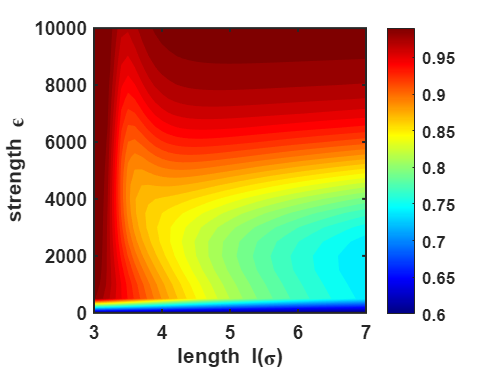

[C,h]=contourf(L,K,Z,50,'--','ShowText','off','LabelSpacing',1000);
h.LevelList=round(h.LevelList,2);  %等高线数值保留小数点后两位
set(h, 'edgecolor','none');
clabel(C,h);

colorbar;
colormap("jet");

set(gca,'linewidth',1,'FontWeight','bold','FontName','arial');
xlabel('length l(\sigma)','FontName','arial','FontWeight','bold'); 
ylabel('strength \epsilon','FontName','arial','FontWeight','bold');

function a= E(r) %定义特定的势能函数E(r)
    e=5000;
    o=1;%计算的其实是o/r
    a=4.*e.*(((r/o).^(-12))-((r/o).^(-6)));
end

function b=P(r) %定义相应的概率分布函数P(r)
    b=exp(-E(r)/(8.31*298));
end